# ACC Data Visualization

This script is used to plot histogram, grid, clustering for abstract and concrete model

clear;
close all;
bdclose('all');

## Load results

Load abstract model from the MAT files

file_name = "ACC_abstract_model.mat";
abModel = load(file_name).abs_model;

% load abstract model parameters
abMdpSpace = abModel.abMdpSpace;
abRewardSpace = abModel.abRewardSpace;
abTranSpace = abModel.abTranSpace;
actionPar = abModel.actionPar;
rewardPar = abModel.rewardPar;
uniquePair = abModel.actionRewardPair;
numController = abModel.numController;
numAbState = length(abRewardSpace);
controllerName = abModel.controllerName;
rewardSpace = abModel.concreteReward;
abReward = abModel.abReward;

abState = abMdpSpace(:,6);      % abstract state w.r.t. concrete states
sampleOfEach = length(abState)/numController;   % number of samples of each controller

controllerName = ["MPC-100-0","MPC-100-1","MPC-50-0","MPC-50-1","DDPG","PPO","A2C","SAC","TD3"];

numConcreteState = length(unique(abMdpSpace(:,1:4),'rows'));
fprintf("Number of distinct concrete states: %i \nNumber of distinct abstract states %i",  numConcreteState, numAbState);

Number of distinct concrete states: 511249 
Number of distinct abstract states 891

numConcreteTran = length(abTranSpace);
numAbTran = max(abTranSpace(:,4));
fprintf("Number of distinct concrete transitions: %i \nNumber of distinct abstract transitions %i",  numConcreteTran, numAbTran);

Number of distinct concrete transitions: 540146 
Number of distinct abstract transitions 15226

## Reward Distribution

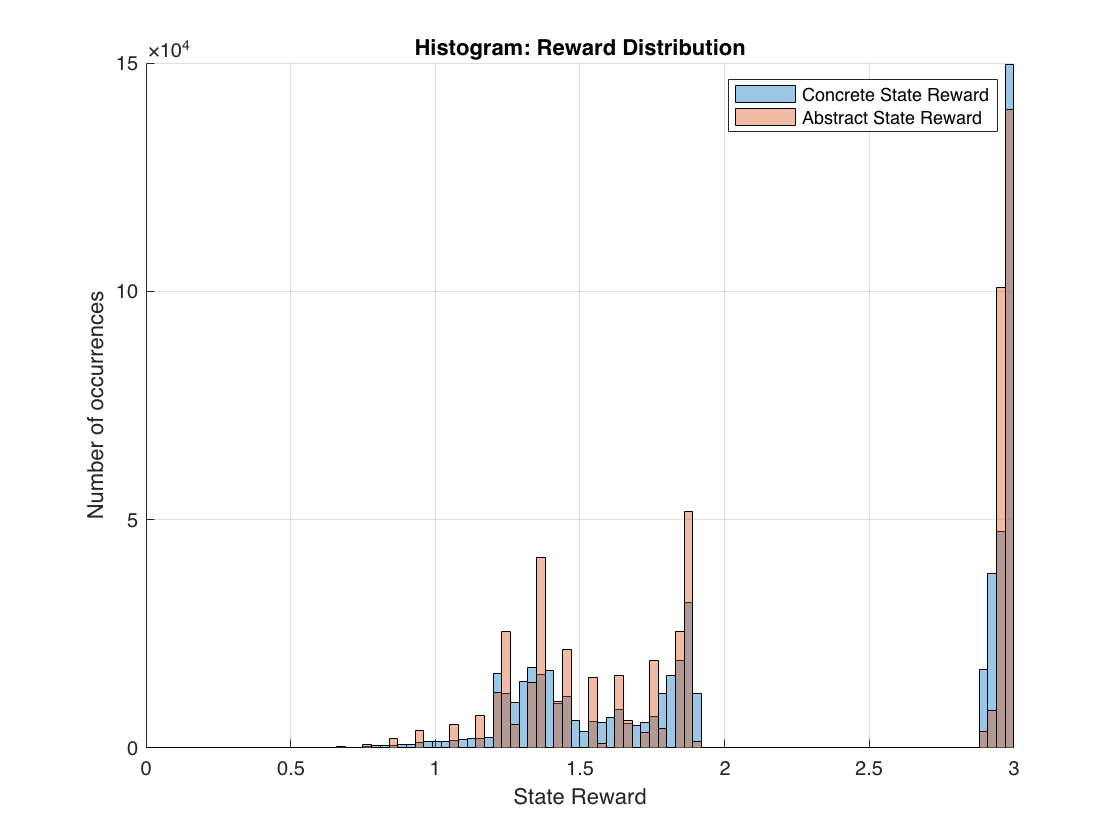

figure;
hold on 
histogram(rewardSpace, 'FaceAlpha',0.4);
histogram(abReward, 'FaceAlpha',0.4);
hold off
grid on;
xlim([0, 3]);
legend("Concrete State Reward", "Abstract State Reward");
title("Histogram: Reward Distribution");
xlabel('State Reward') ;
ylabel('Number of occurrences') ;

## Histogram of abstract states

Histogram to how the number of occurrences of each distinct abstract states

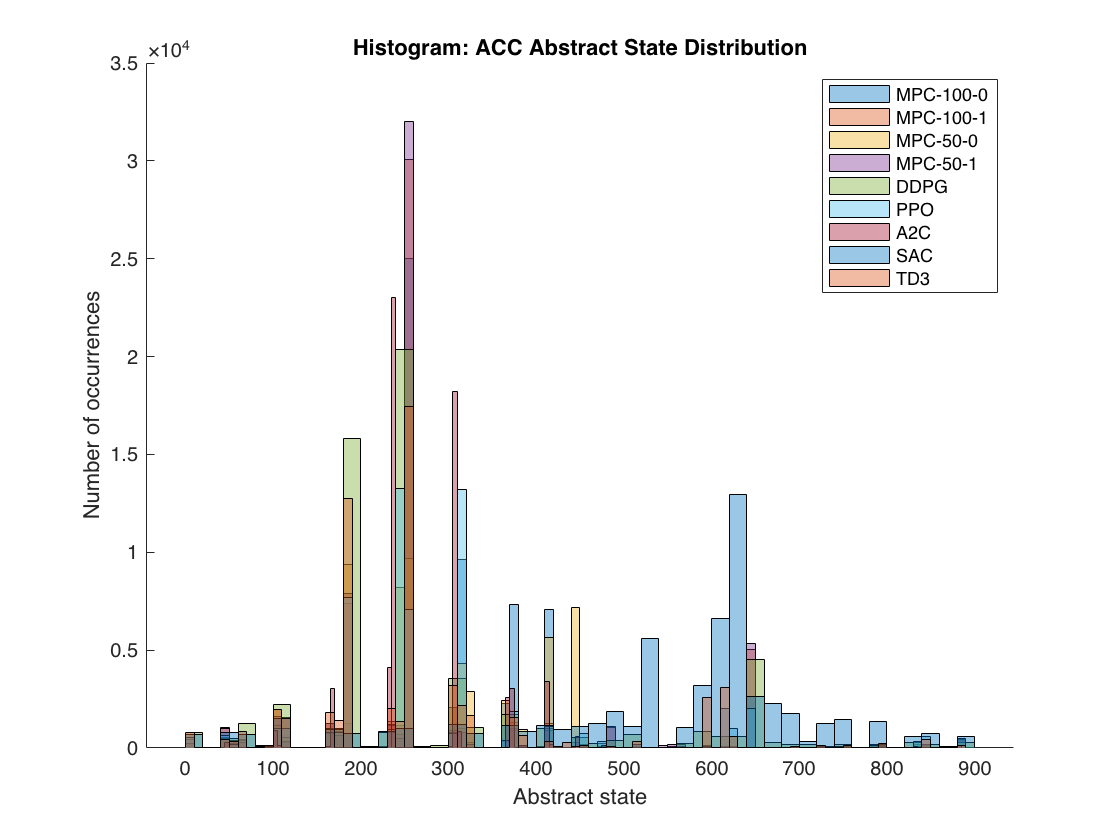

% histogram of abstract states of all controllers
abStateOfEach = cell(numController,1);      % cell array contain abState of each controller

figure;
hold on

for i = 1:numController
    abStateOfEach{i} = abState((i-1)*sampleOfEach+1:i*sampleOfEach);
    histogram(abStateOfEach{i}, 'FaceAlpha',0.4);
end
hold off

legend(controllerName);
title("Histogram: ACC Abstract State Distribution");
xlabel('Abstract state') 
ylabel('Number of occurrences') 

## Abstract State Coverage

abStateCov = zeros(numController,1);      % cell array contain basic state coverage of each controller

for i = 1:numController
    abStateCov(i) = length(unique(abStateOfEach{i}))/numAbState;
    fprintf("BSCov of %s: %.2f \n",controllerName(i), abStateCov(i));
end

BSCov of MPC-100-0: 0.15 
BSCov of MPC-100-1: 0.43 
BSCov of MPC-50-0: 0.28 
BSCov of MPC-50-1: 0.60 
BSCov of DDPG: 0.73 
BSCov of PPO: 0.24 
BSCov of SA2C: 0.12 
BSCov of SAC: 0.32 
BSCov of TD3: 0.21 


## Kolmogorov-Smirnov (KS) test for Abstract State Distribution

Do KS test on abstract state distribution betwwen each two controllers 

H0: two samples are from the same continuous distribution

H1: two samples are from  different continuous distributions

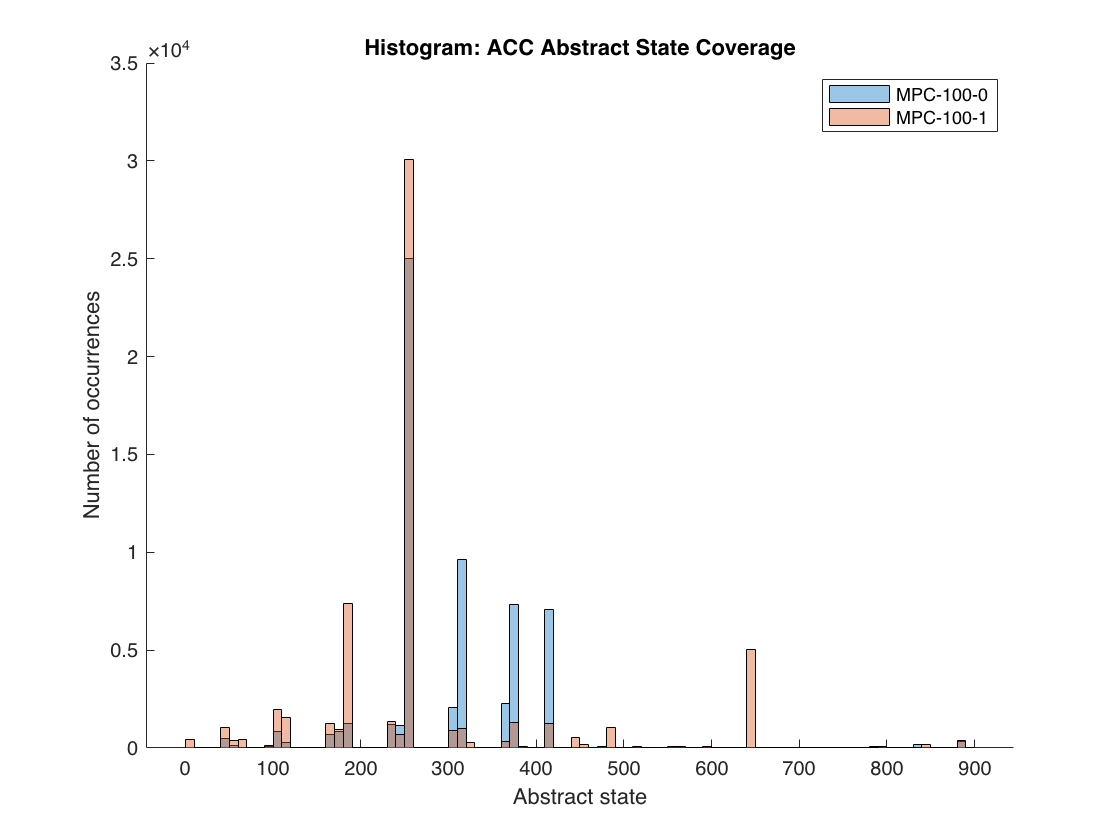

KS test: MPC-100-0 and MPC-100-1: H1 


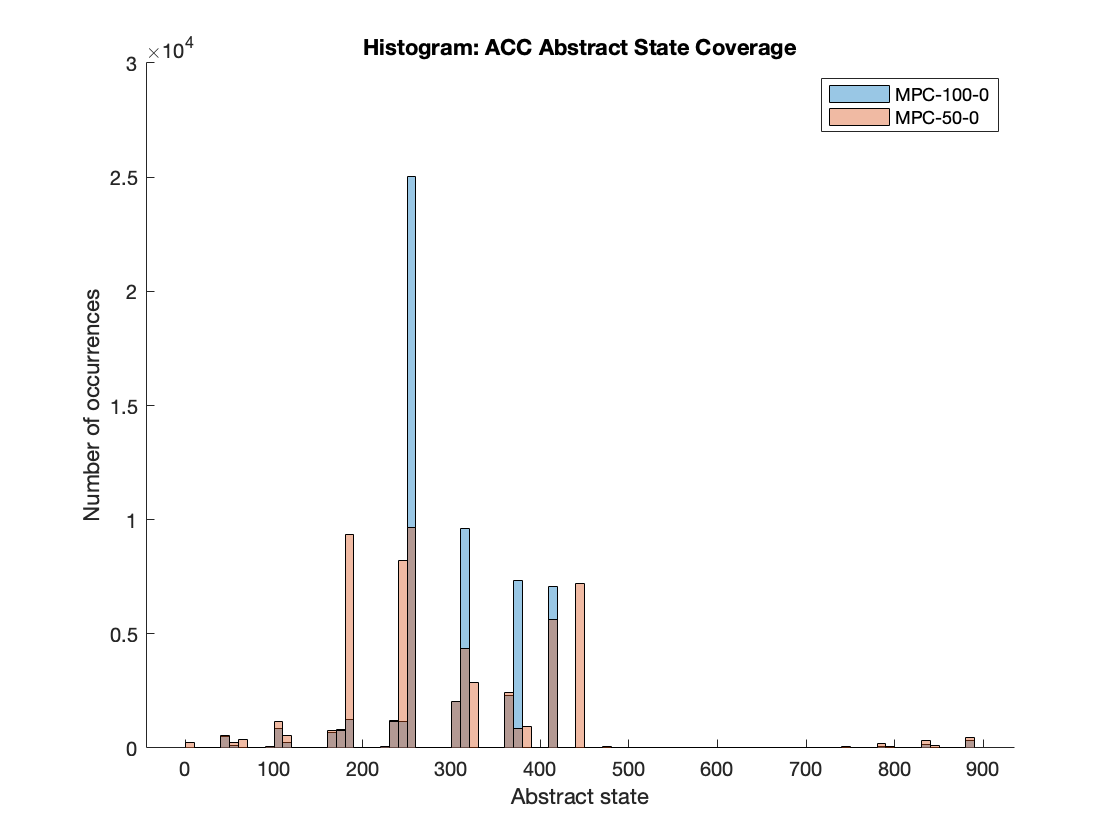

KS test: MPC-100-0 and MPC-50-0: H1 


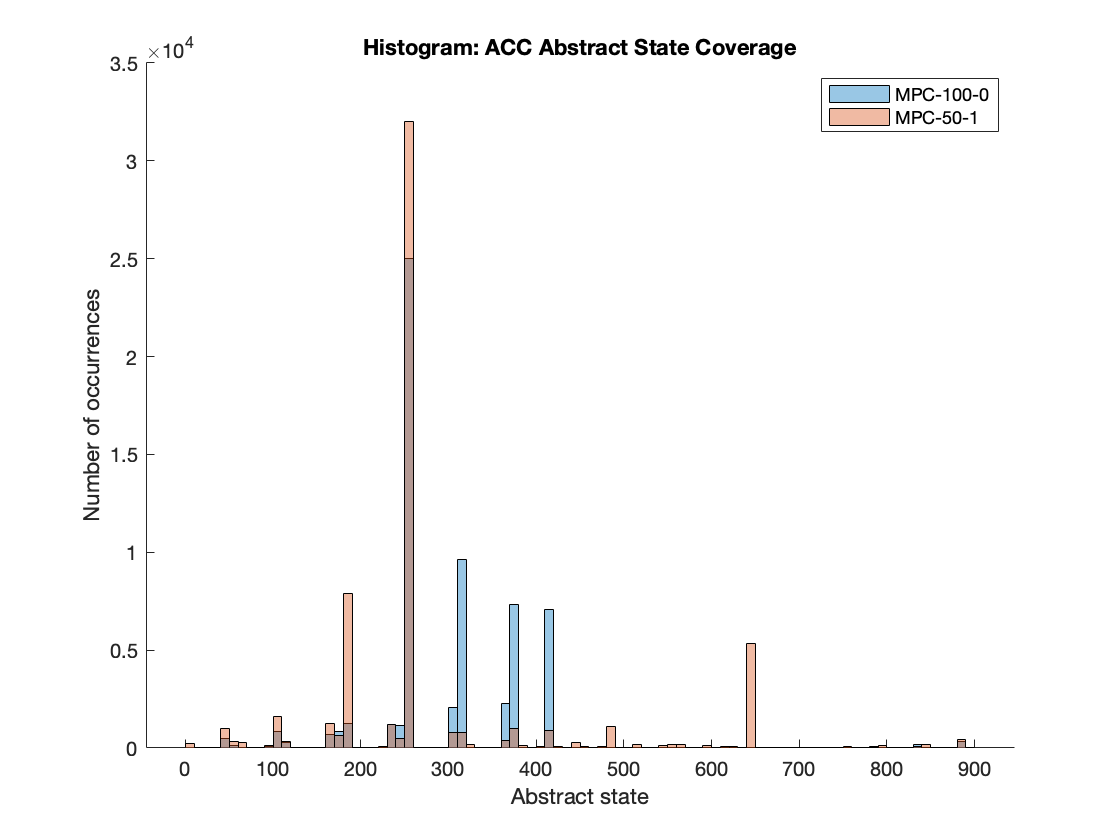

KS test: MPC-100-0 and MPC-50-1: H1 


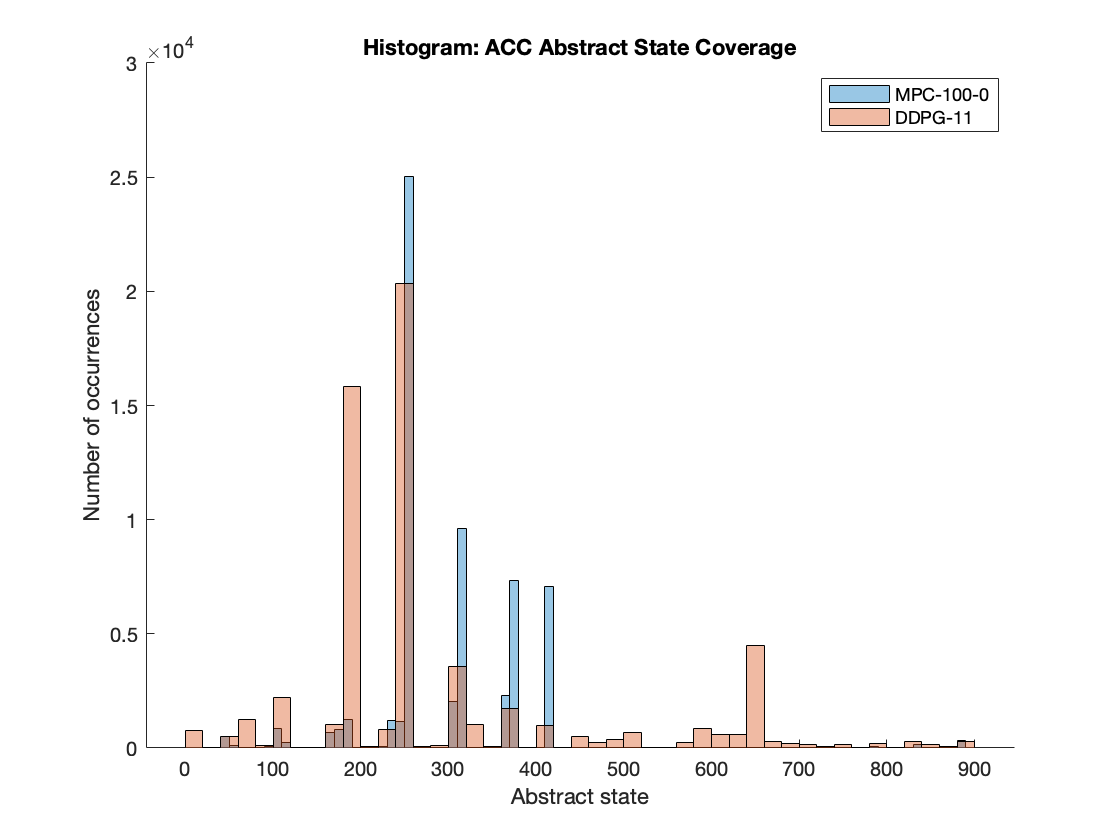

KS test: MPC-100-0 and DDPG-11: H1 


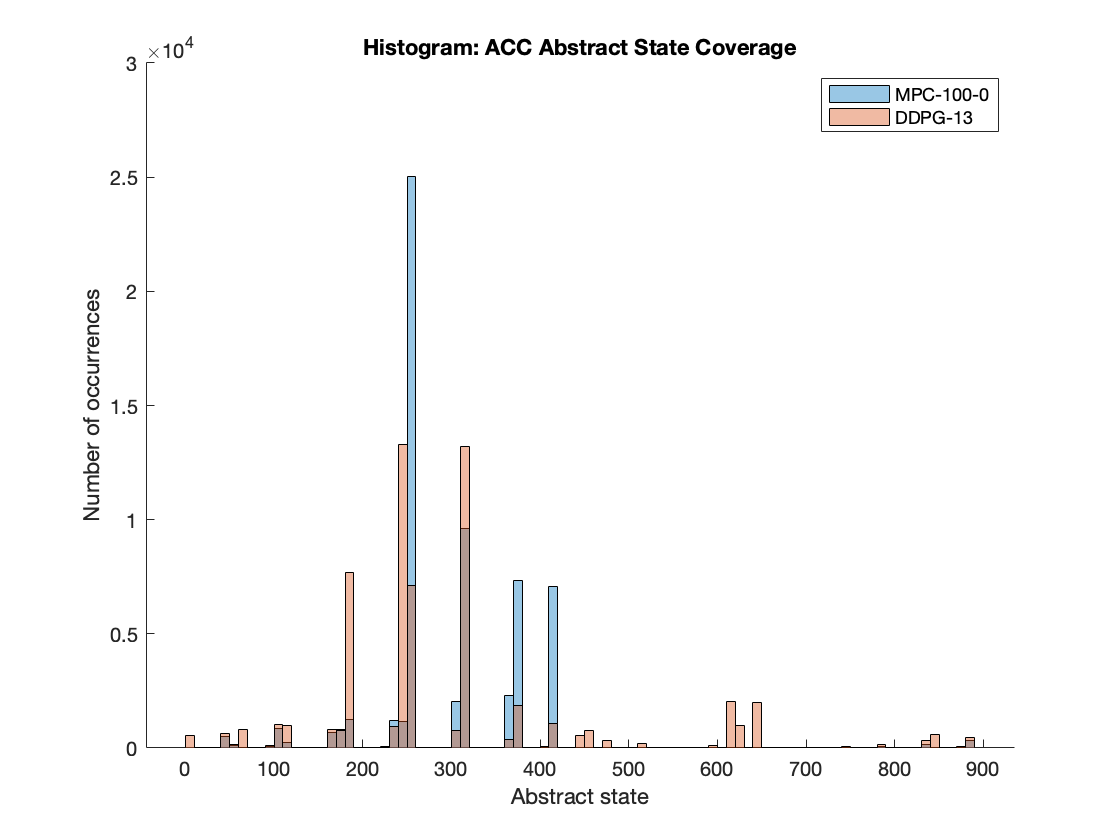

KS test: MPC-100-0 and DDPG-13: H1 


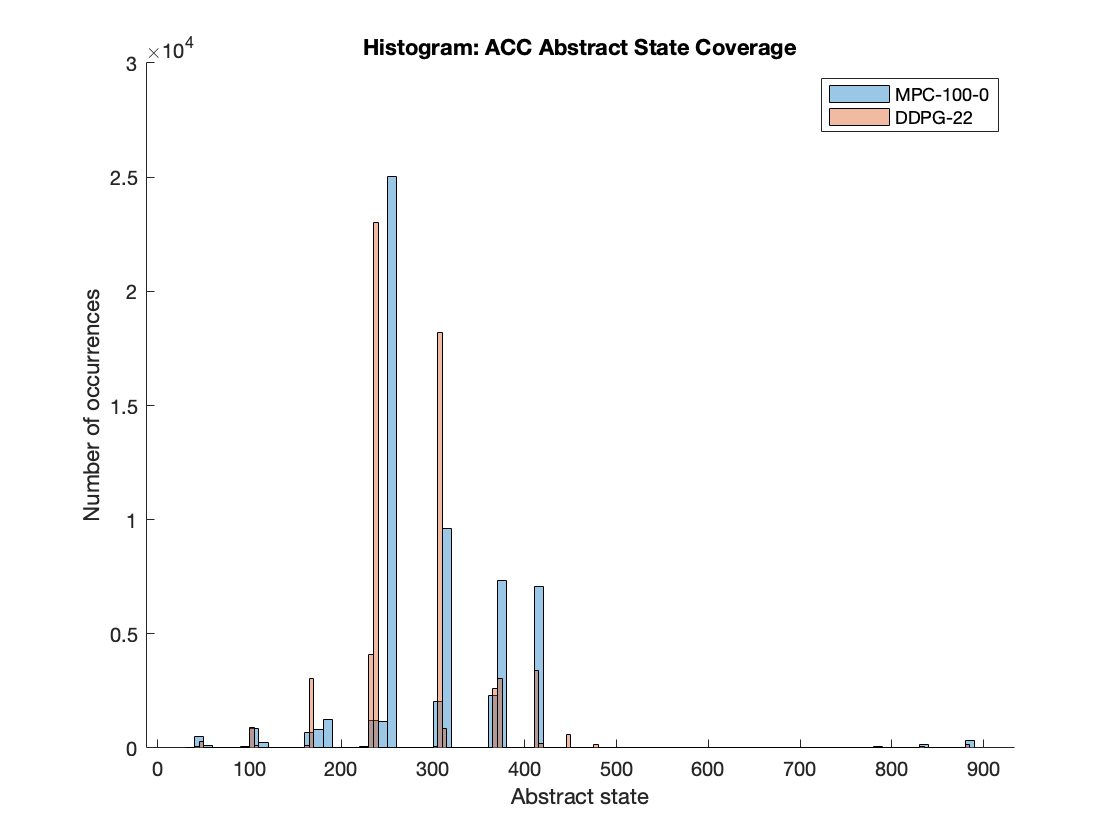

KS test: MPC-100-0 and DDPG-22: H1 


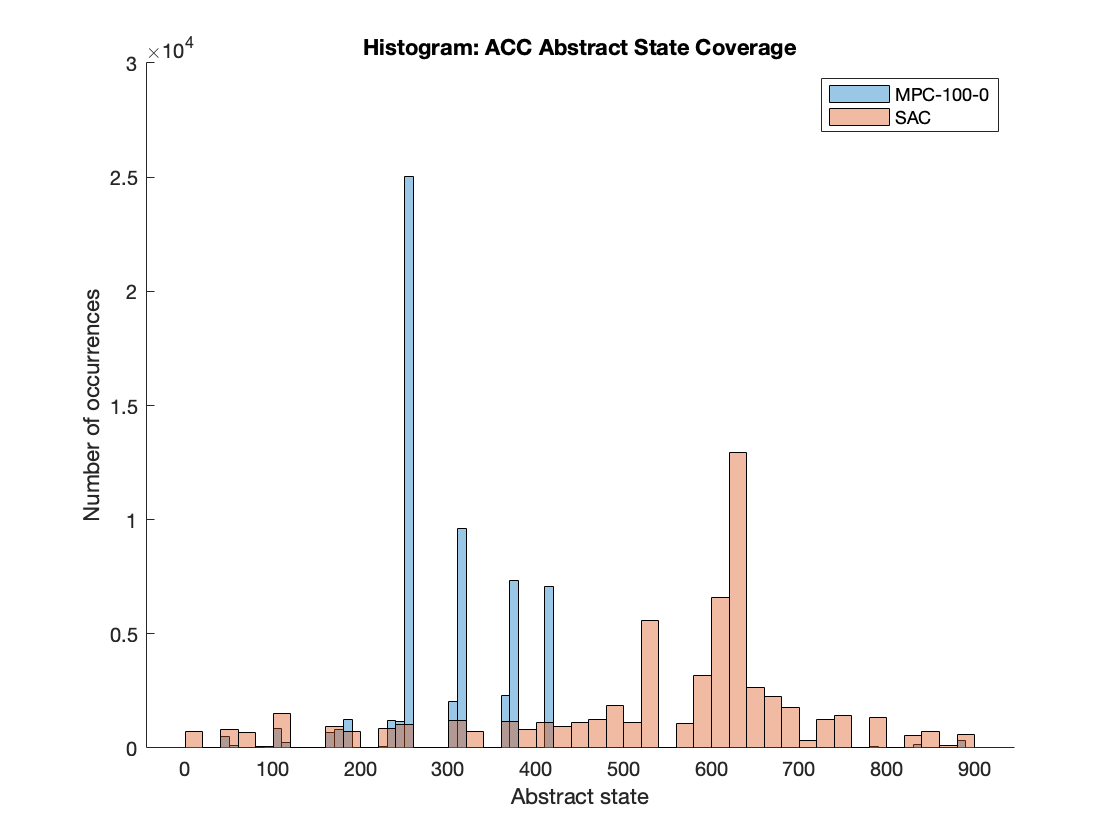

KS test: MPC-100-0 and SAC: H1 


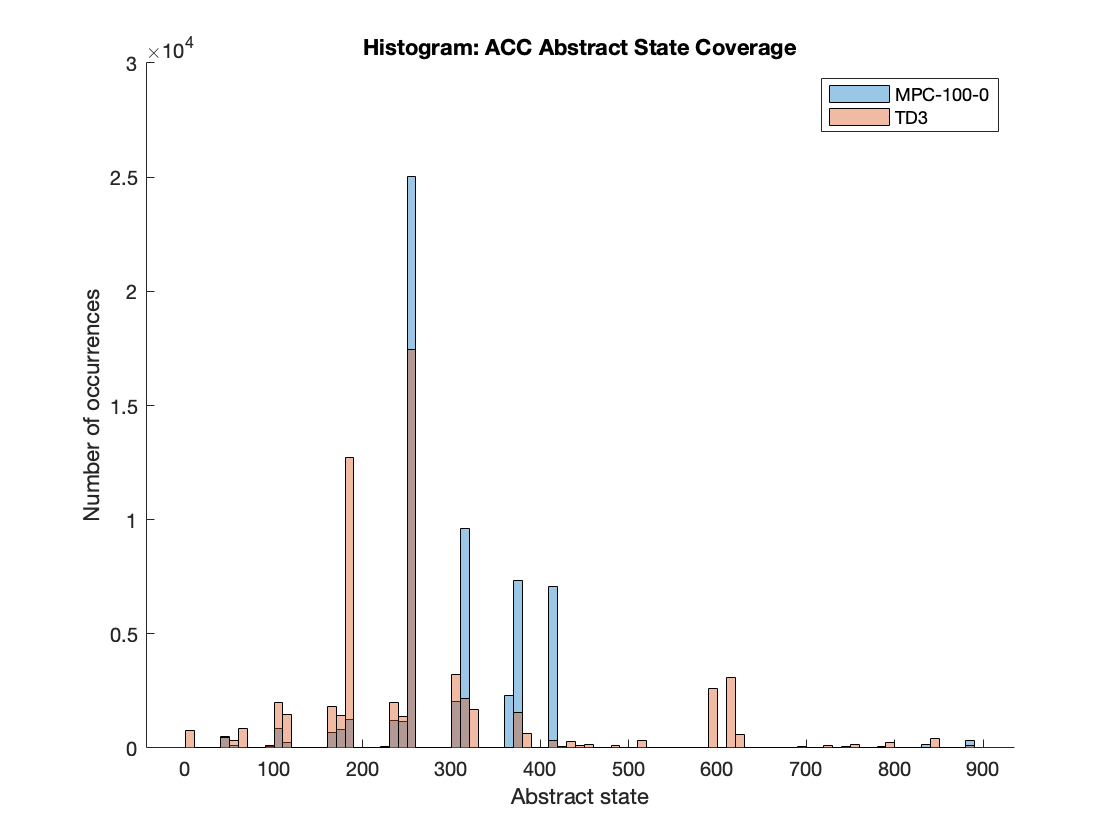

KS test: MPC-100-0 and TD3: H1 


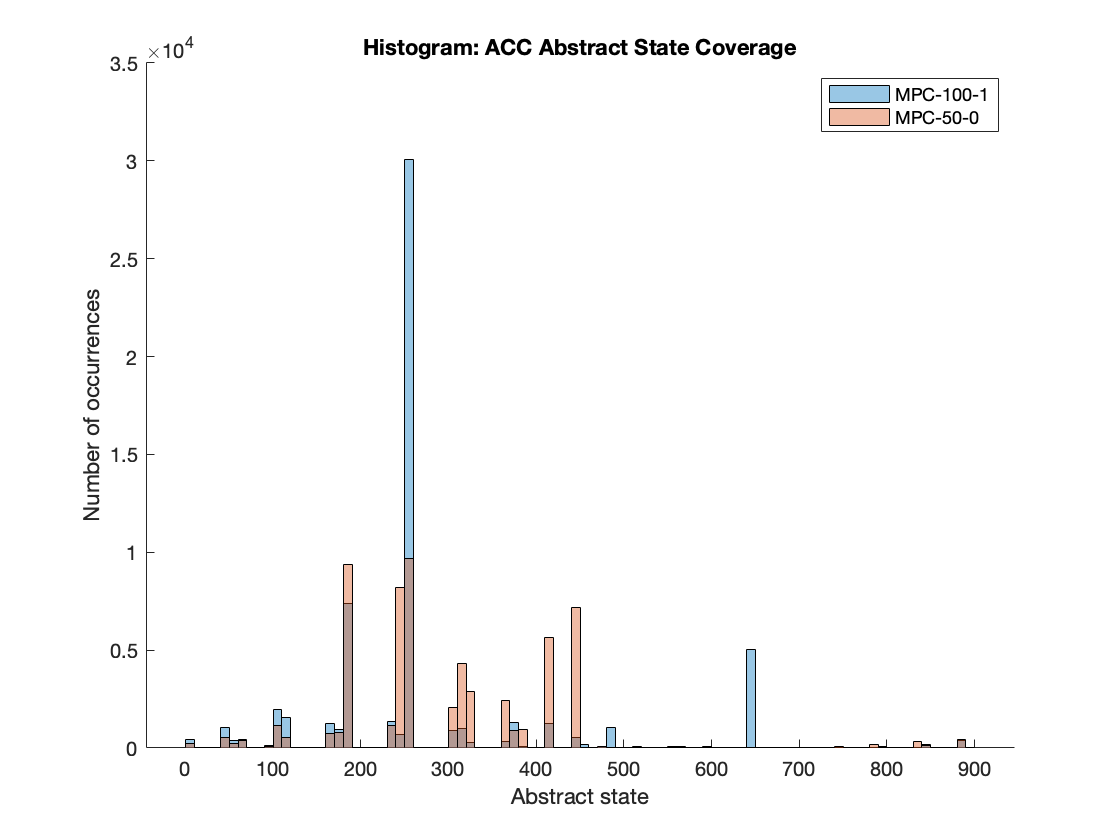

KS test: MPC-100-1 and MPC-50-0: H1 


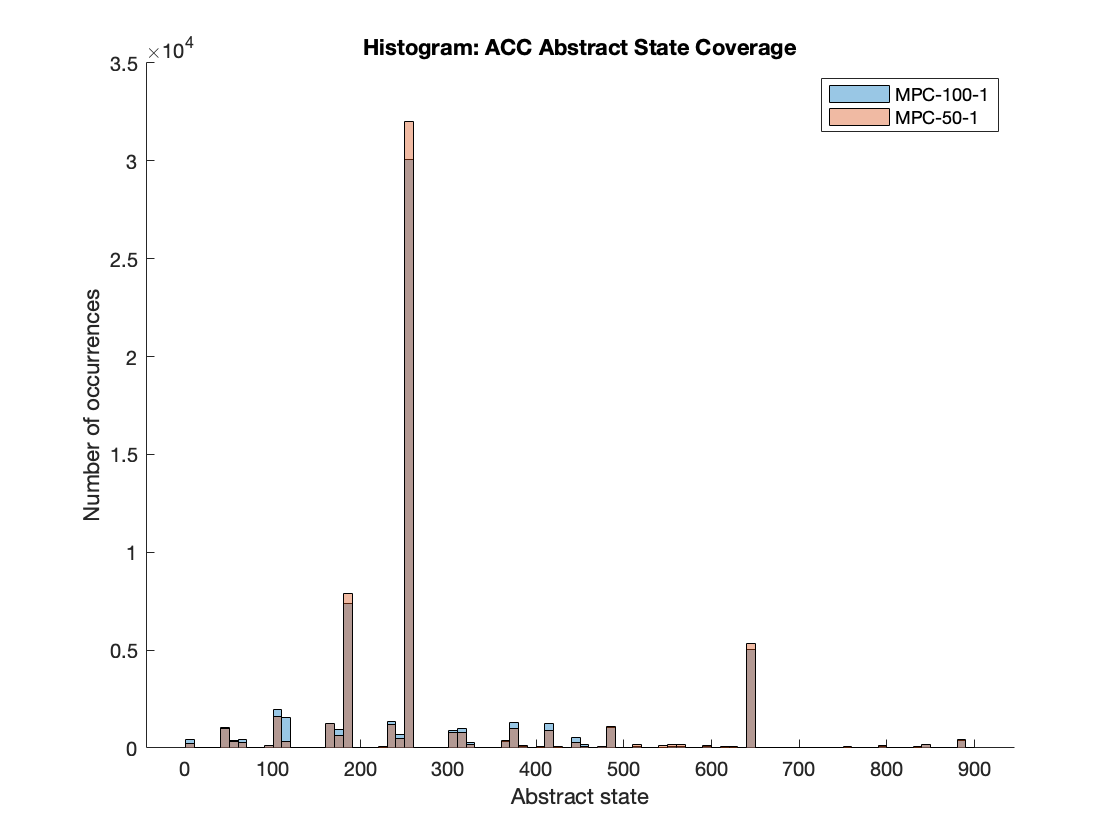

KS test: MPC-100-1 and MPC-50-1: H1 


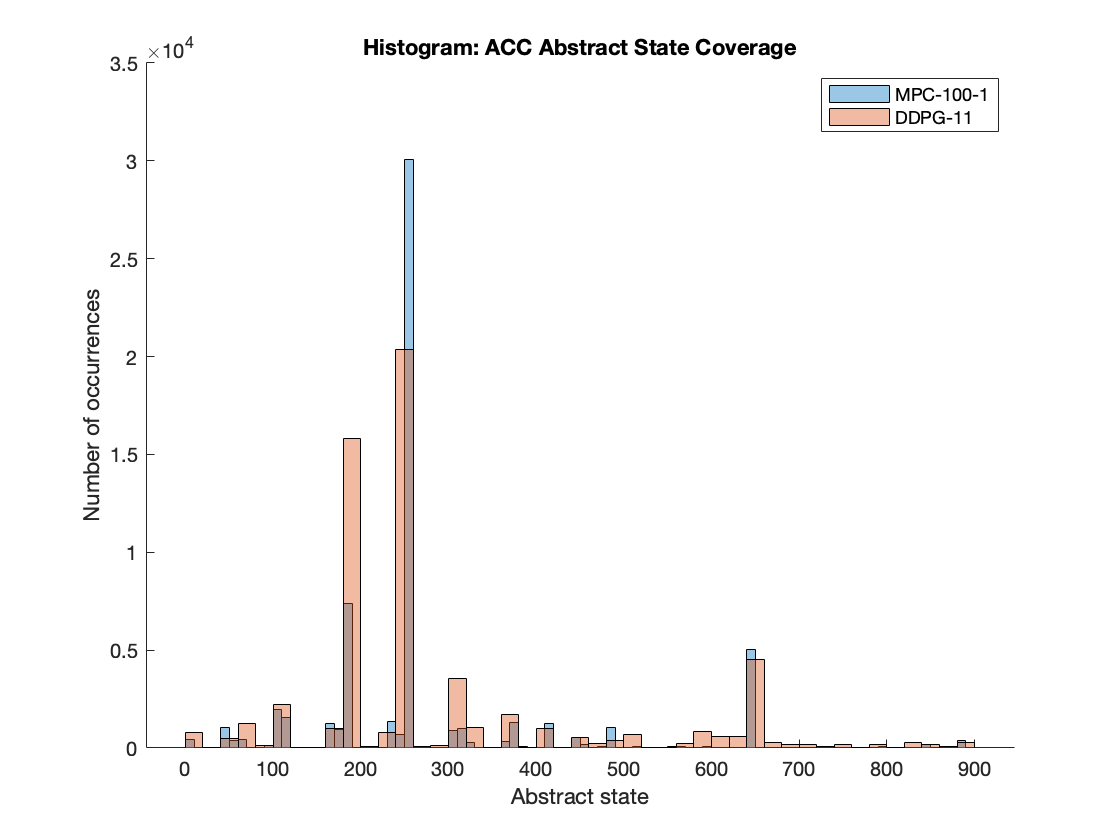

KS test: MPC-100-1 and DDPG-11: H1 


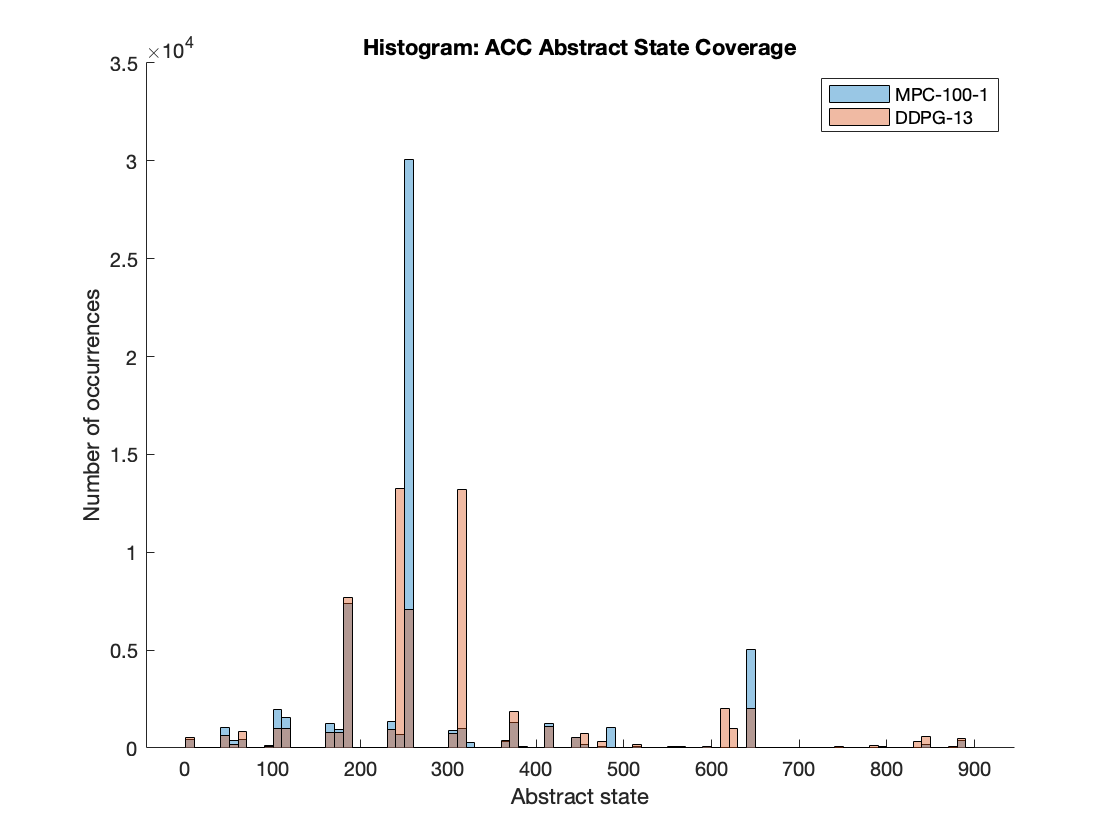

KS test: MPC-100-1 and DDPG-13: H1 


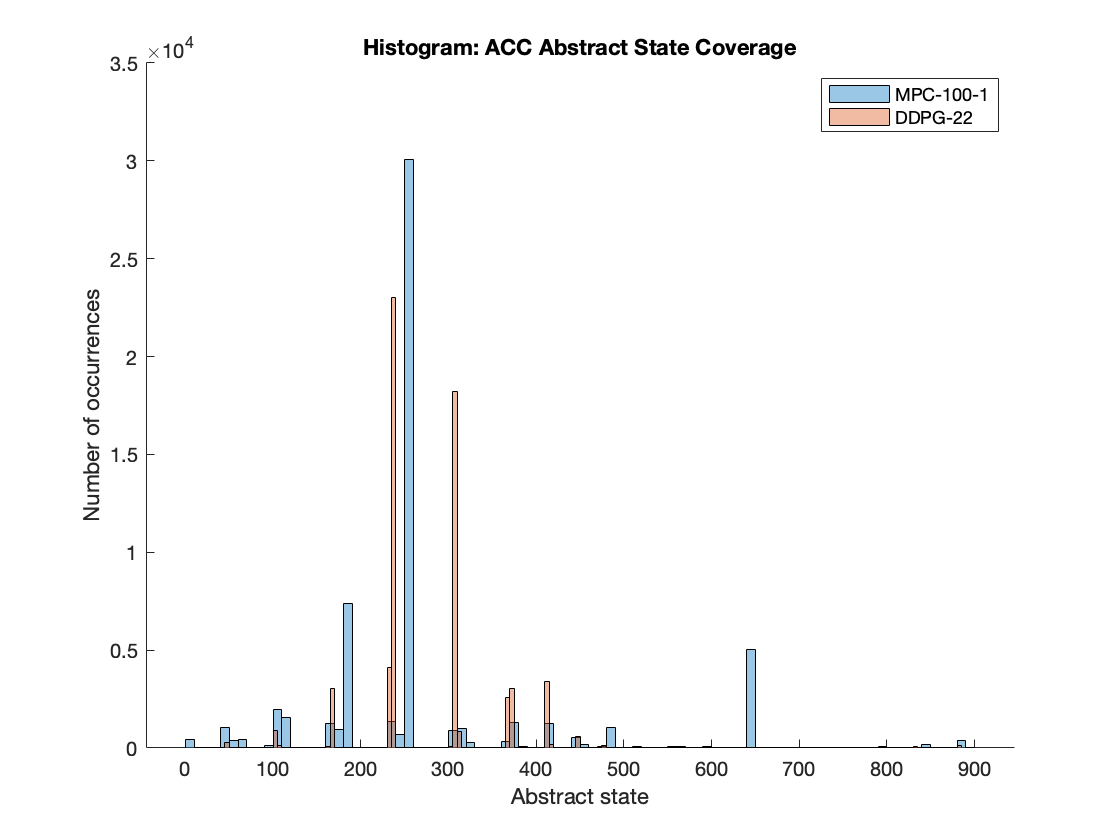

KS test: MPC-100-1 and DDPG-22: H1 


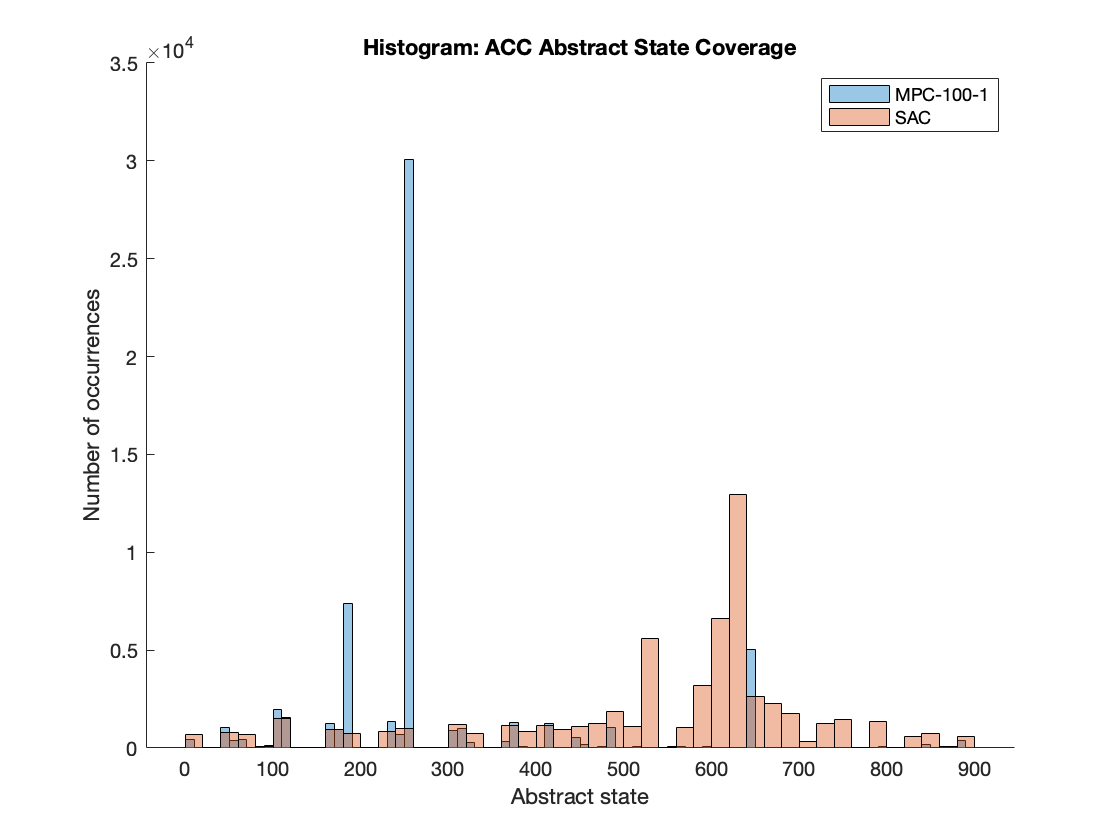

KS test: MPC-100-1 and SAC: H1 


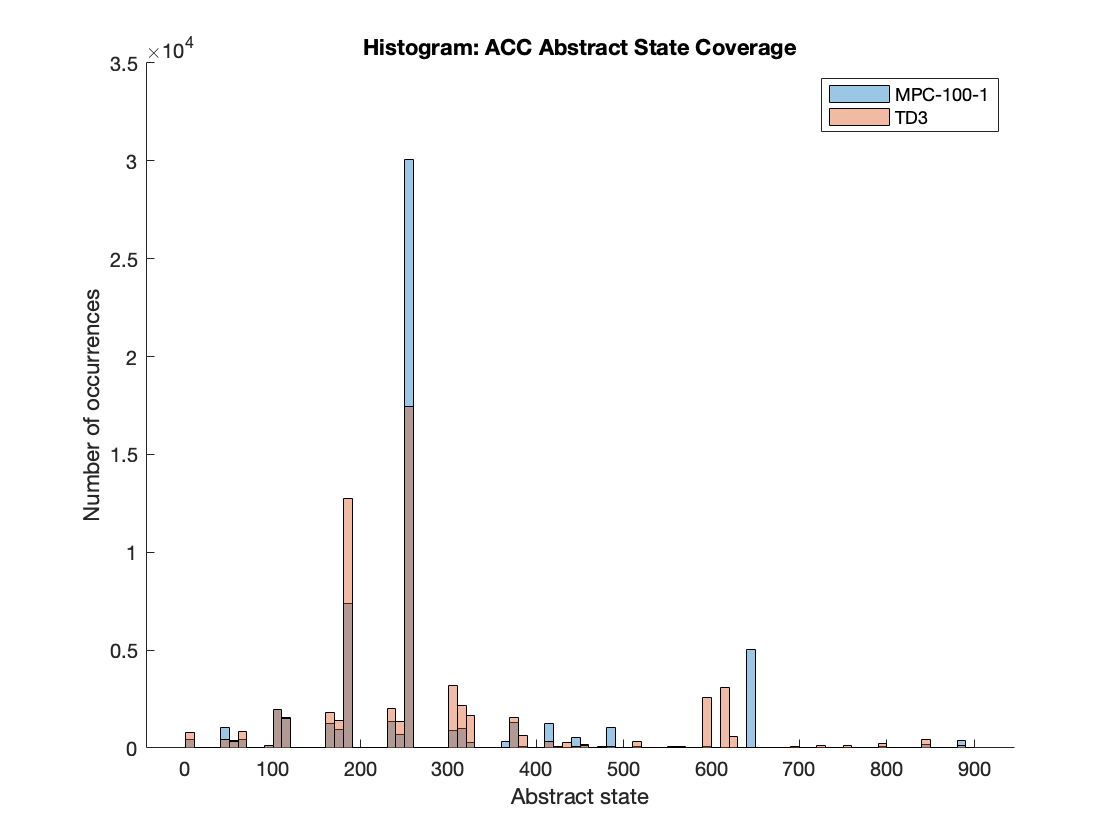

KS test: MPC-100-1 and TD3: H1 


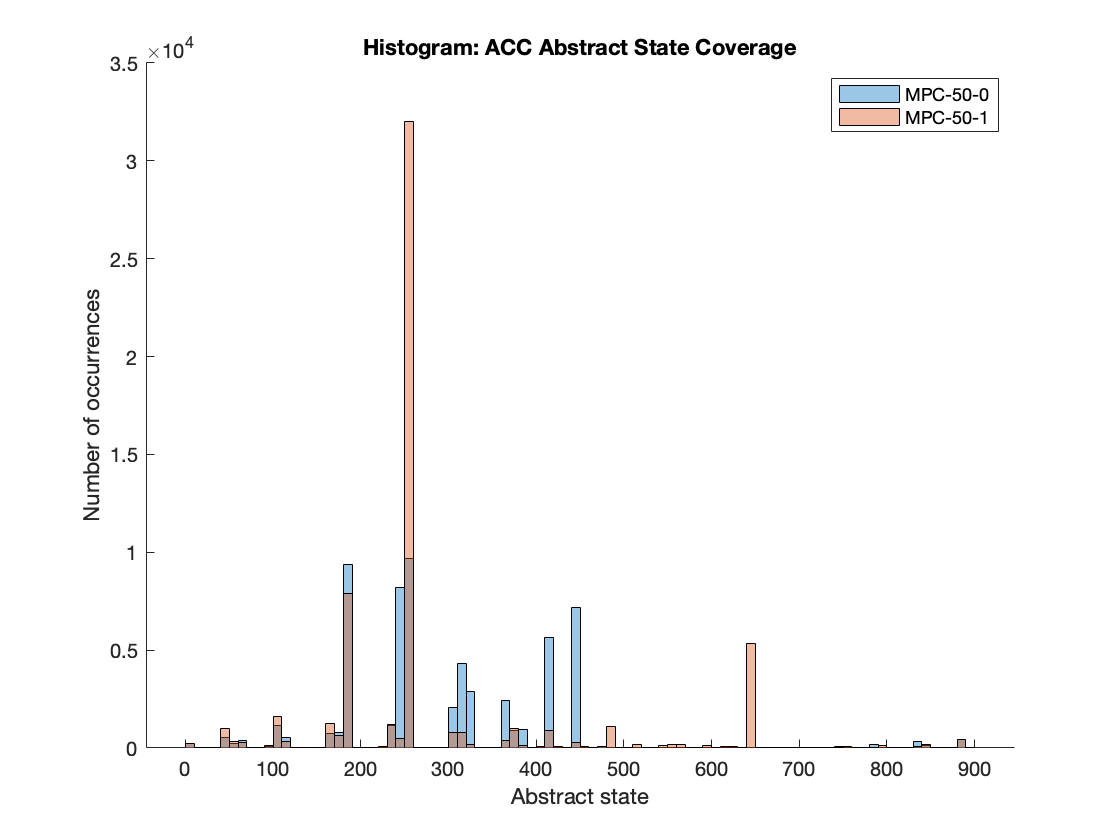

KS test: MPC-50-0 and MPC-50-1: H1 


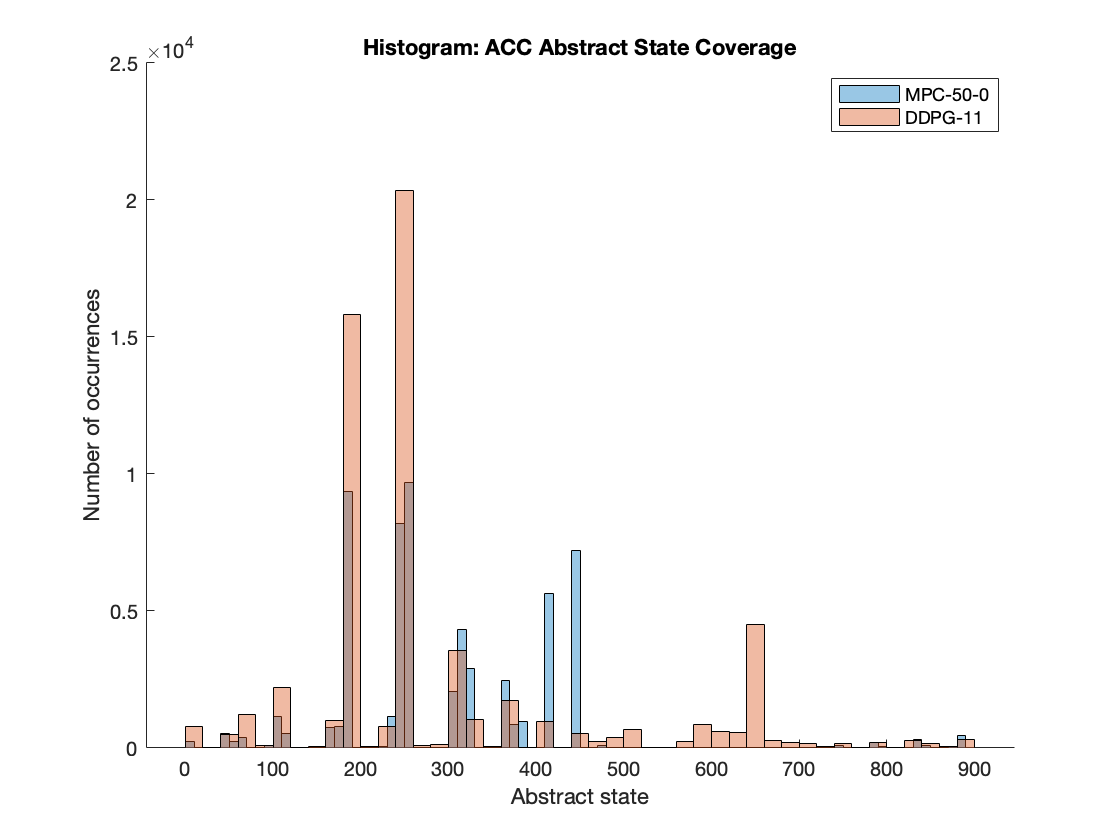

KS test: MPC-50-0 and DDPG-11: H1 


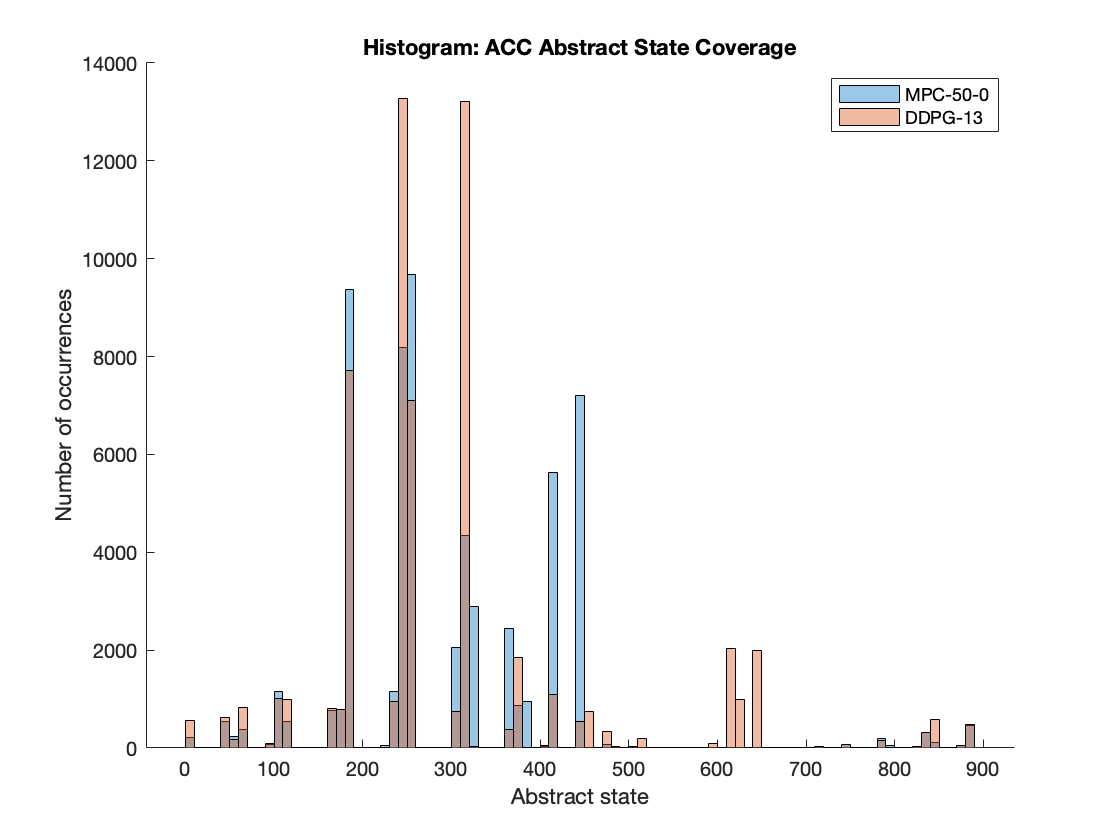

KS test: MPC-50-0 and DDPG-13: H1 


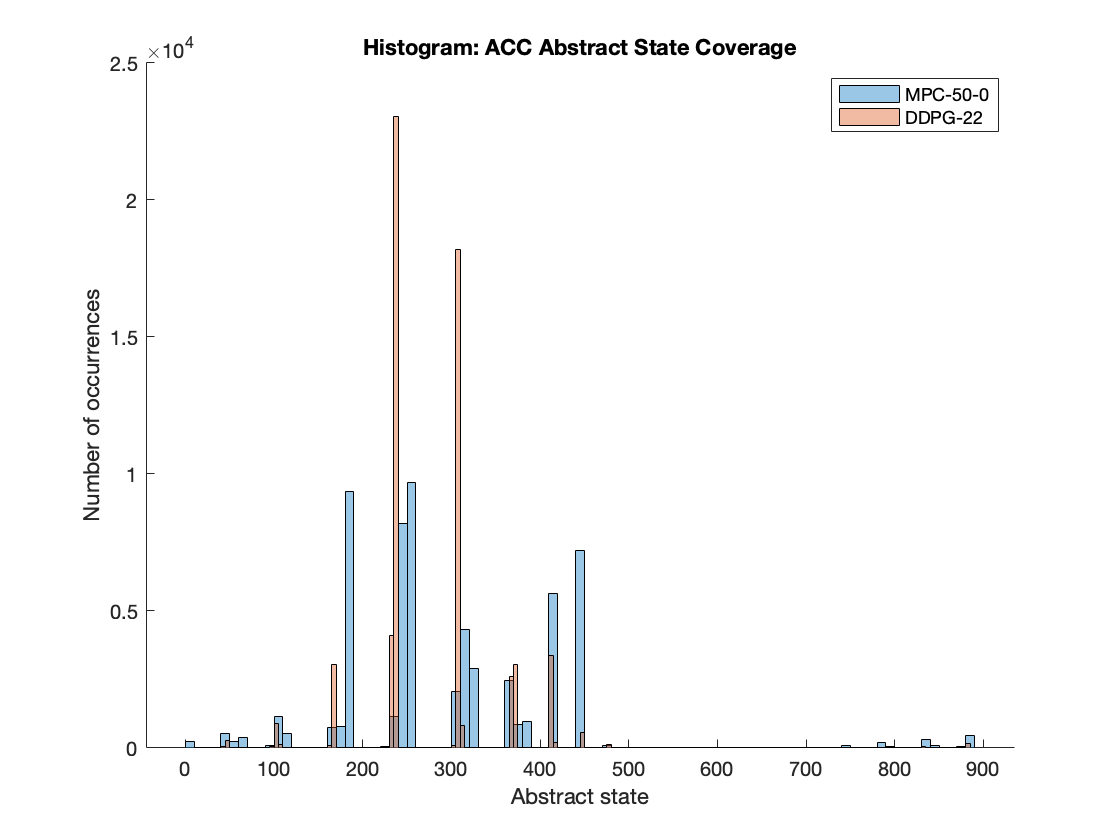

KS test: MPC-50-0 and DDPG-22: H1 


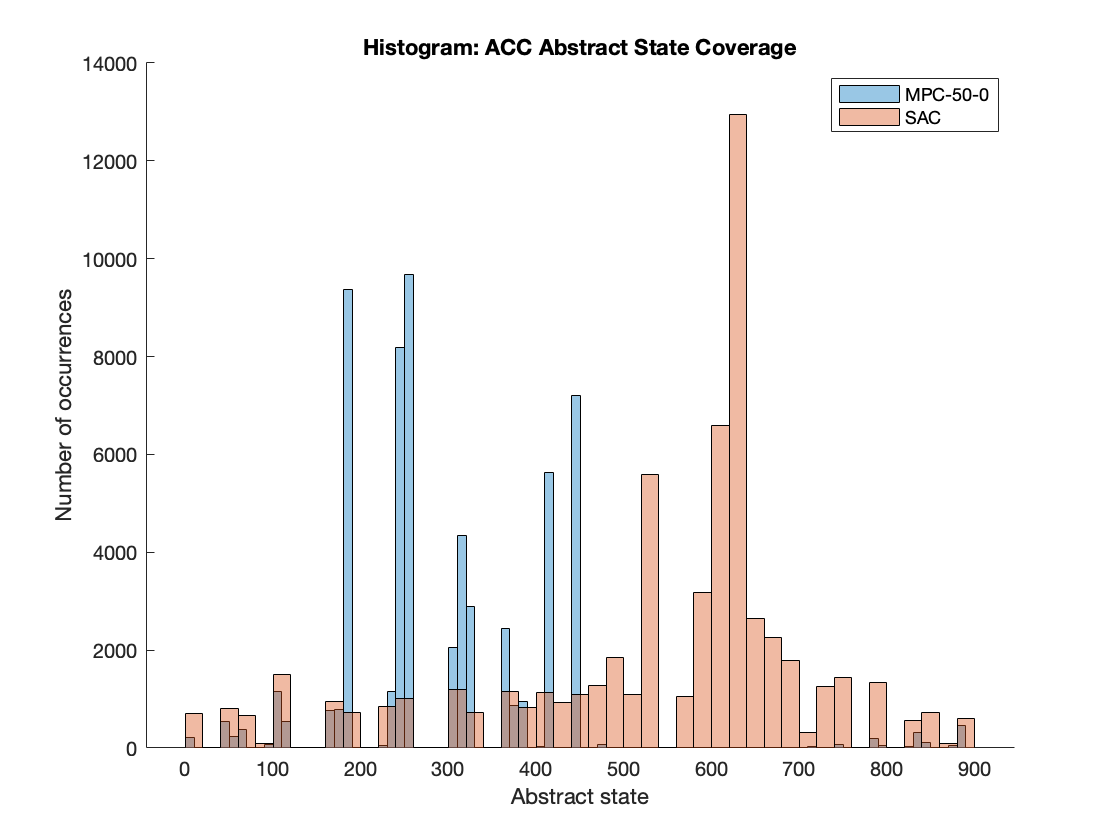

KS test: MPC-50-0 and SAC: H1 


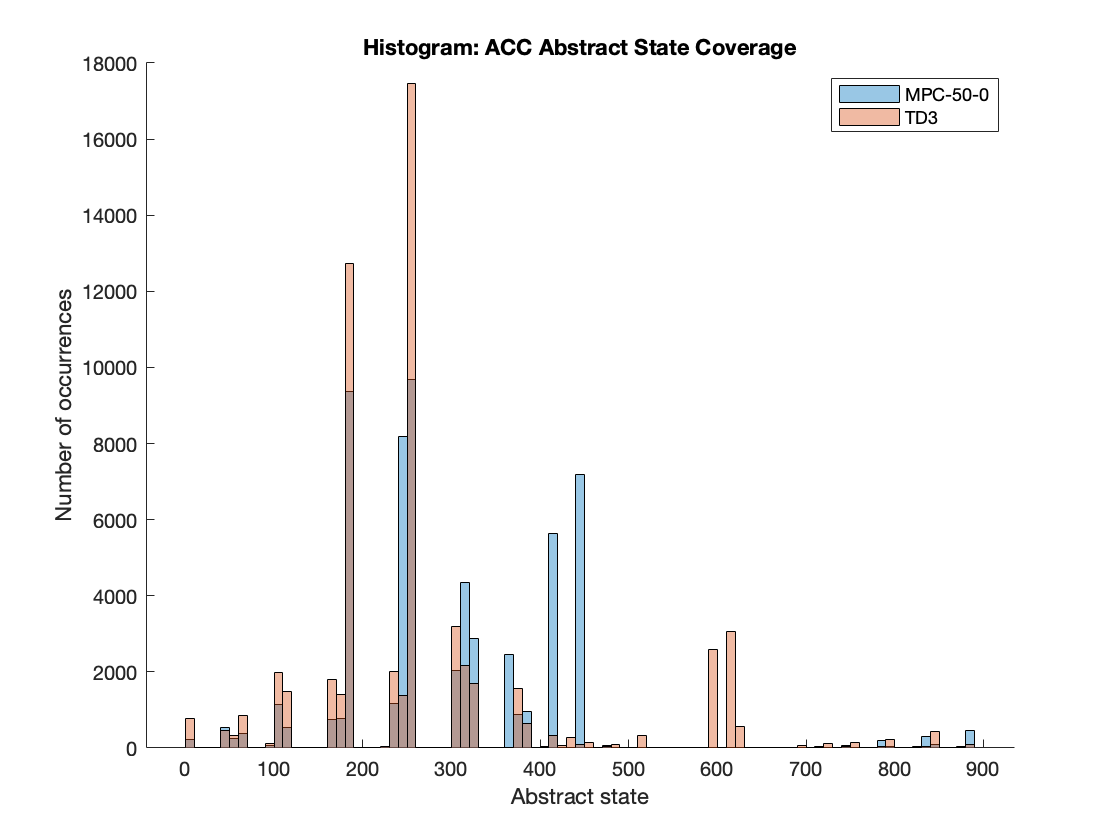

KS test: MPC-50-0 and TD3: H1 


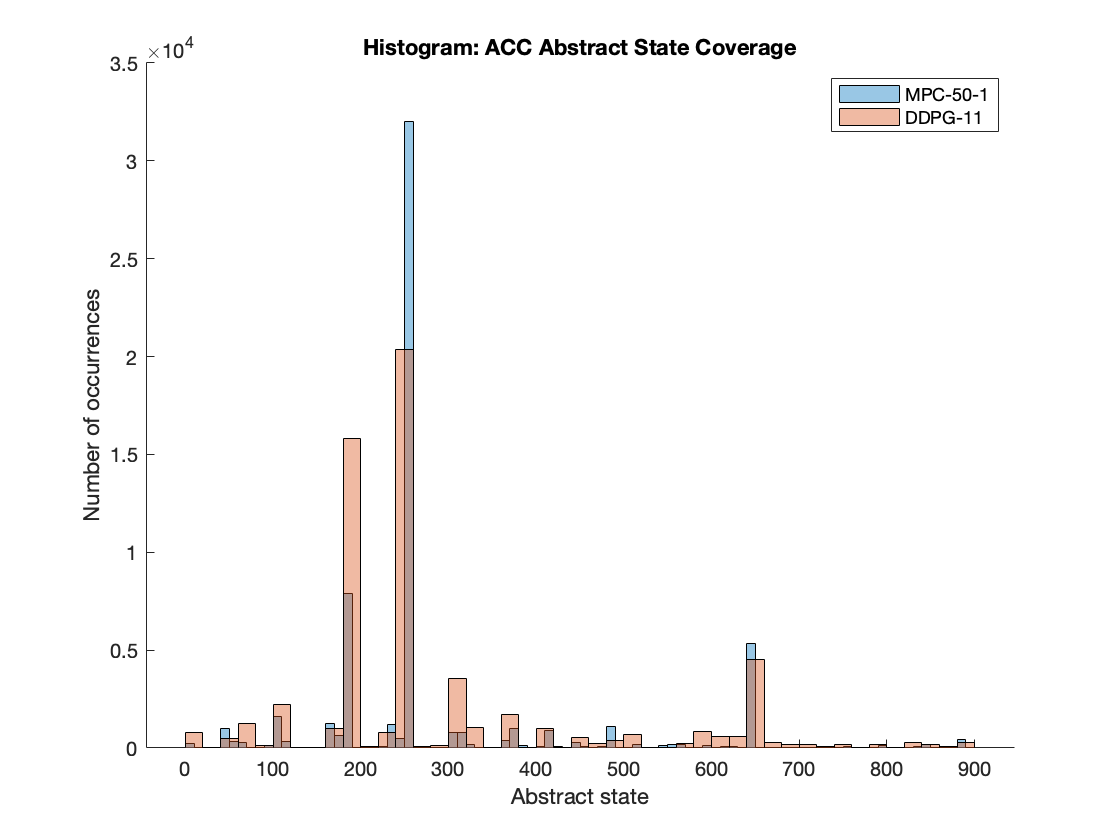

KS test: MPC-50-1 and DDPG-11: H1 


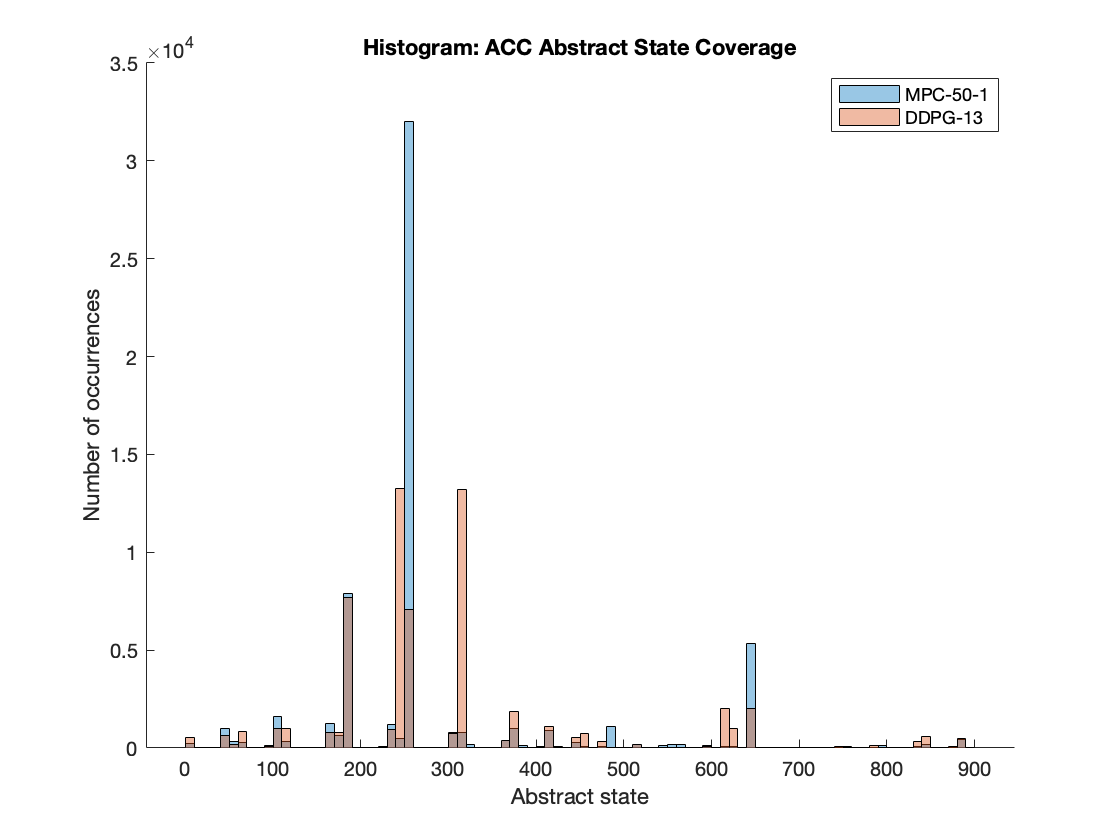

KS test: MPC-50-1 and DDPG-13: H1 


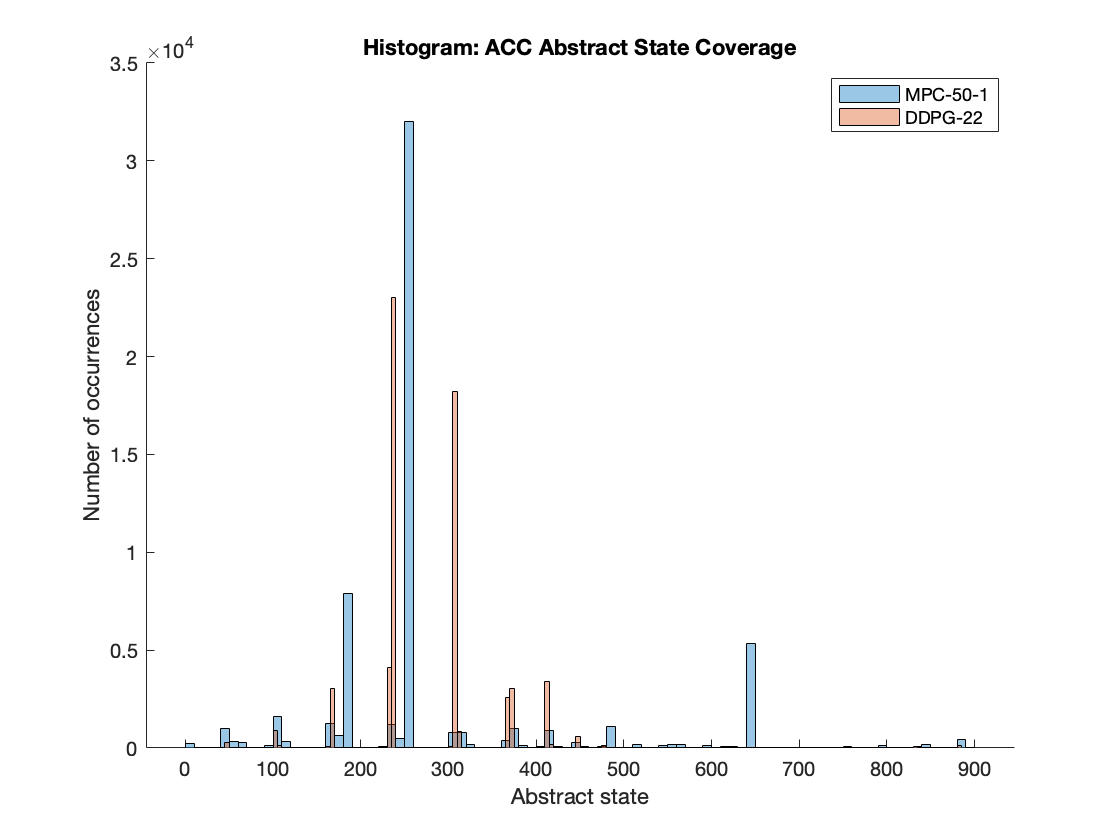

KS test: MPC-50-1 and DDPG-22: H1 


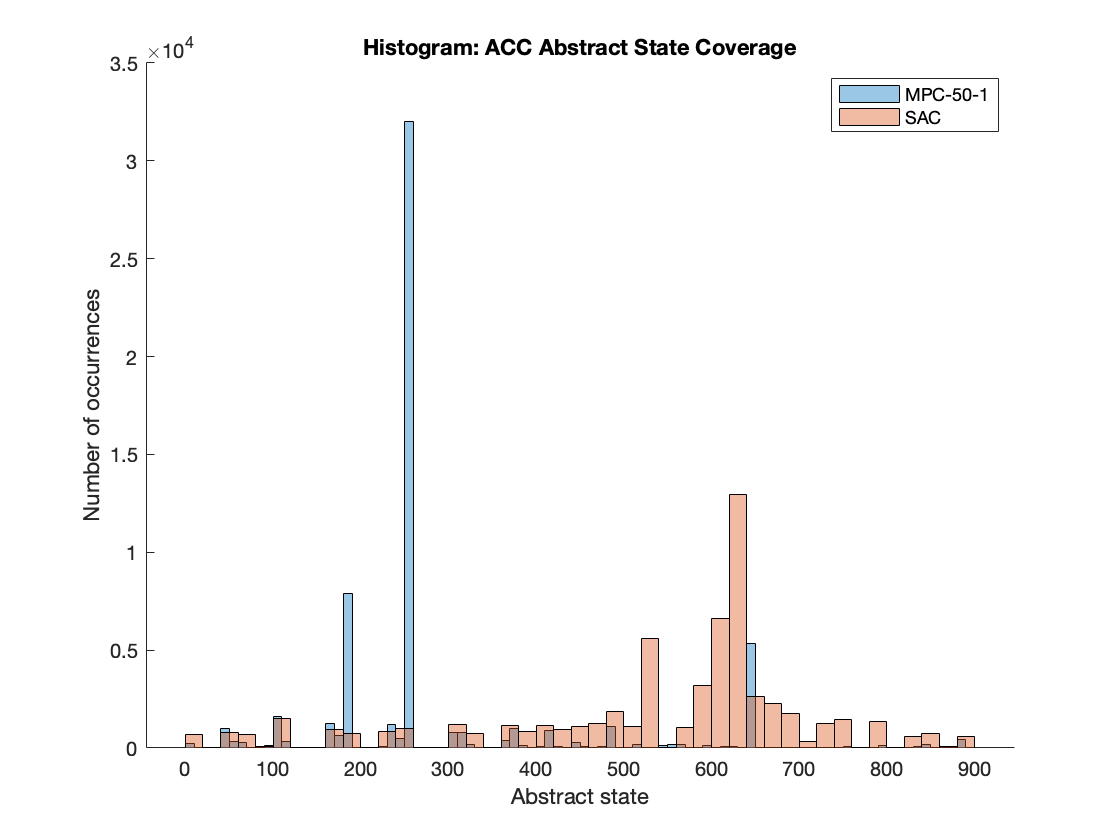

KS test: MPC-50-1 and SAC: H1 


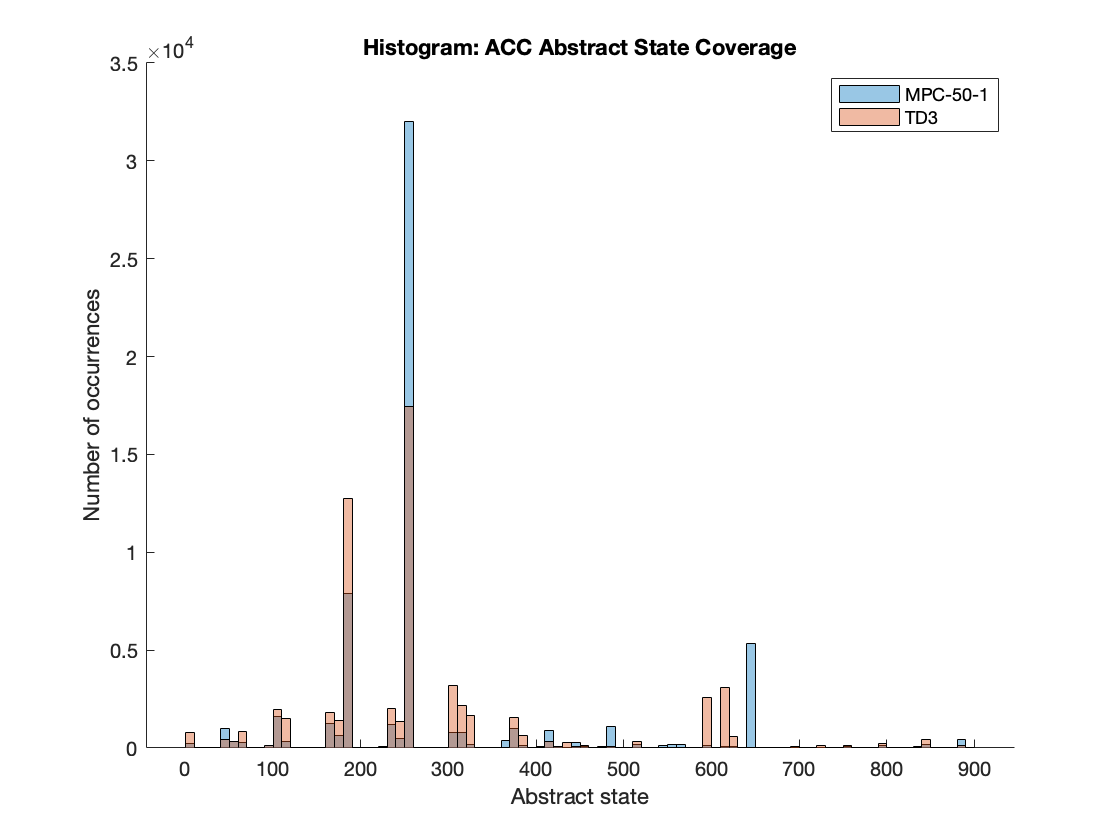

KS test: MPC-50-1 and TD3: H1 


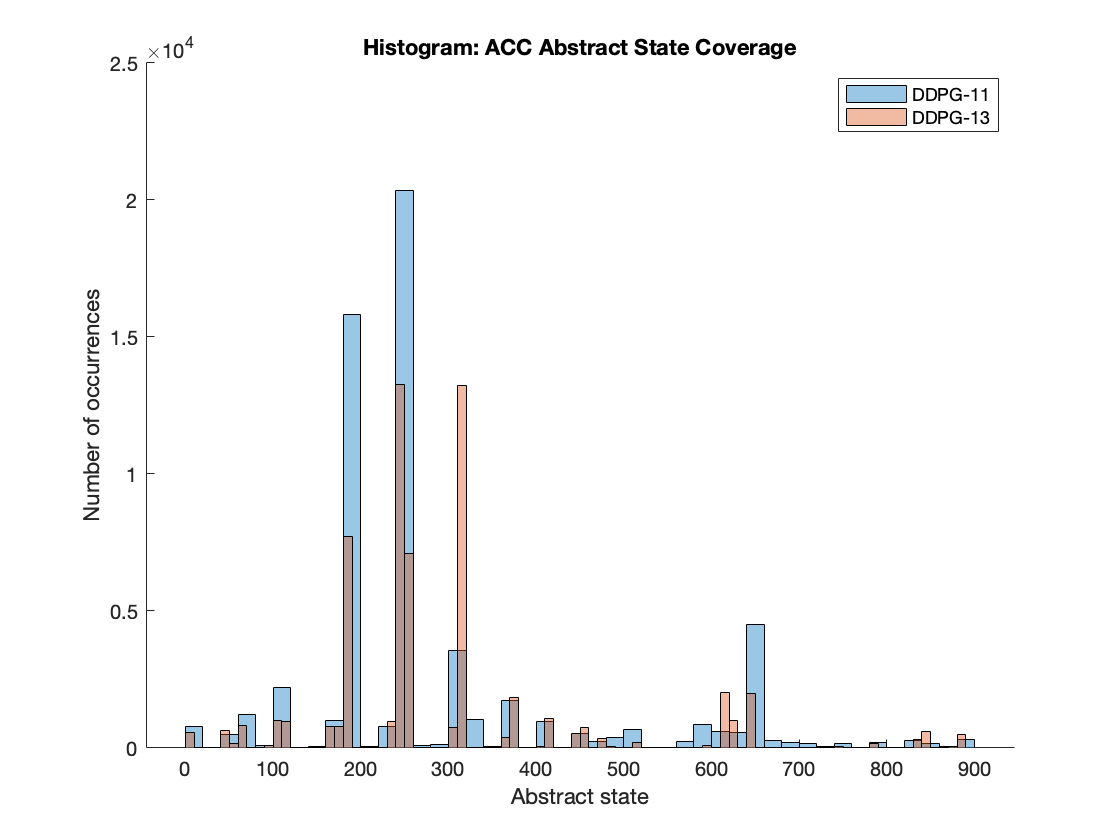

KS test: DDPG-11 and DDPG-13: H1 


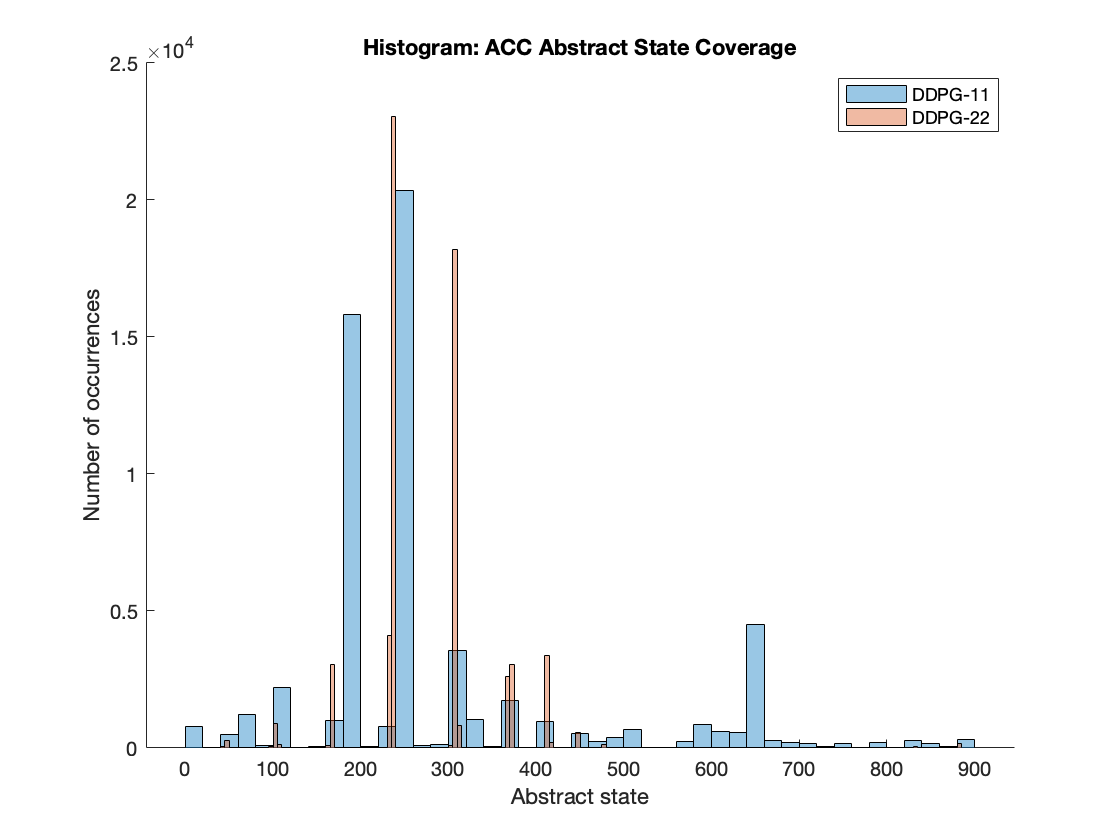

KS test: DDPG-11 and DDPG-22: H1 


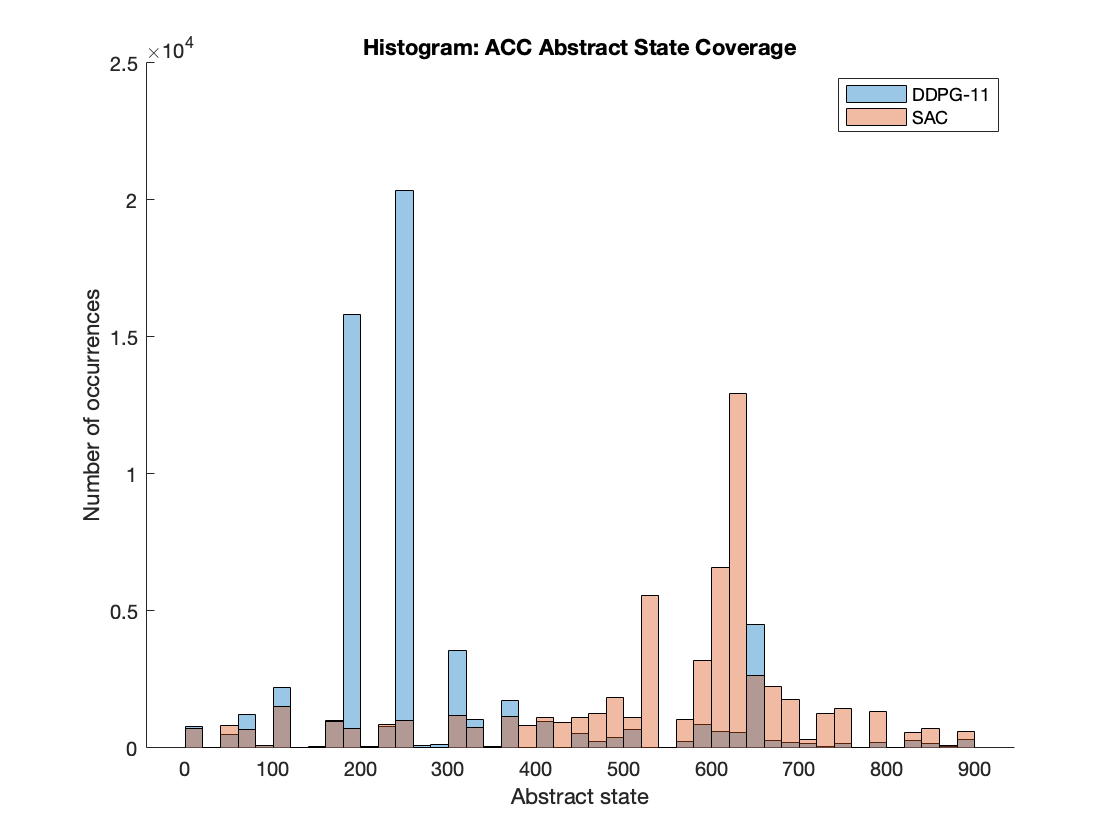

KS test: DDPG-11 and SAC: H1 


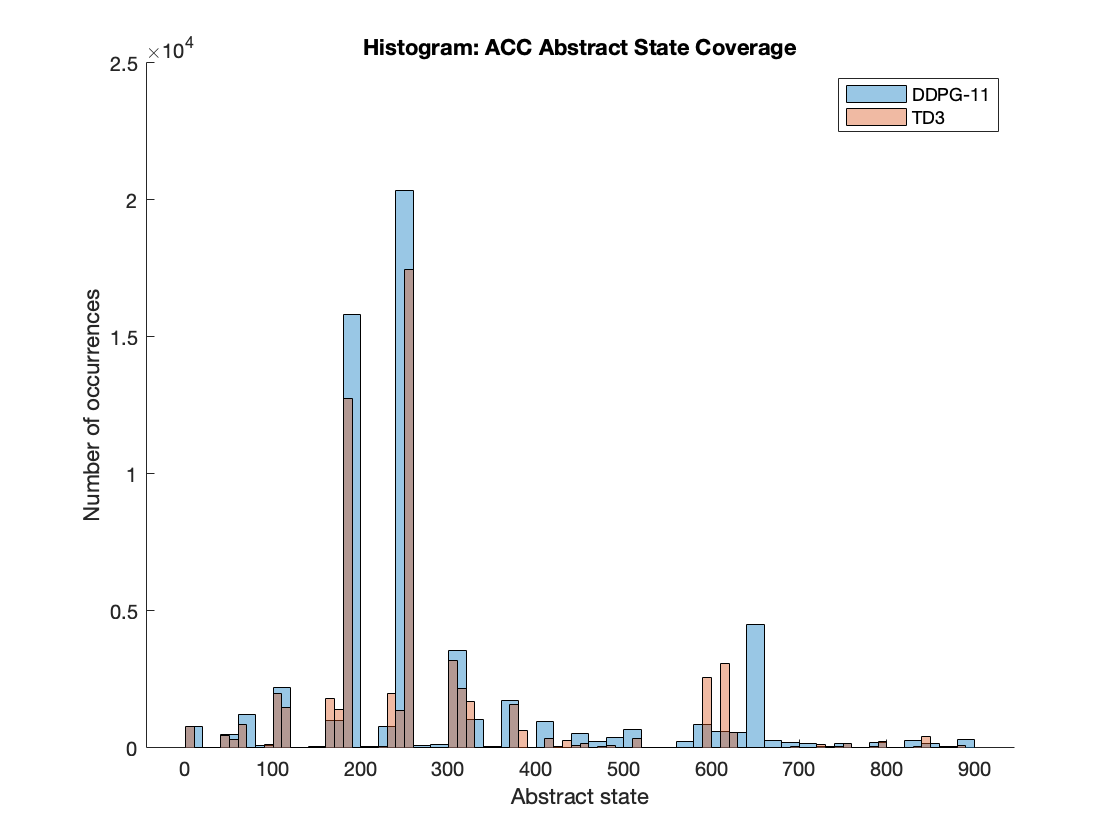

KS test: DDPG-11 and TD3: H1 


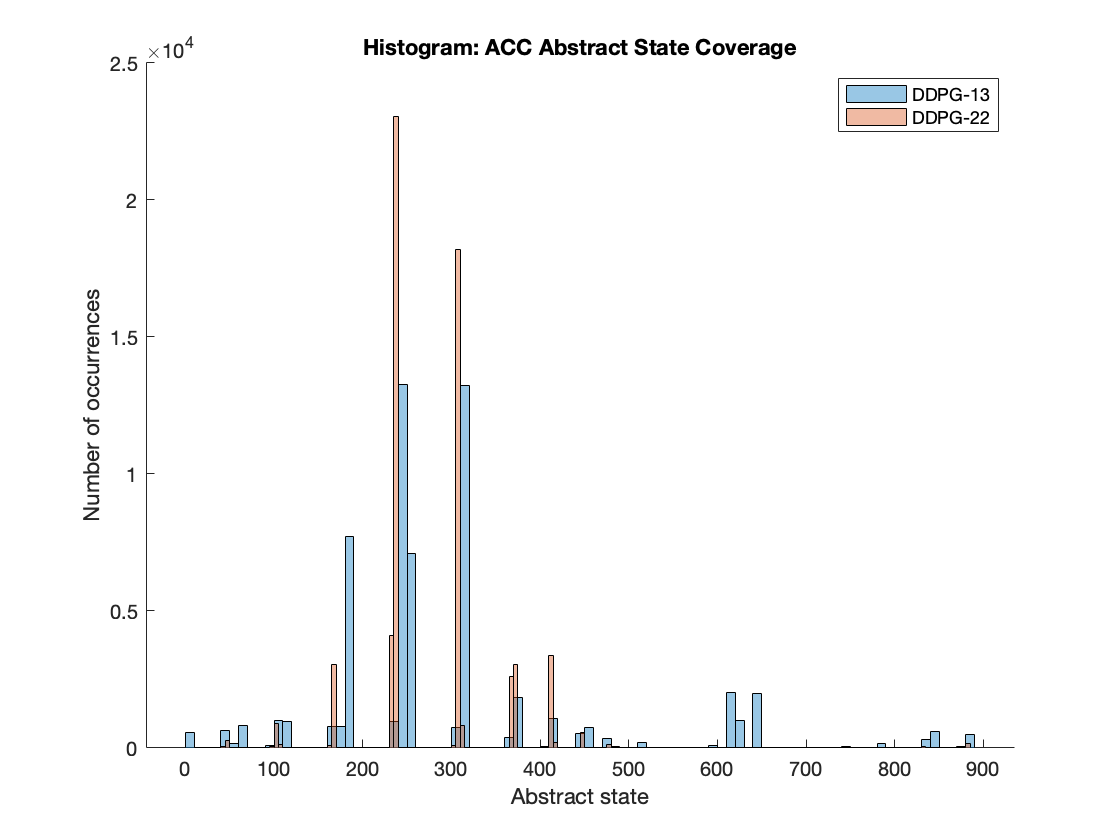

KS test: DDPG-13 and DDPG-22: H1 


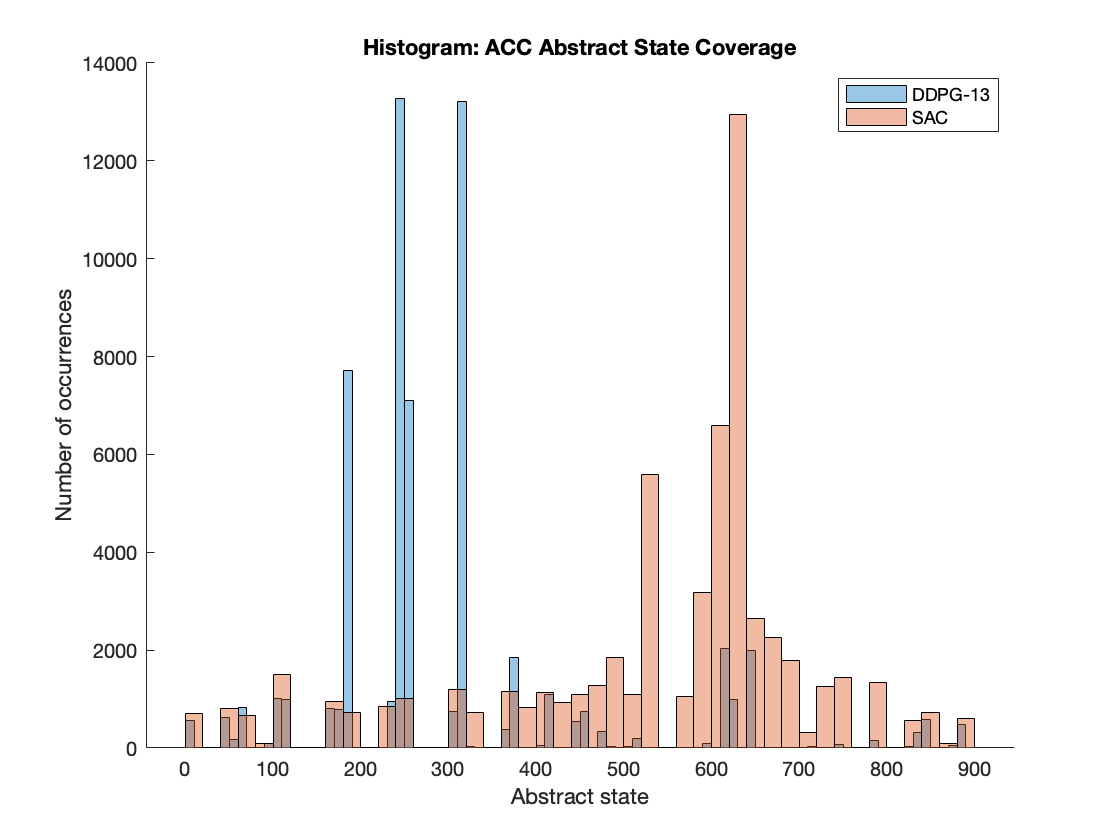

KS test: DDPG-13 and SAC: H1 


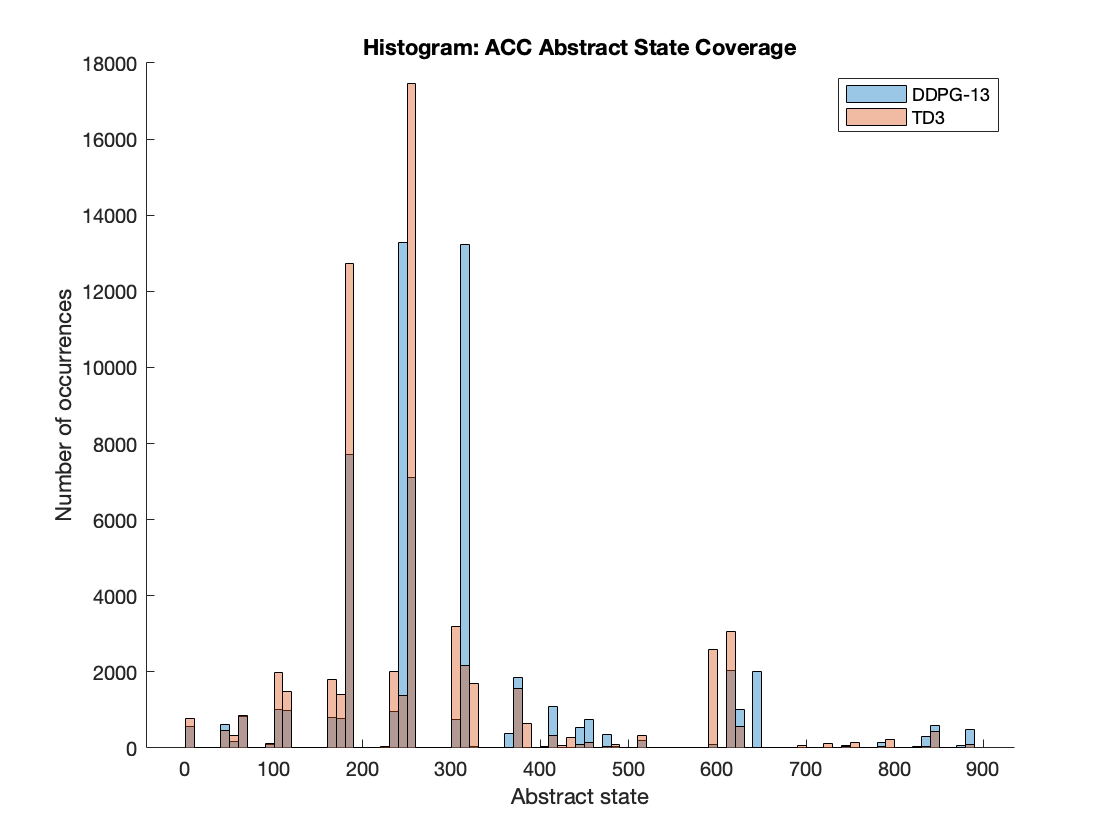

KS test: DDPG-13 and TD3: H1 


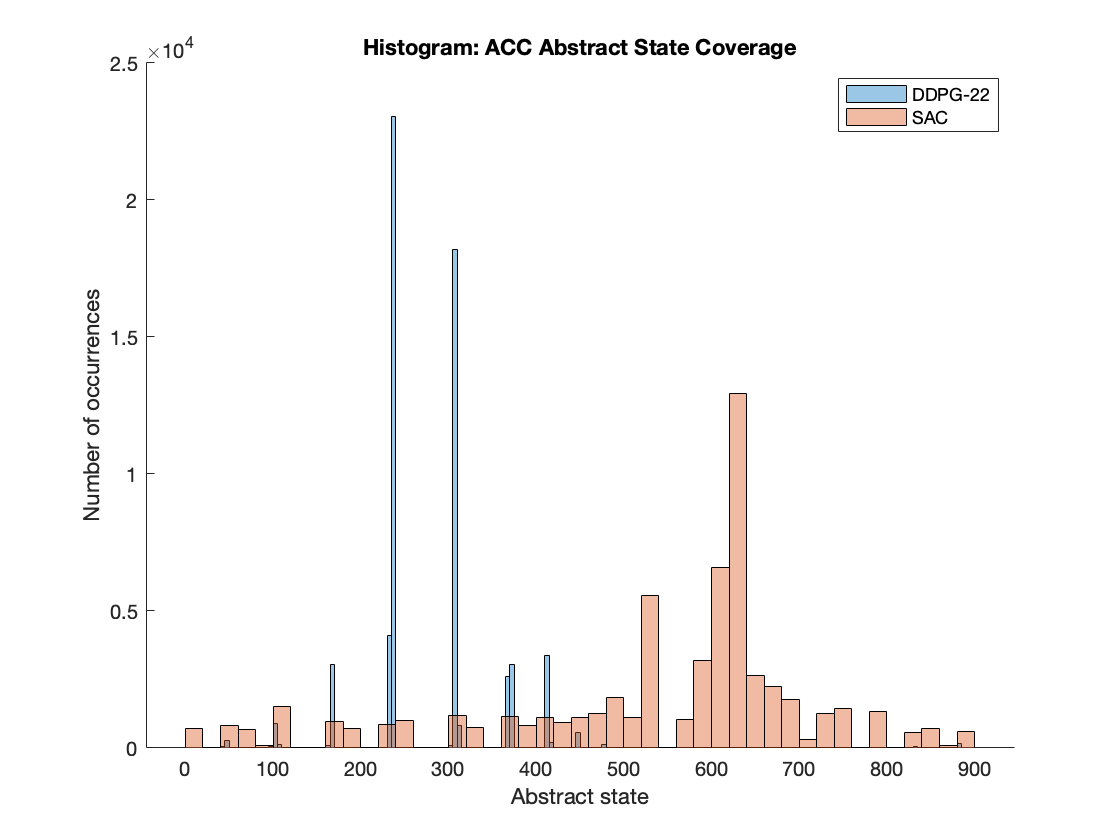

KS test: DDPG-22 and SAC: H1 


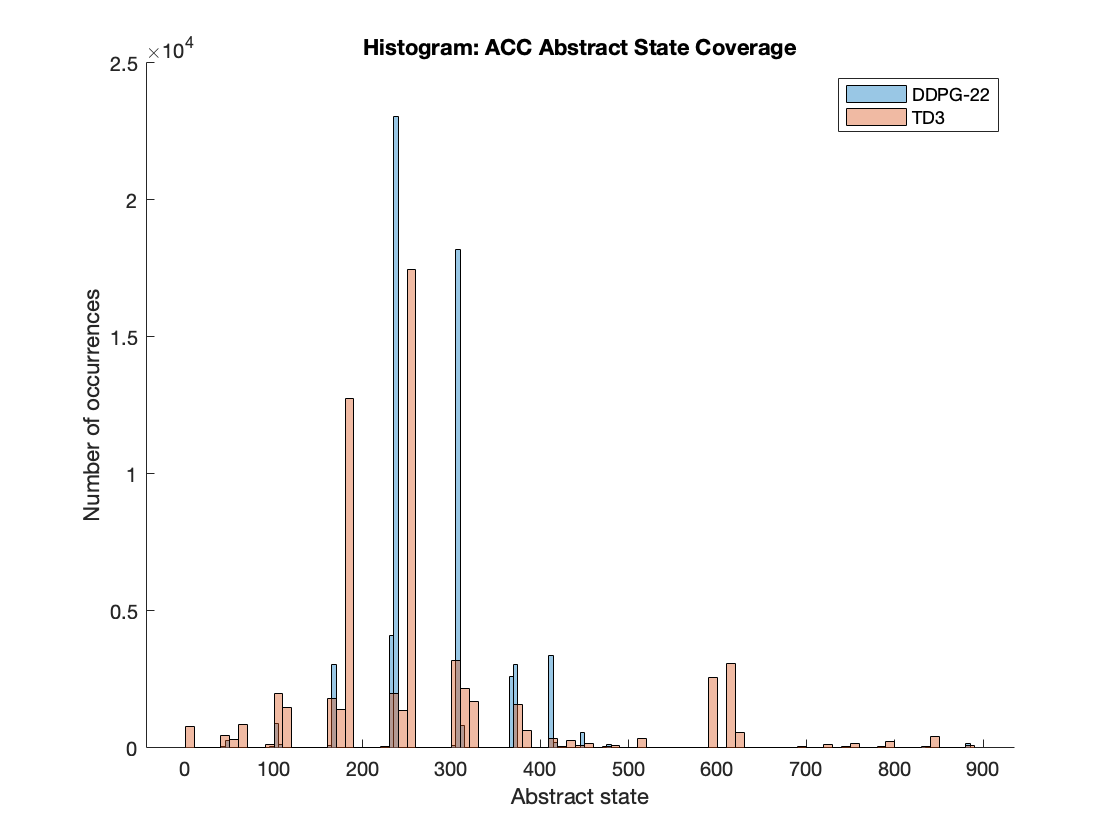

KS test: DDPG-22 and TD3: H1 


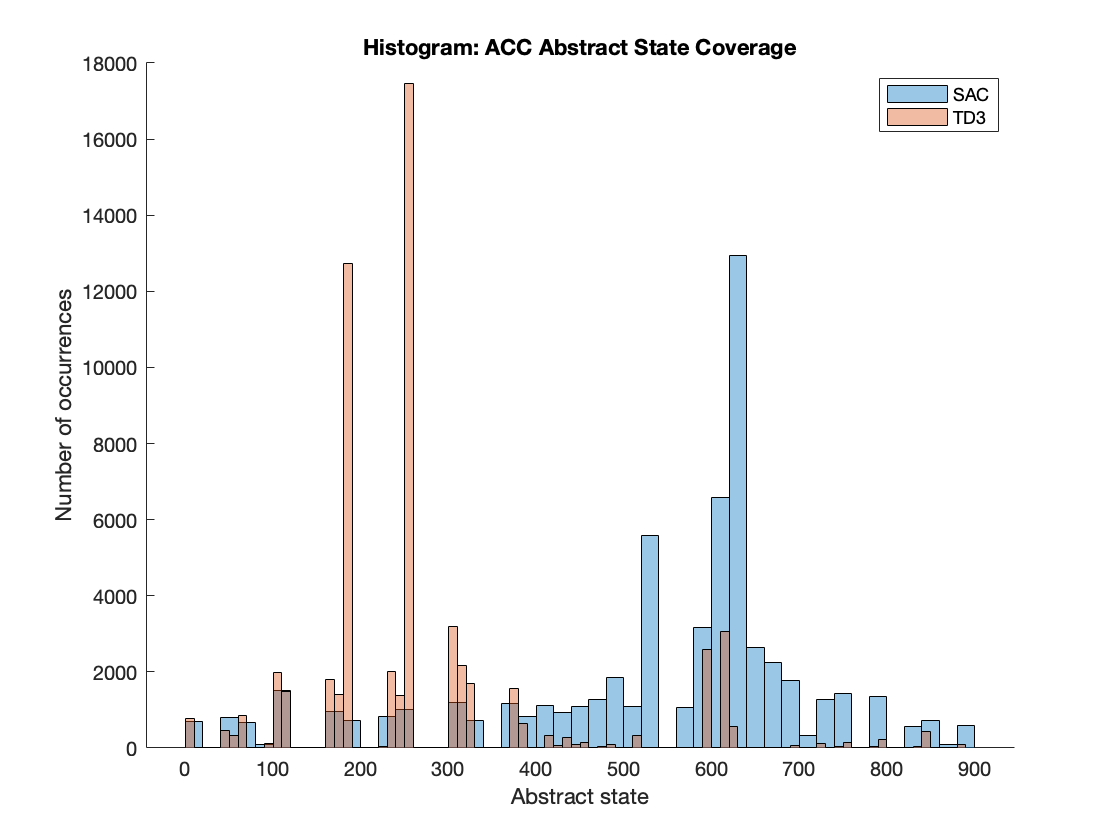

KS test: SAC and TD3: H1 


for i = 1:numController-1
    for j=i+1:numController
        h = kstest2(abStateOfEach{i},abStateOfEach{j}, "Alpha",0.05);
        if h
            res = "H1";
        else
            res = "H0";
        end
        figure;
        hold on
        histogram(abStateOfEach{i}, 'FaceAlpha',0.4);
        histogram(abStateOfEach{j}, 'FaceAlpha',0.4);
        hold off
        legend(controllerName(i), controllerName(j));
        title("Histogram: ACC Abstract State Coverage");
        xlabel('Abstract state') 
        ylabel('Number of occurrences') 

        fprintf("KS test: %s and %s: %s \n",controllerName(i), controllerName(j), res);
    end
end

## Abstract Transition Coverage

Histogram to how the number of occurrences of each distinct abstract transition

% histogram of abstract transition of all controllers
abTran = [abTranSpace(:,4);0];
abTranOfEach = cell(numController,1);      % cell array contain abTran of each controller
tranOfEach = length(abTran)/numController;

figure;
hold on

for i = 1:numController
    abTranOfEach{i} = abTran((i-1)*tranOfEach+1:i*tranOfEach);
    histogram(abTranOfEach{i}, 'FaceAlpha',0.4);
end

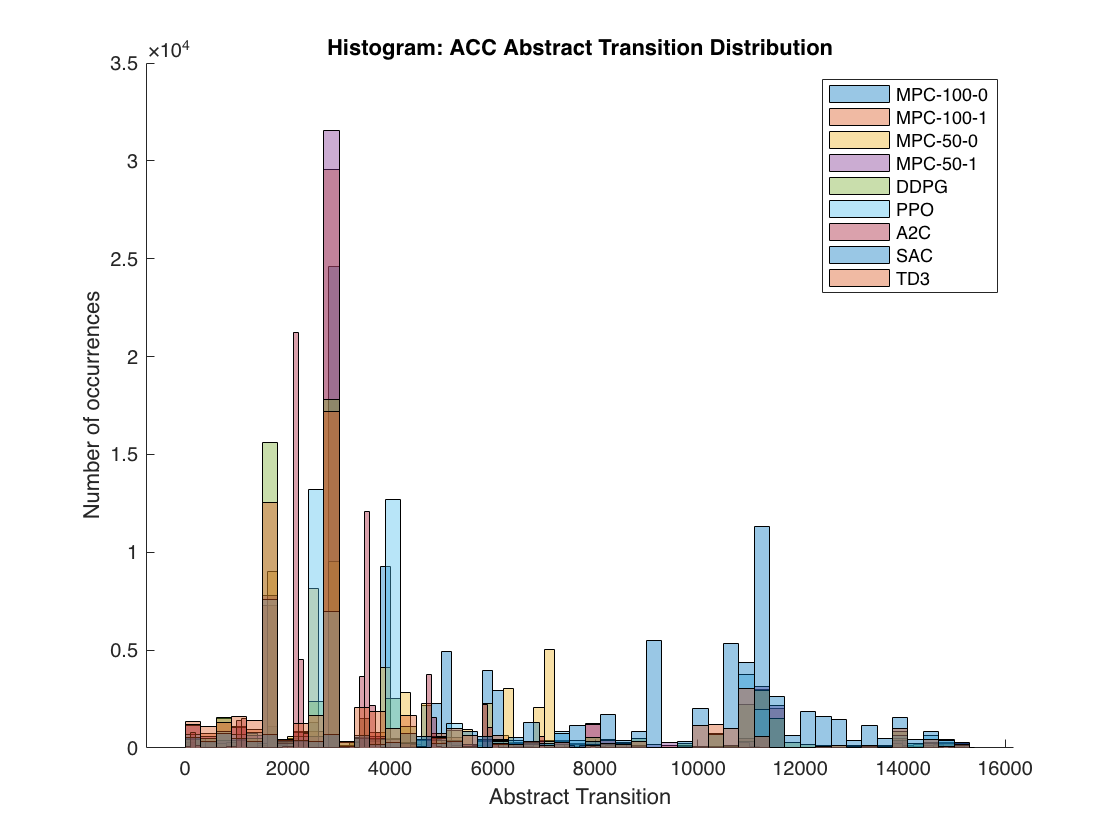

hold off
legend(controllerName);
title("Histogram: ACC Abstract Transition Distribution");
xlabel('Abstract Transition') 
ylabel('Number of occurrences') 

## Abstract Transition Coverage

abTranCov = zeros(numController,1);      % cell array contain basic state coverage of each controller

for i = 1:numController
    abTranCov(i) = length(unique(abTranOfEach{i}))/numAbTran;
    fprintf("BSCov of %s: %.2f \n",controllerName(i), abTranCov(i));
end

BSCov of MPC-100-0: 0.05 
BSCov of MPC-100-1: 0.19 
BSCov of MPC-50-0: 0.10 
BSCov of MPC-50-1: 0.29 
BSCov of DDPG-11: 0.34 
BSCov of DDPG-13: 0.18 
BSCov of DDPG-22: 0.05 
BSCov of SAC: 0.45 
BSCov of TD3: 0.09 


## Kolmogorov-Smirnov (KS) test for Abstract State Distribution

Do KS test on abstract transition distribution betwwen each two controllers 

H0: two samples are from the same continuous distribution

H1: two samples are from  different continuous distributions

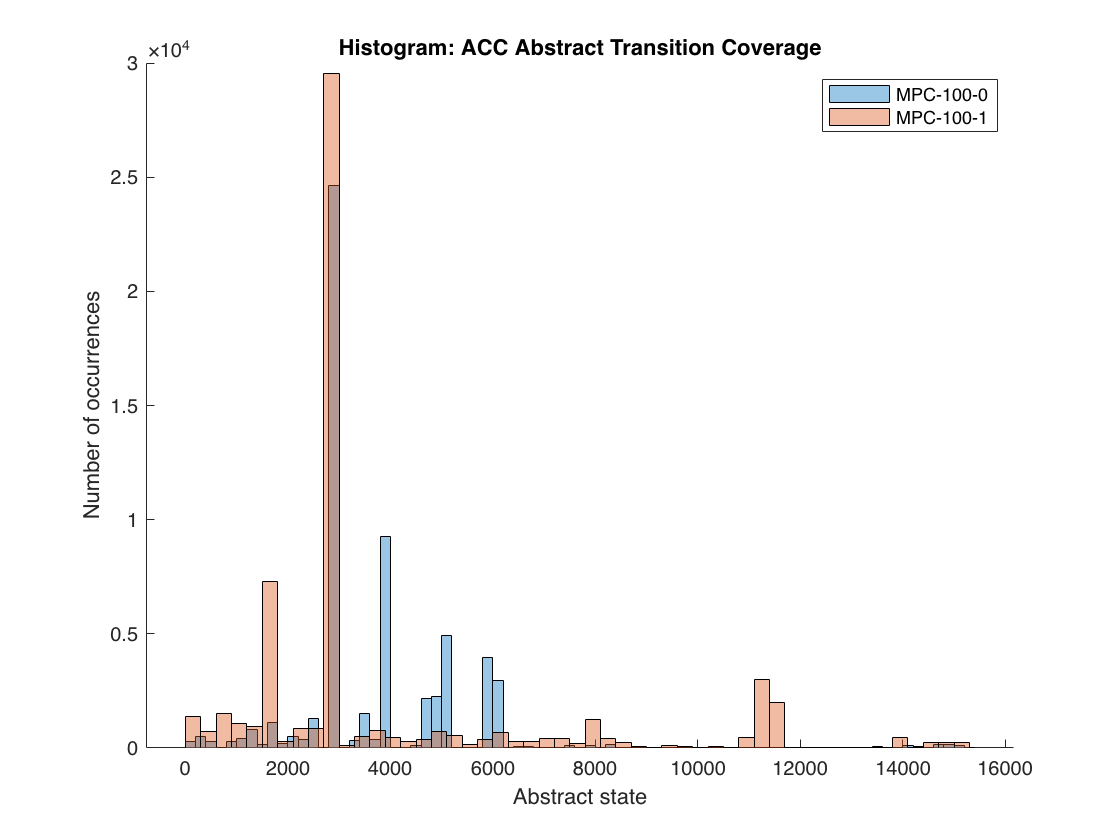

KS test: MPC-100-0 and MPC-100-1: H1 


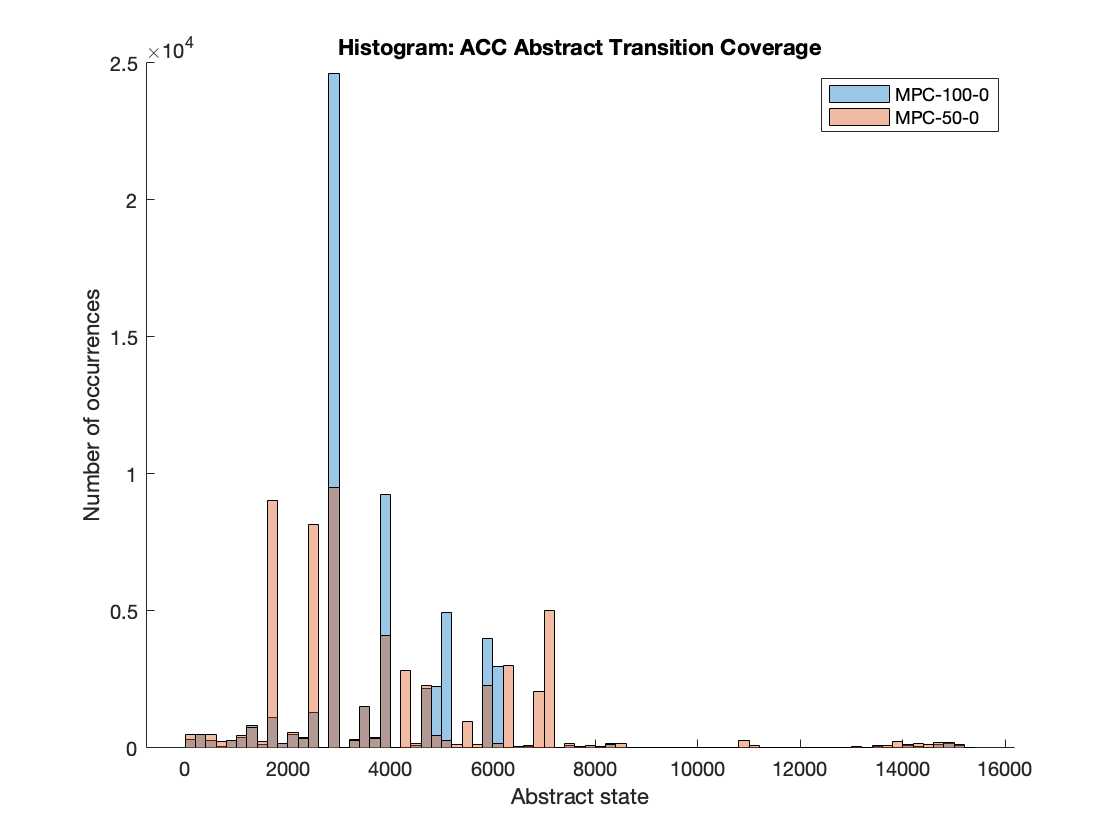

KS test: MPC-100-0 and MPC-50-0: H1 


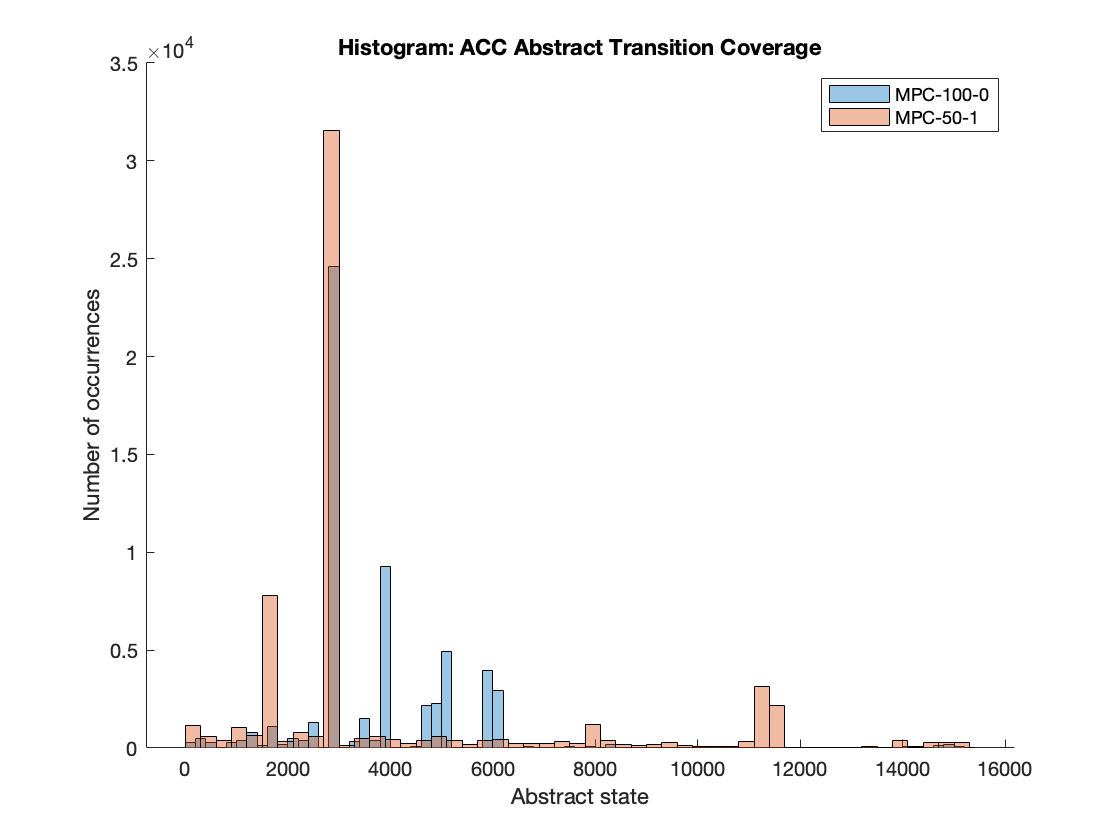

KS test: MPC-100-0 and MPC-50-1: H1 


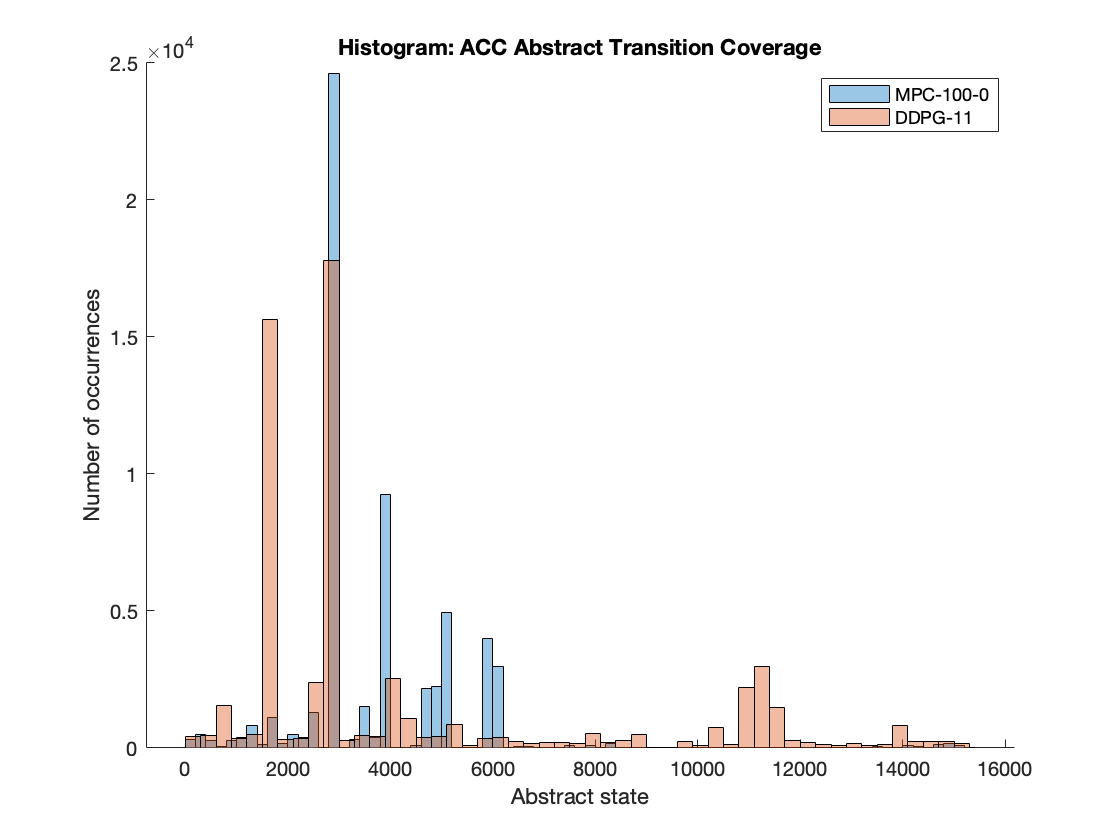

KS test: MPC-100-0 and DDPG-11: H1 


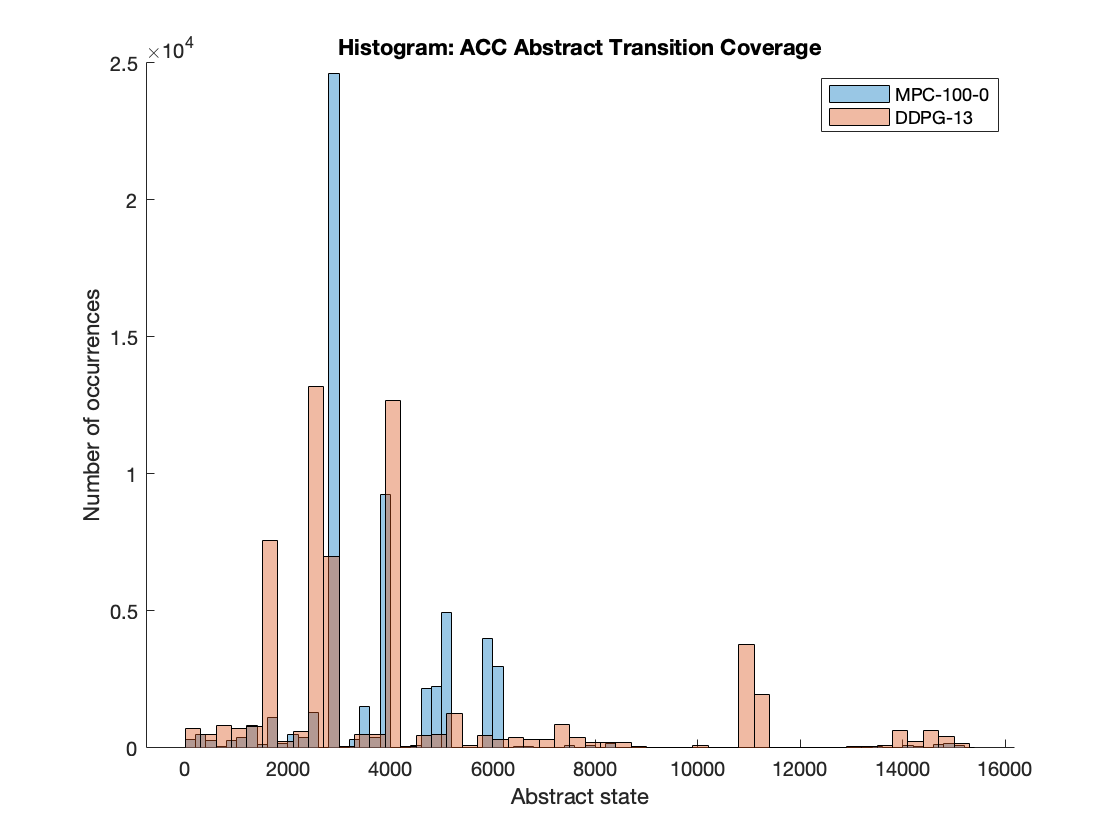

KS test: MPC-100-0 and DDPG-13: H1 


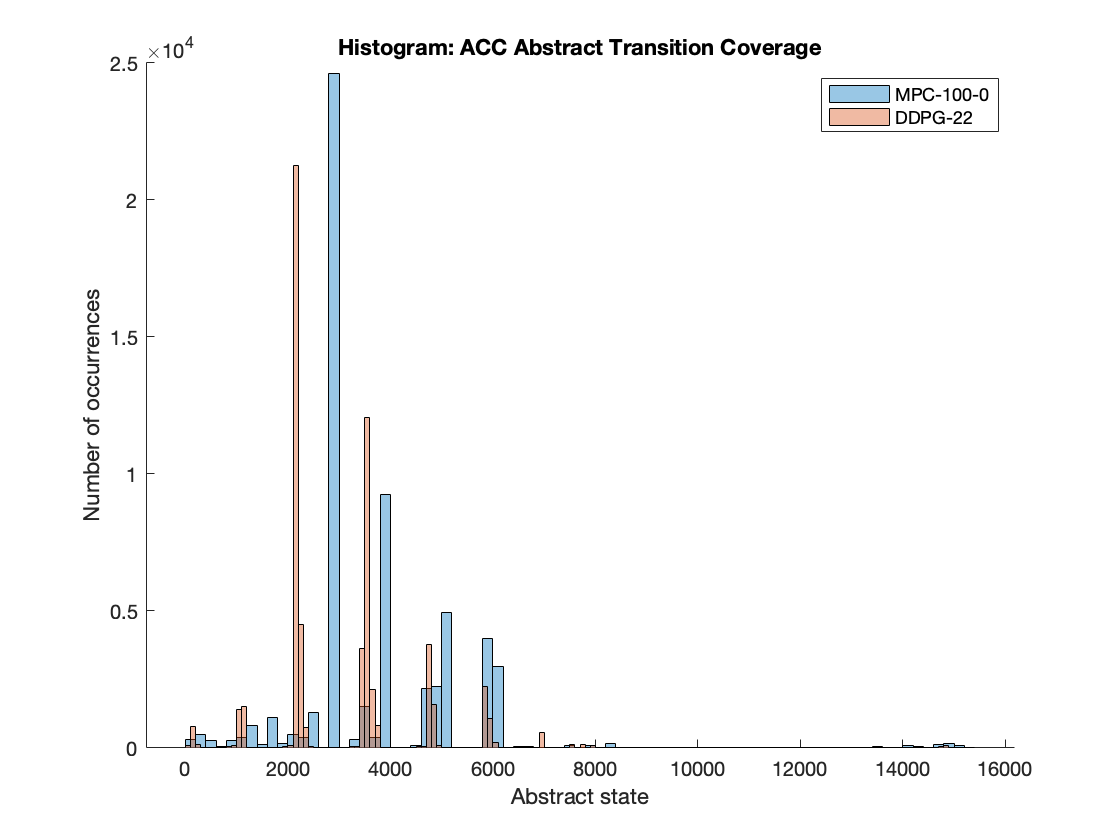

KS test: MPC-100-0 and DDPG-22: H1 


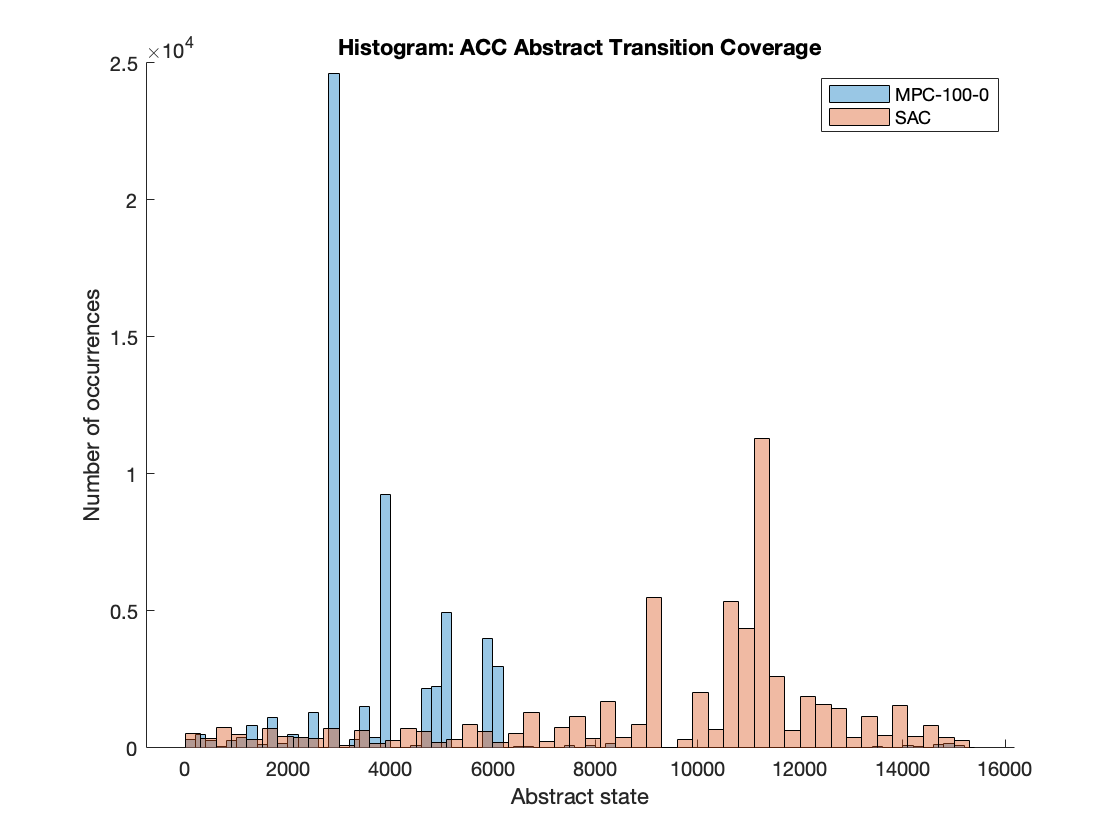

KS test: MPC-100-0 and SAC: H1 


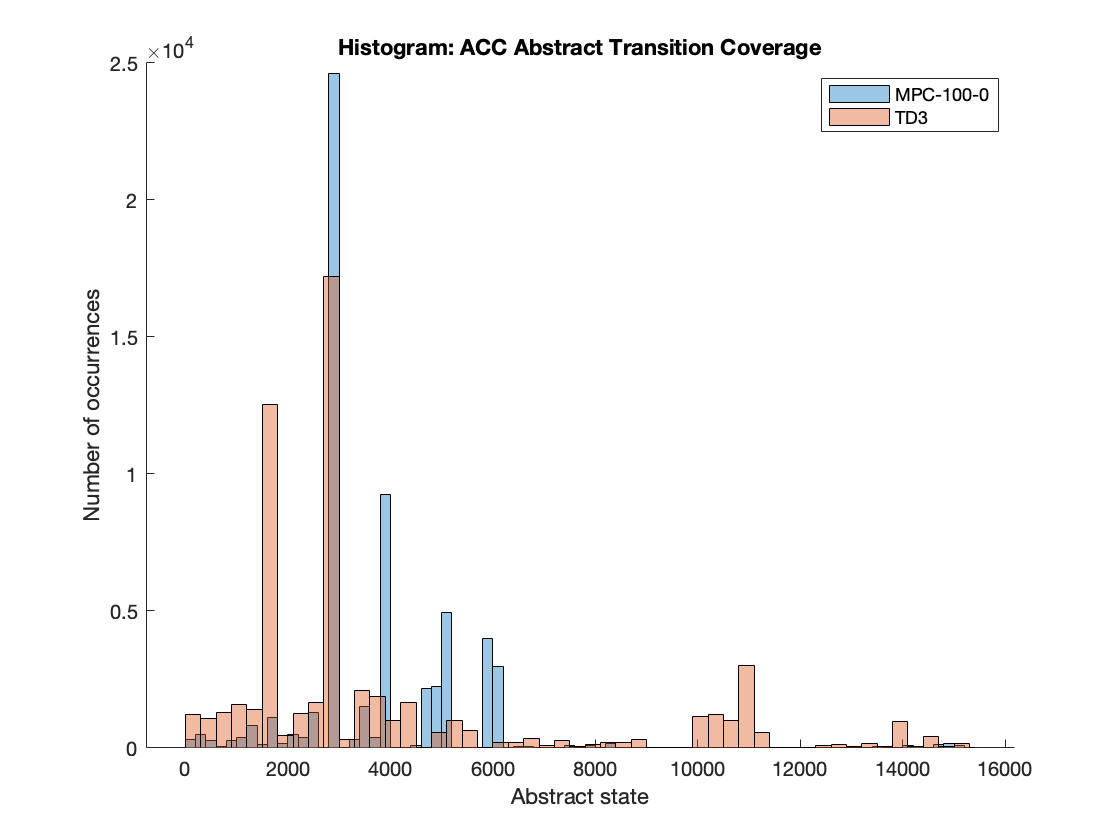

KS test: MPC-100-0 and TD3: H1 


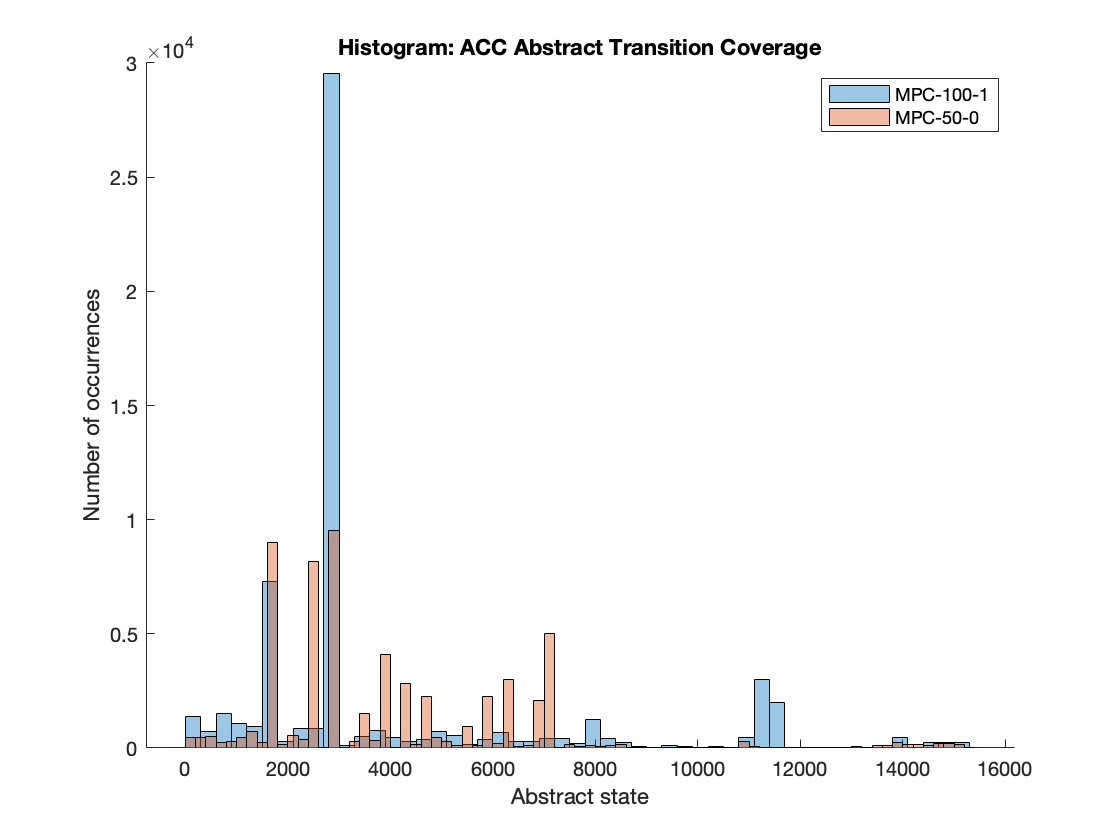

KS test: MPC-100-1 and MPC-50-0: H1 


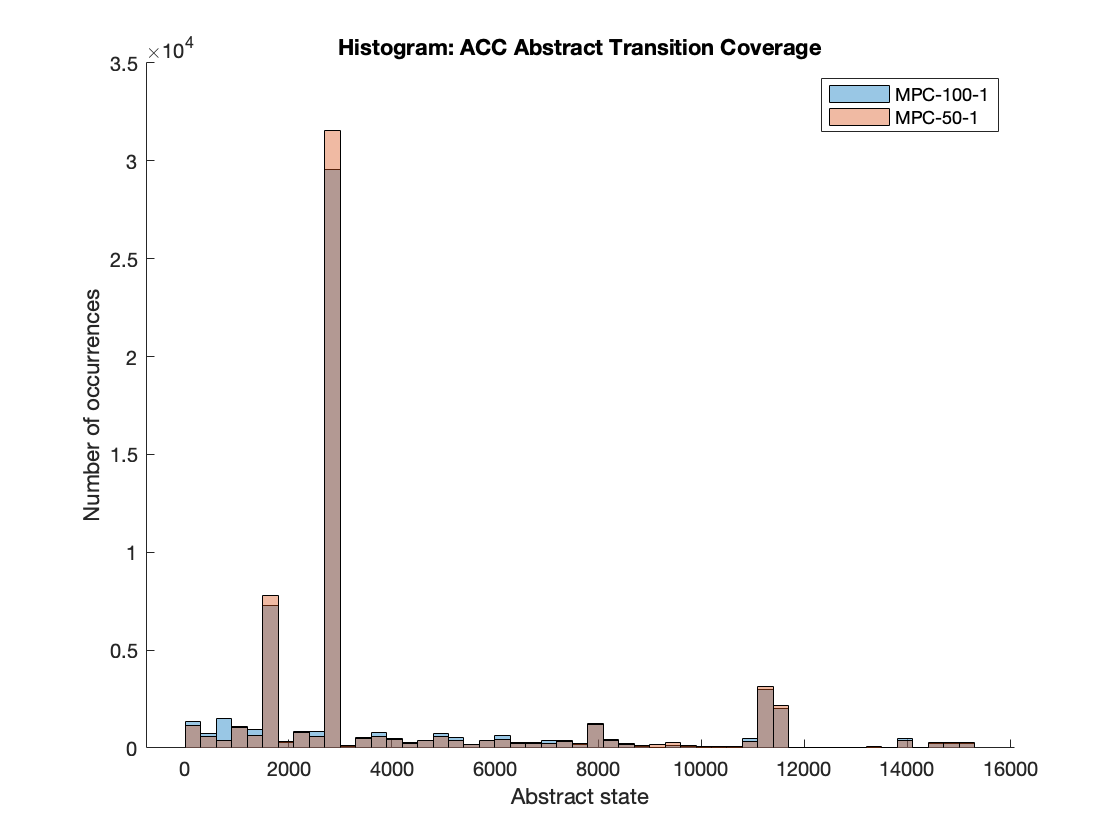

KS test: MPC-100-1 and MPC-50-1: H1 


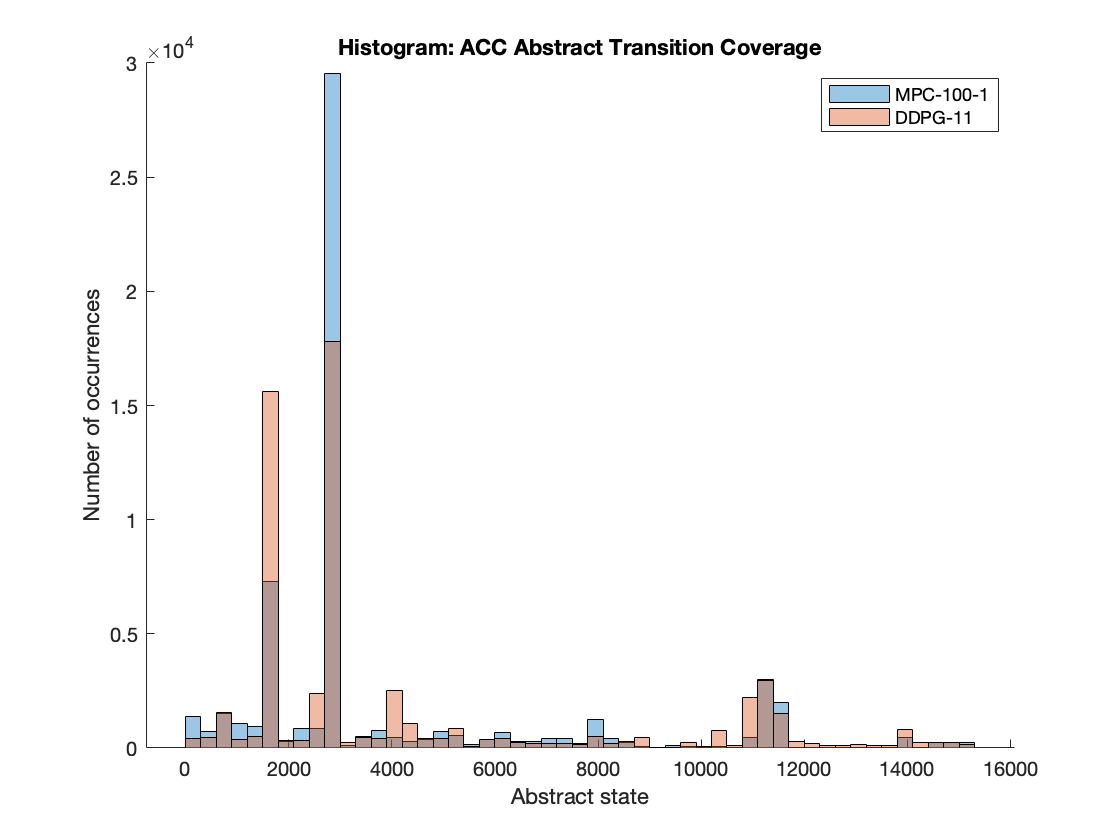

KS test: MPC-100-1 and DDPG-11: H1 


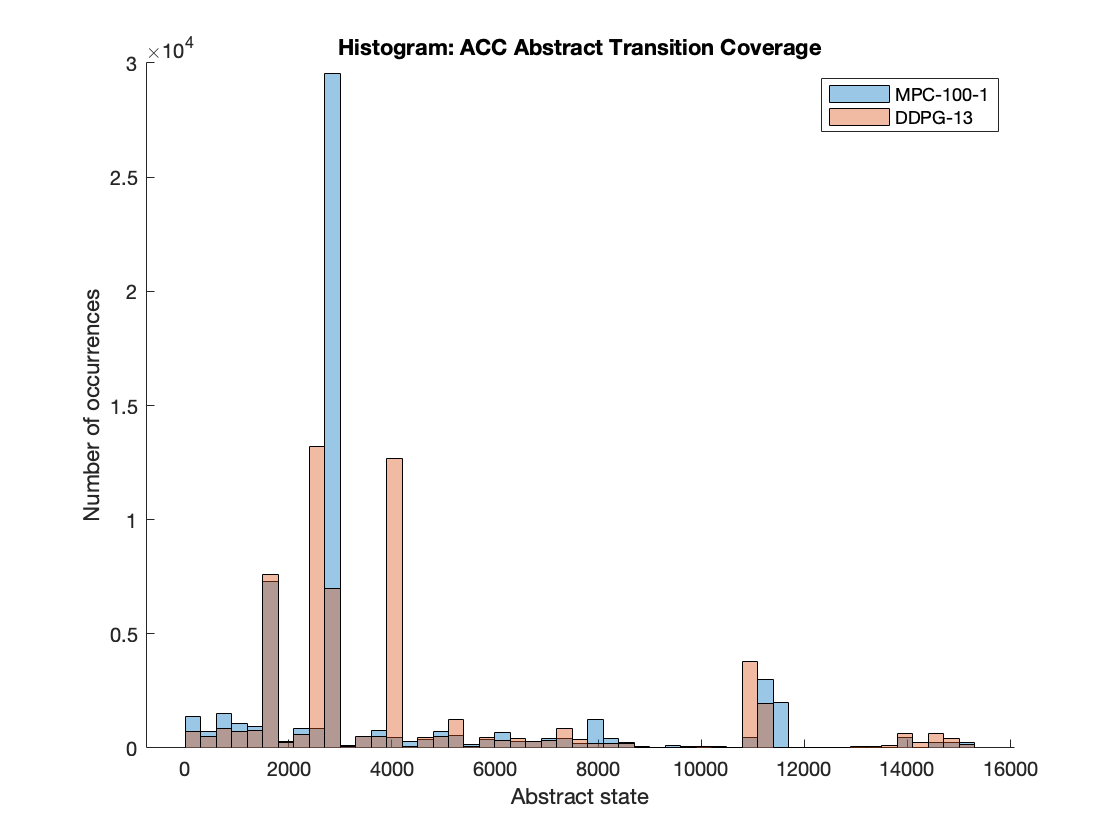

KS test: MPC-100-1 and DDPG-13: H1 


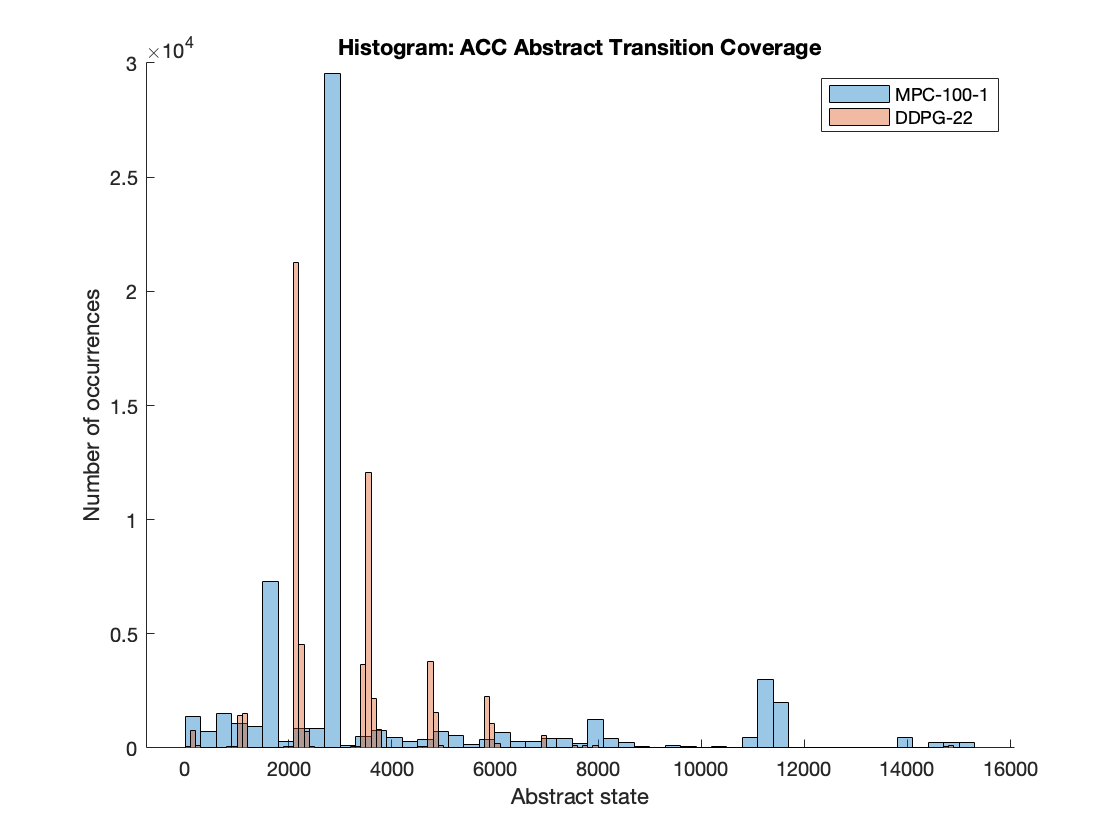

KS test: MPC-100-1 and DDPG-22: H1 


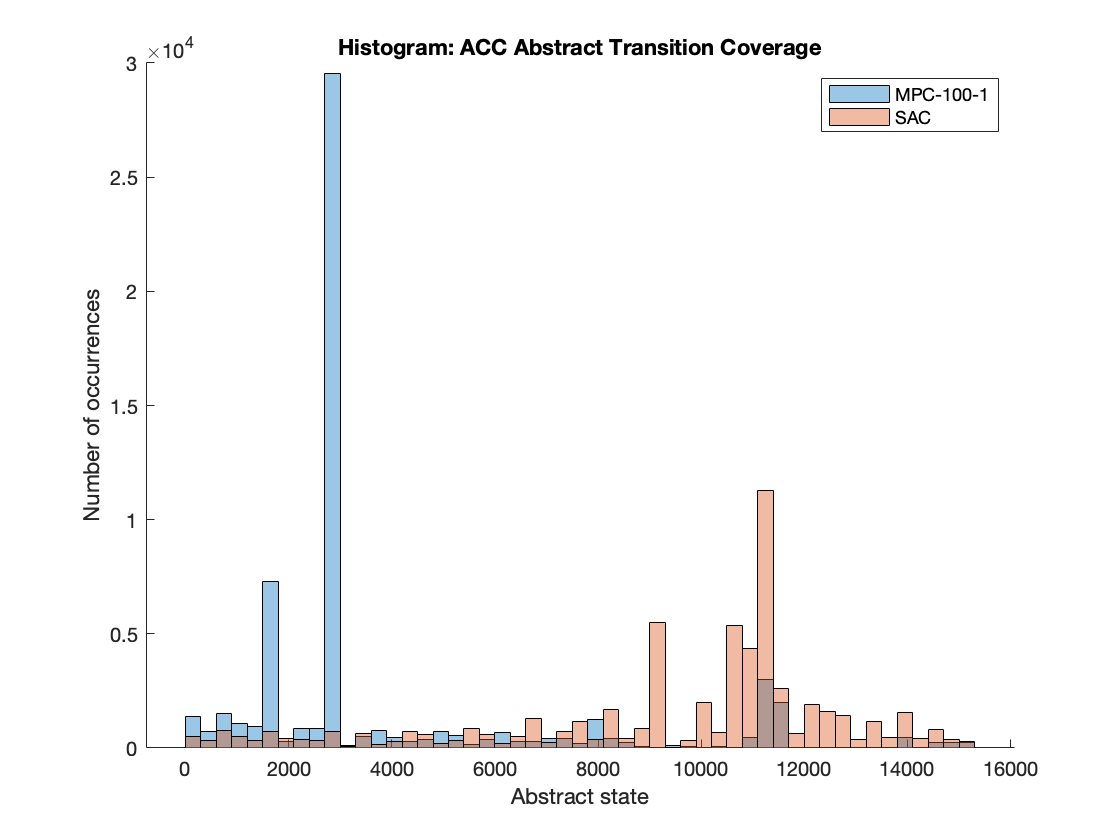

KS test: MPC-100-1 and SAC: H1 


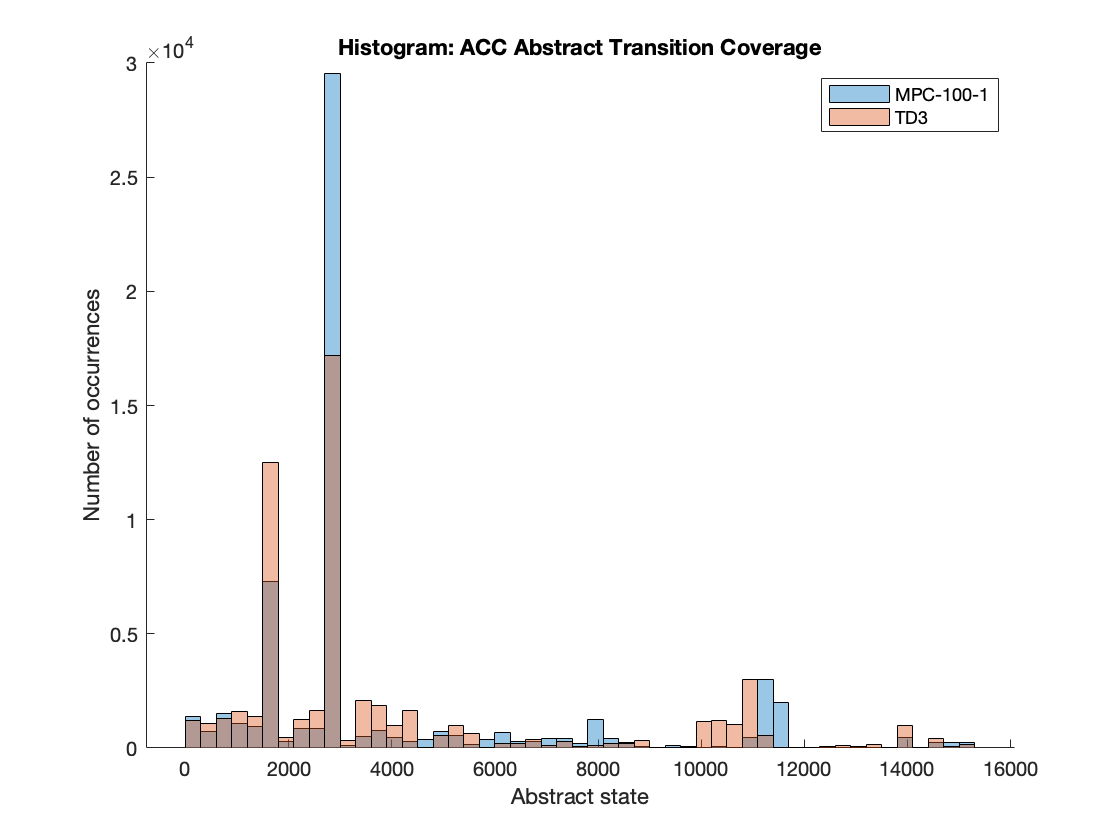

KS test: MPC-100-1 and TD3: H1 


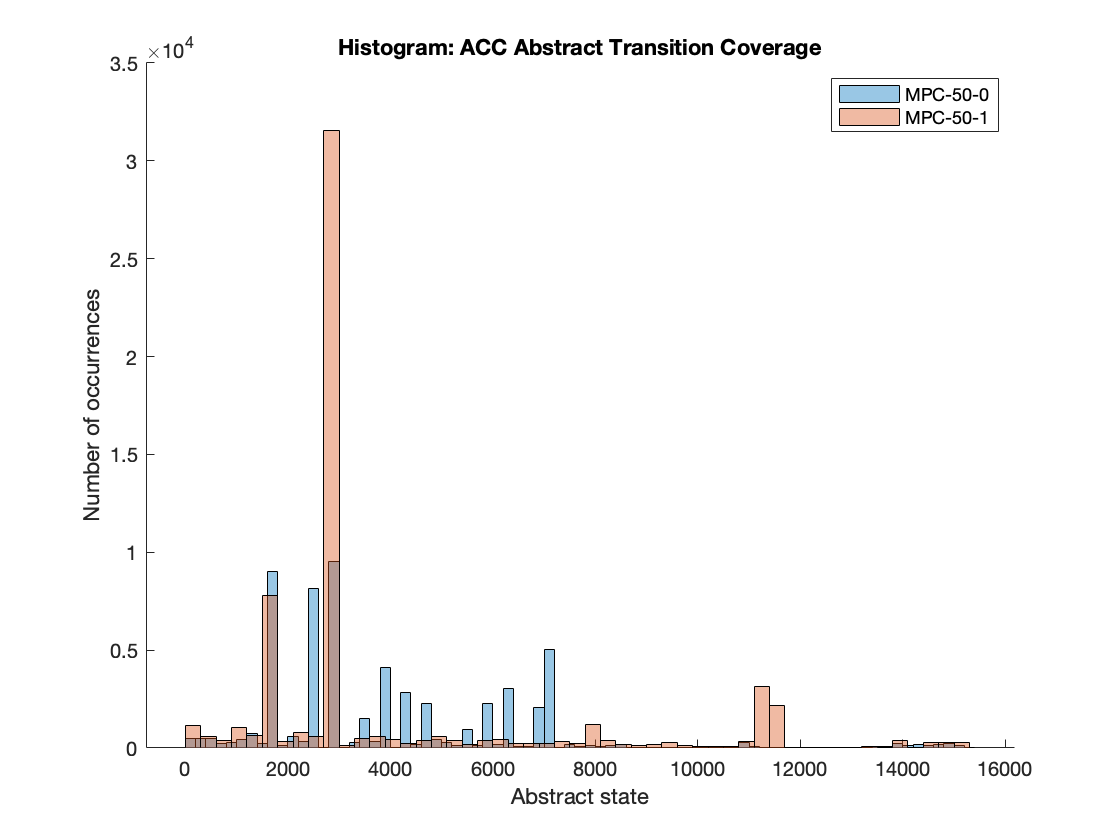

KS test: MPC-50-0 and MPC-50-1: H1 


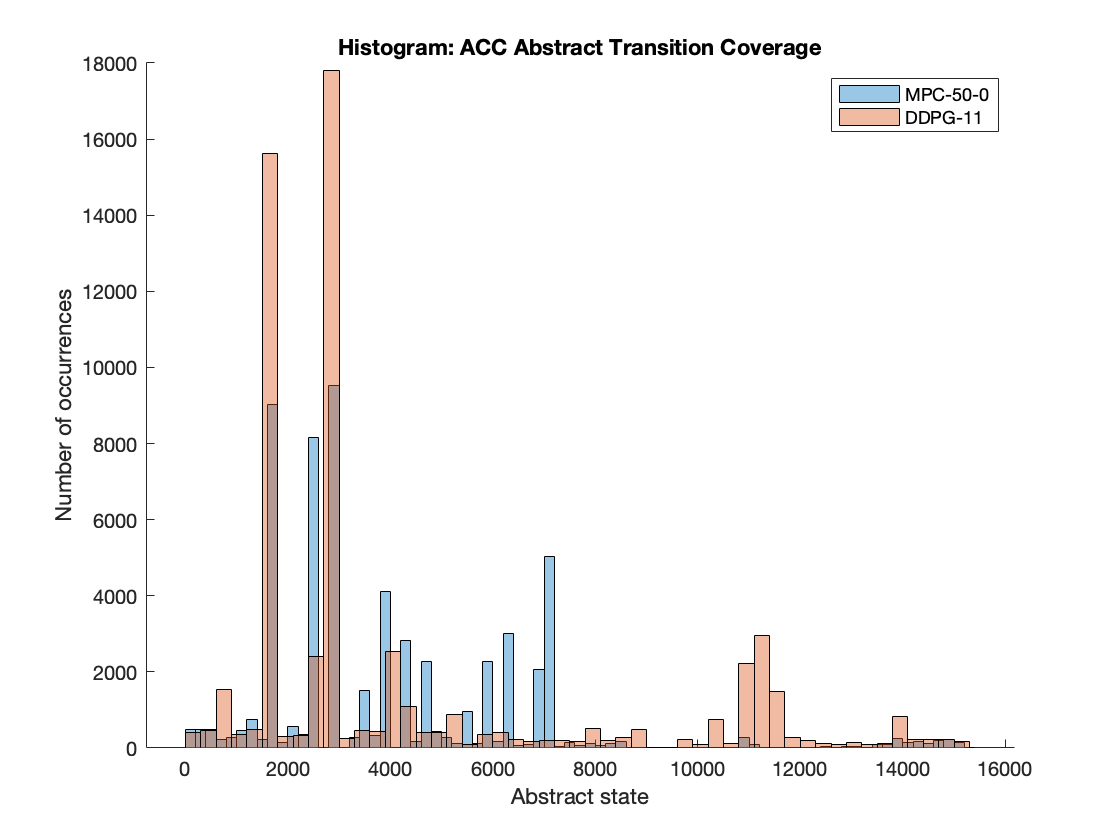

KS test: MPC-50-0 and DDPG-11: H1 


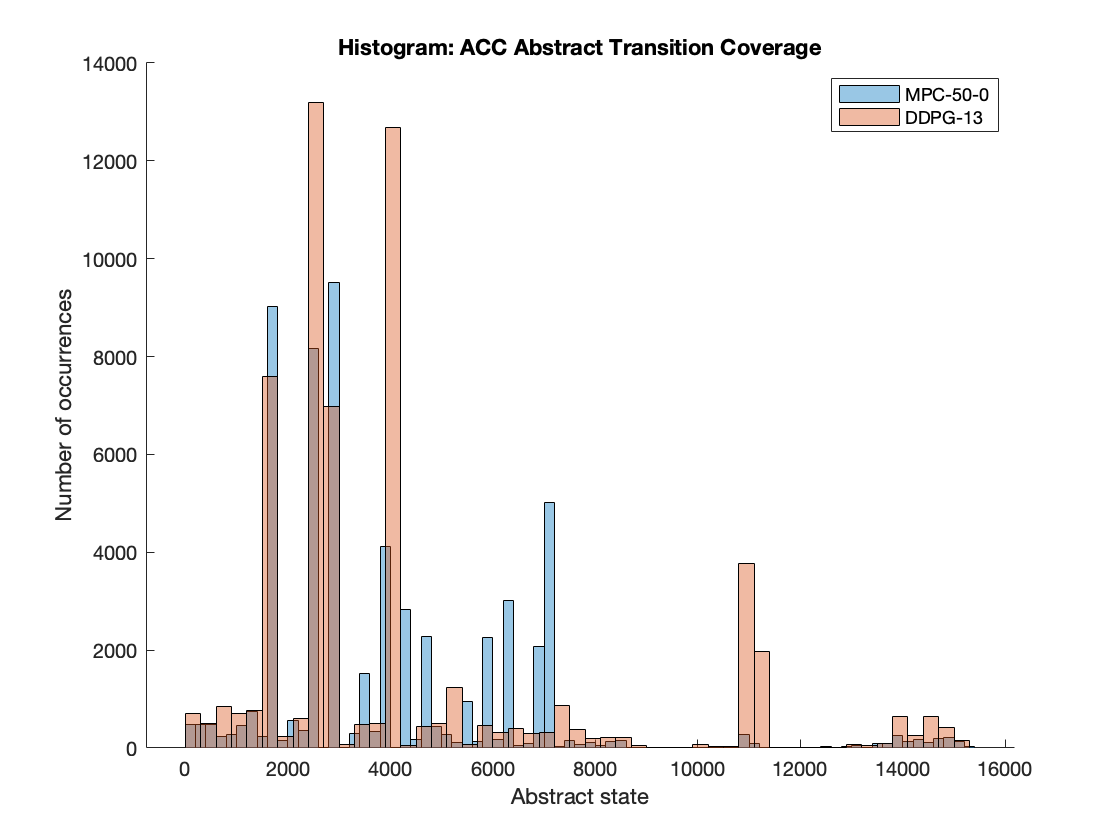

KS test: MPC-50-0 and DDPG-13: H1 


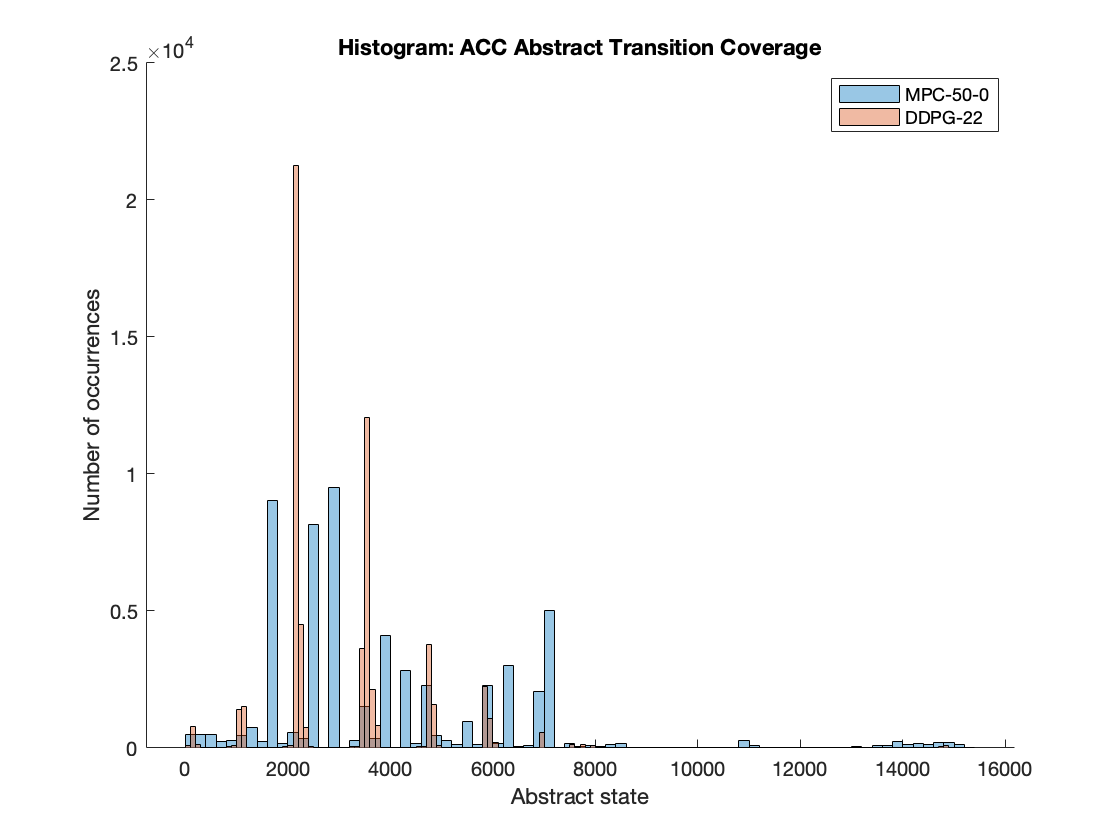

KS test: MPC-50-0 and DDPG-22: H1 


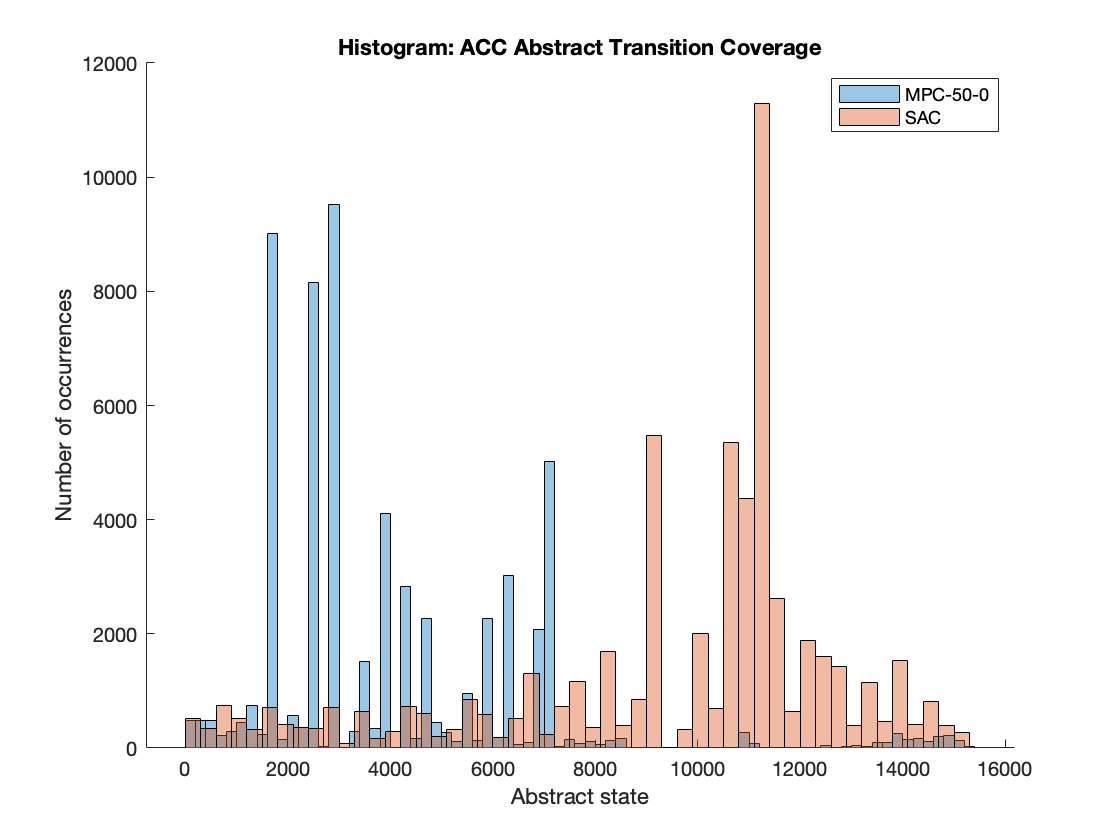

KS test: MPC-50-0 and SAC: H1 


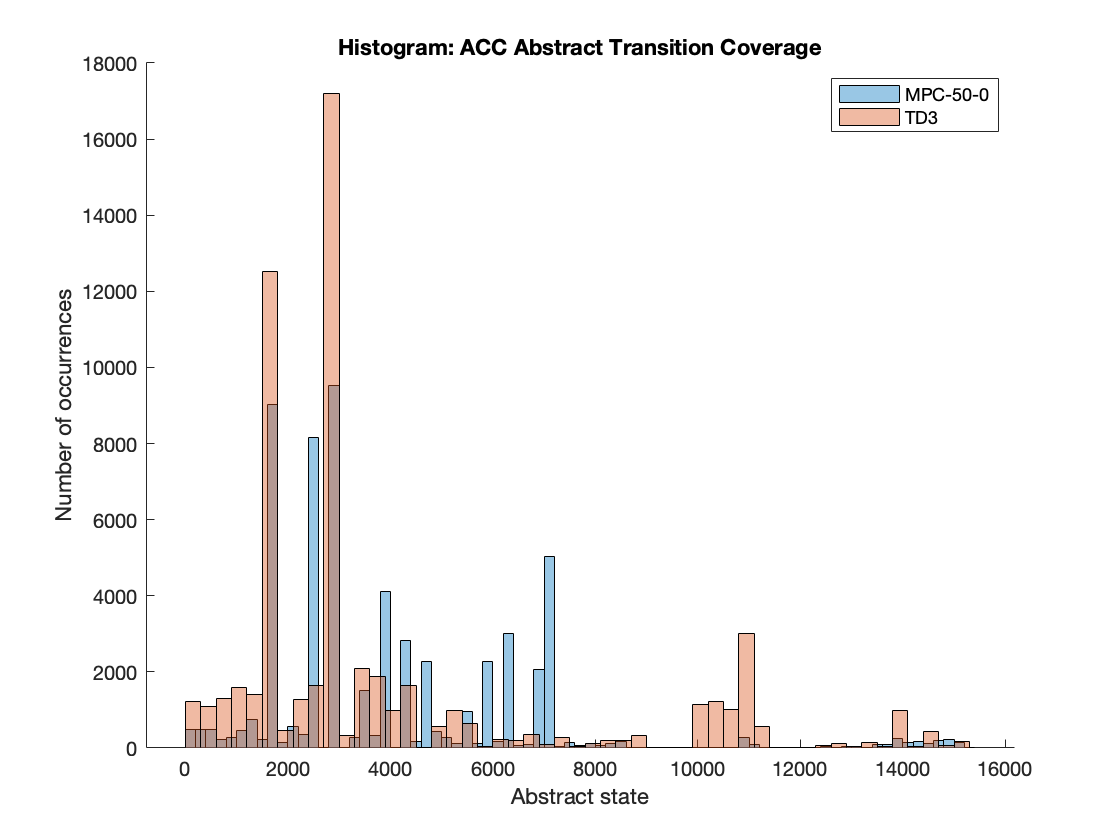

KS test: MPC-50-0 and TD3: H1 


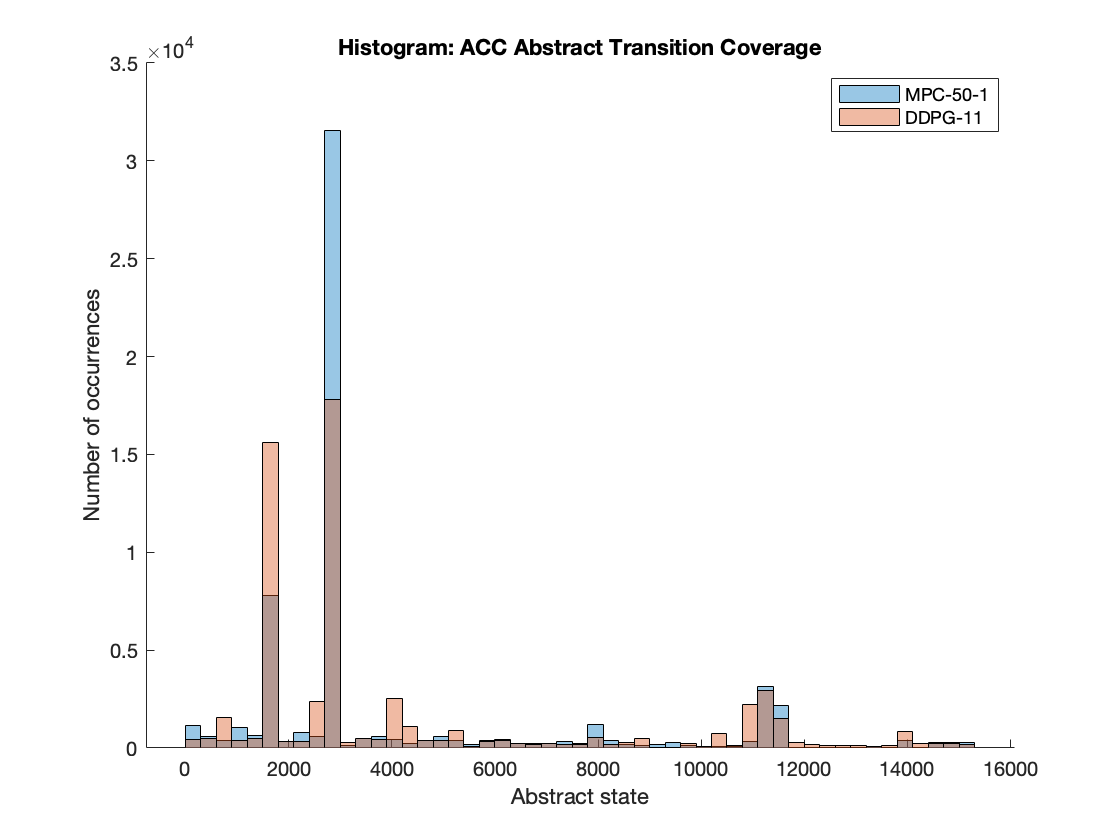

KS test: MPC-50-1 and DDPG-11: H1 


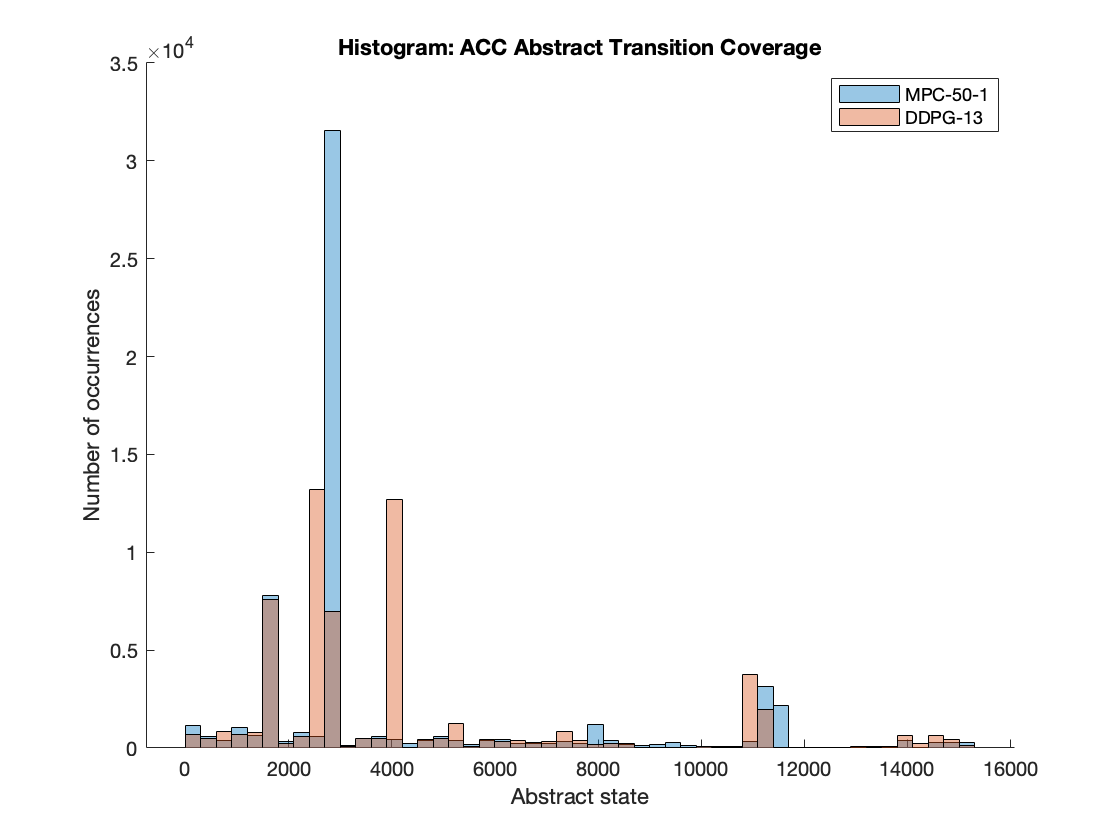

KS test: MPC-50-1 and DDPG-13: H1 


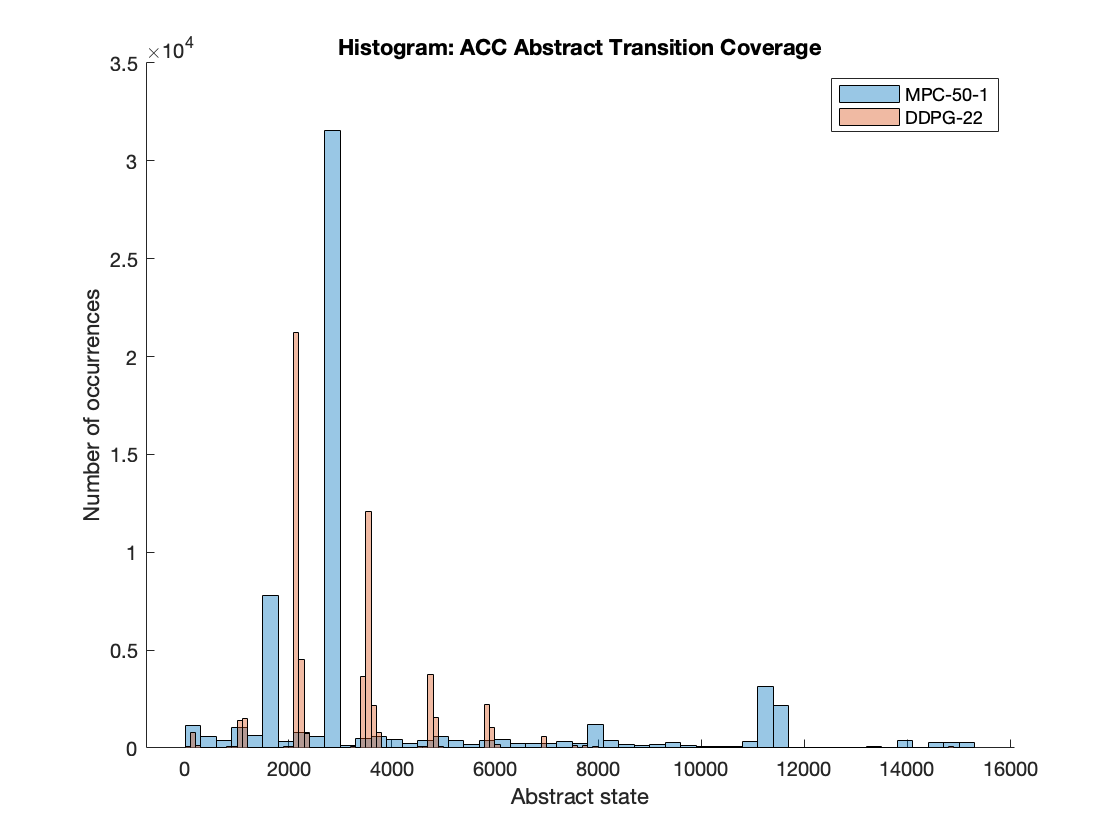

KS test: MPC-50-1 and DDPG-22: H1 


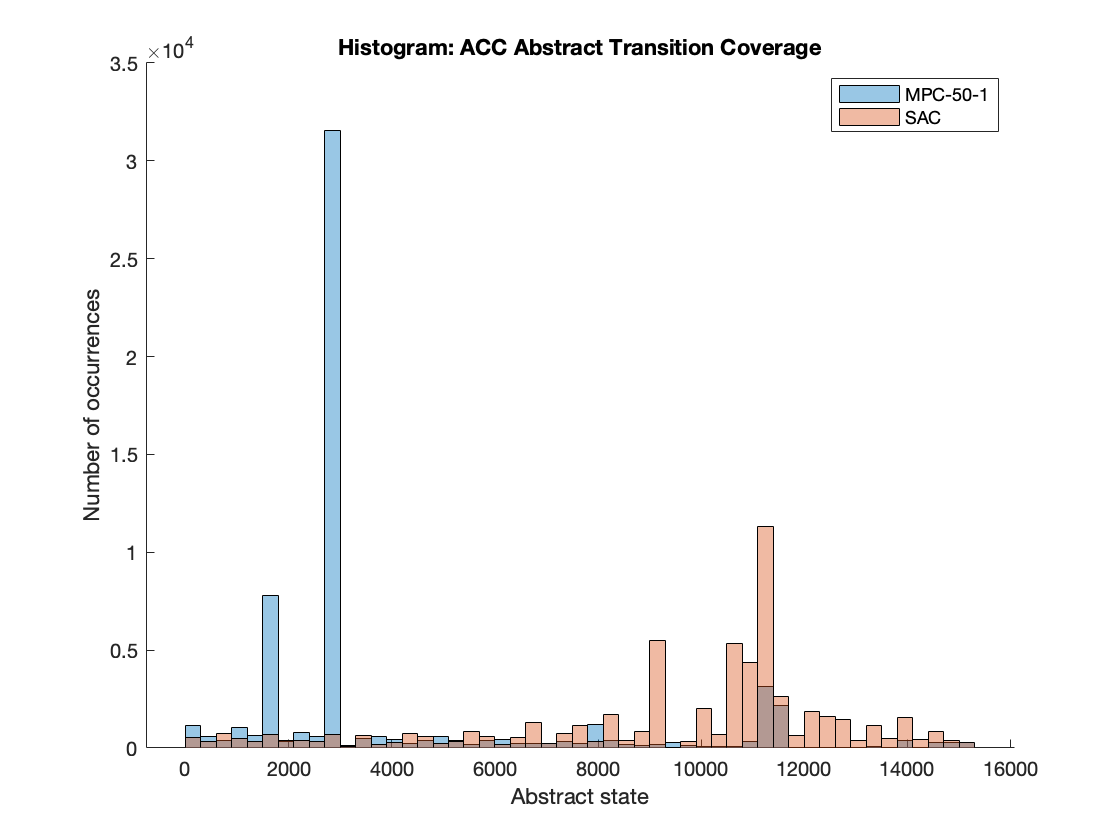

KS test: MPC-50-1 and SAC: H1 


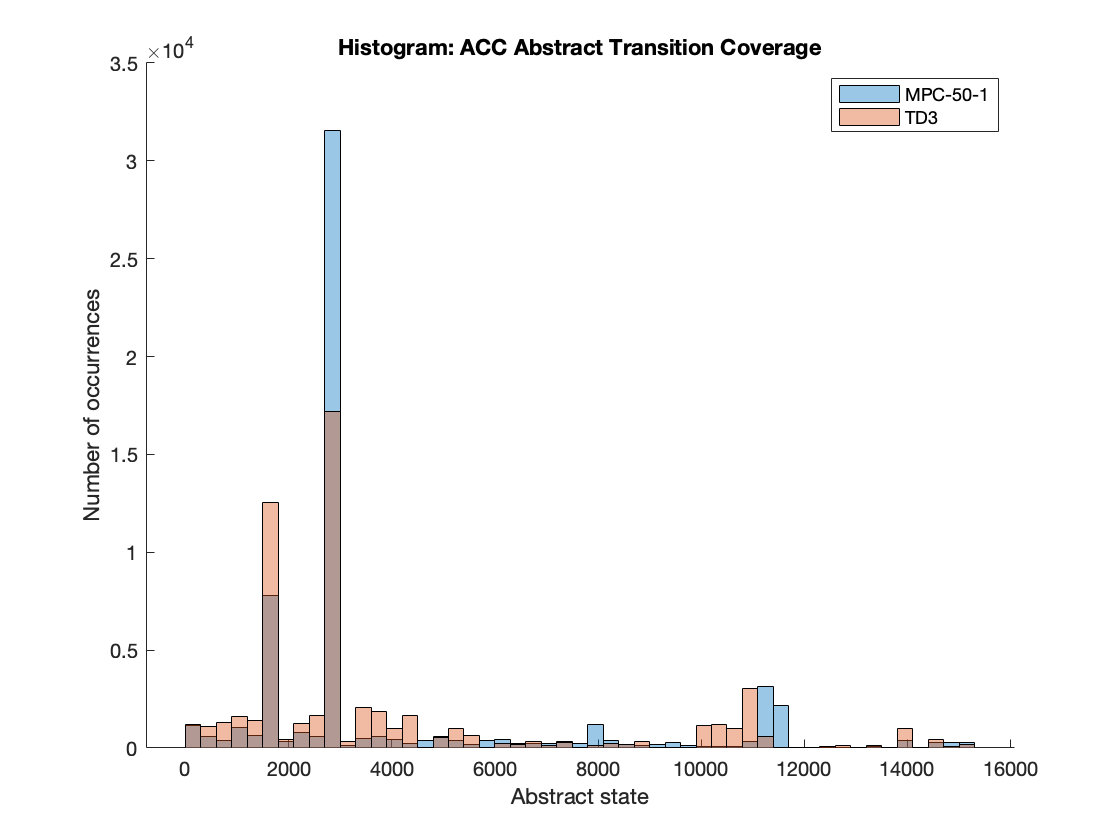

KS test: MPC-50-1 and TD3: H1 


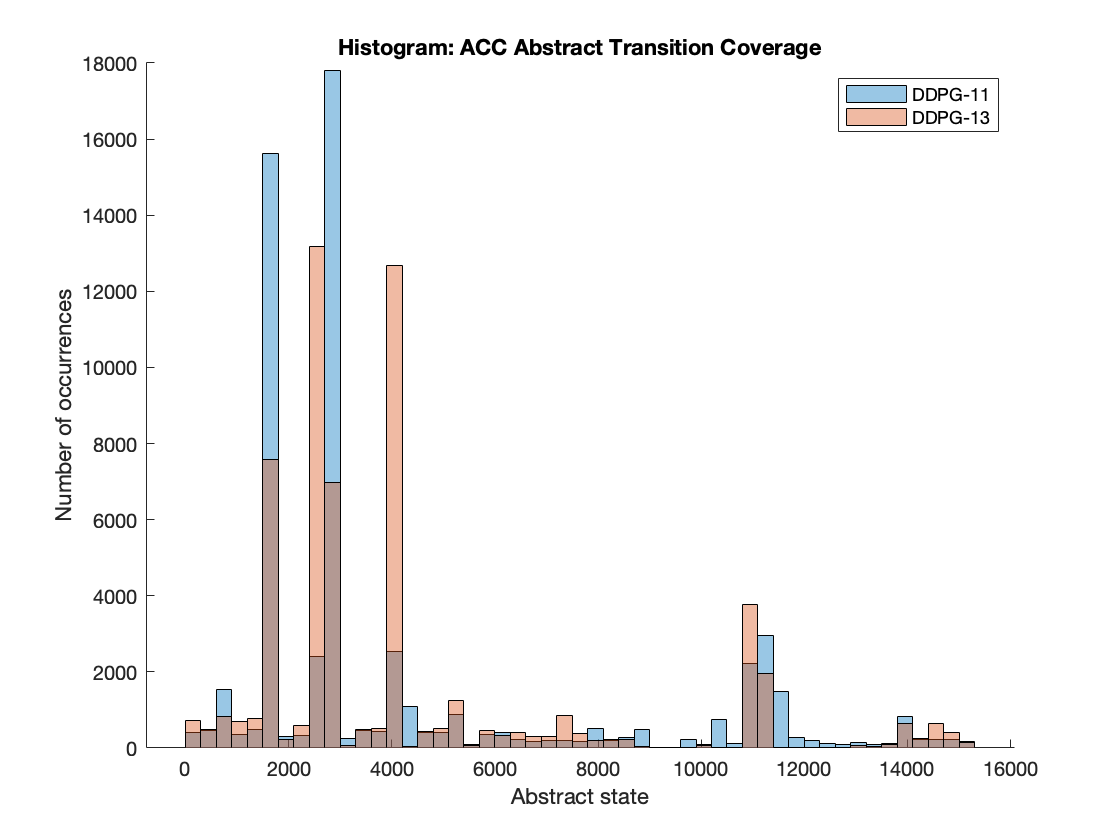

KS test: DDPG-11 and DDPG-13: H1 


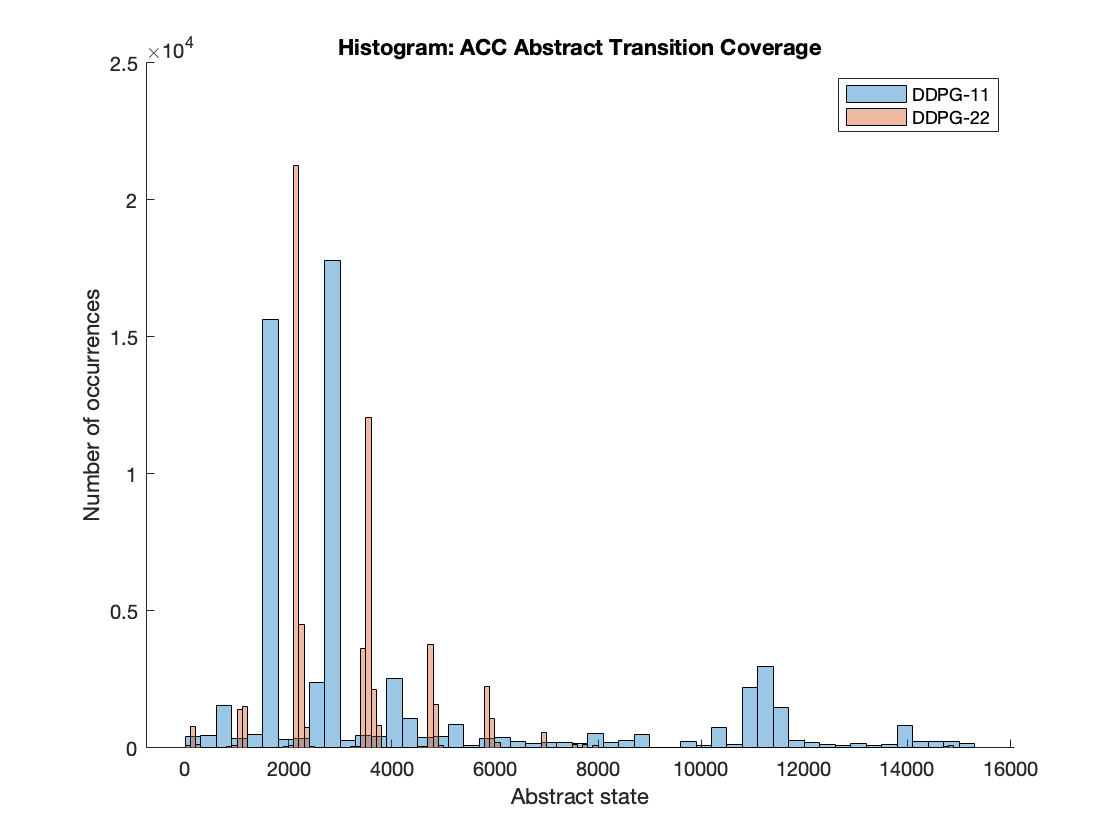

KS test: DDPG-11 and DDPG-22: H1 


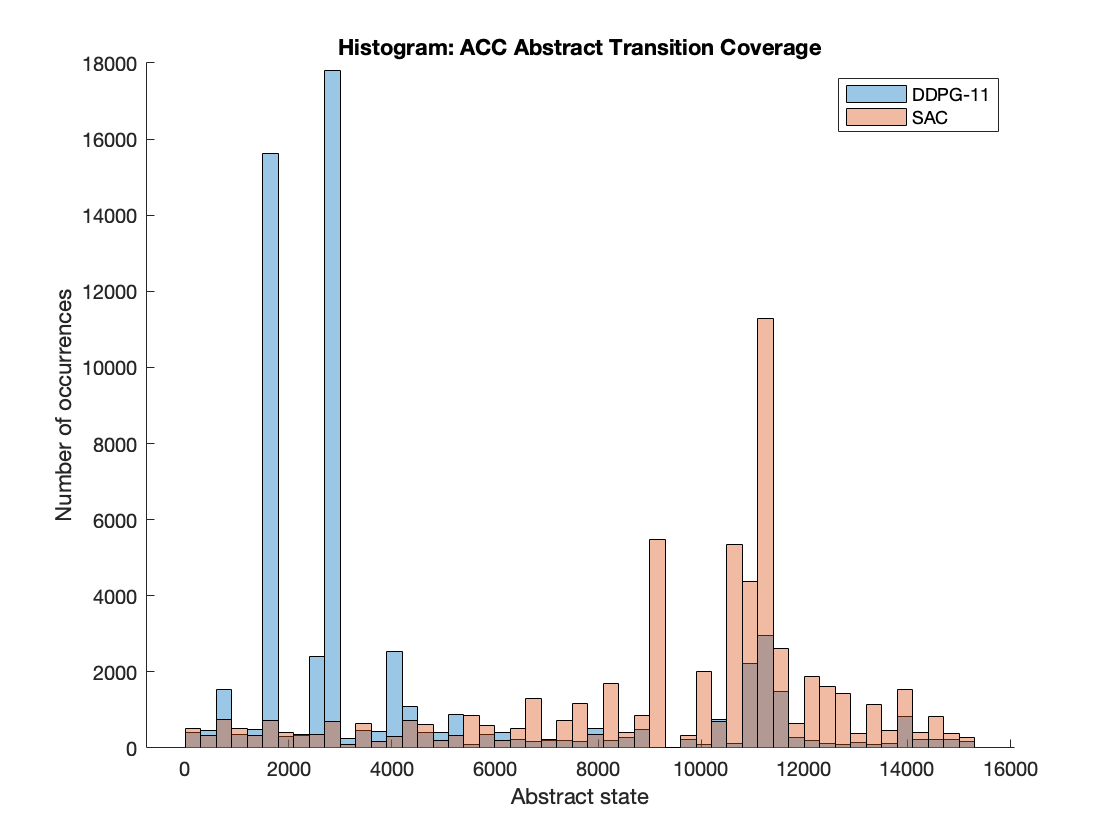

KS test: DDPG-11 and SAC: H1 


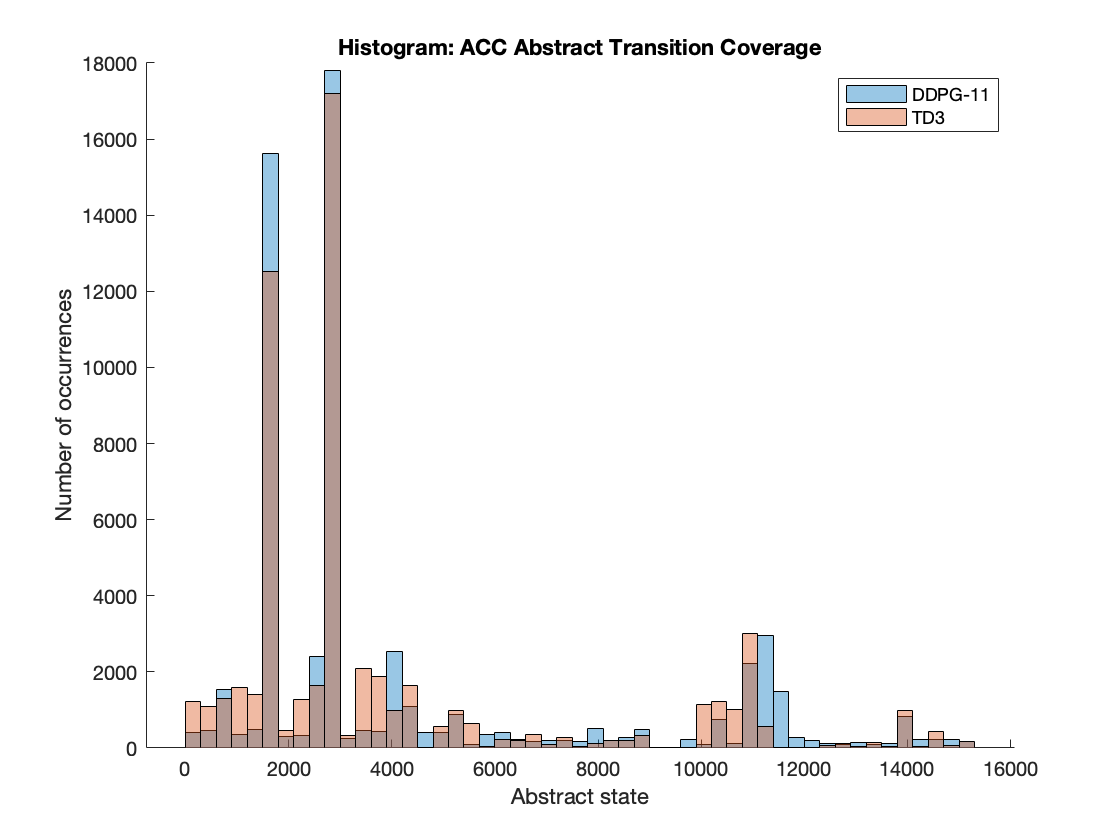

KS test: DDPG-11 and TD3: H1 


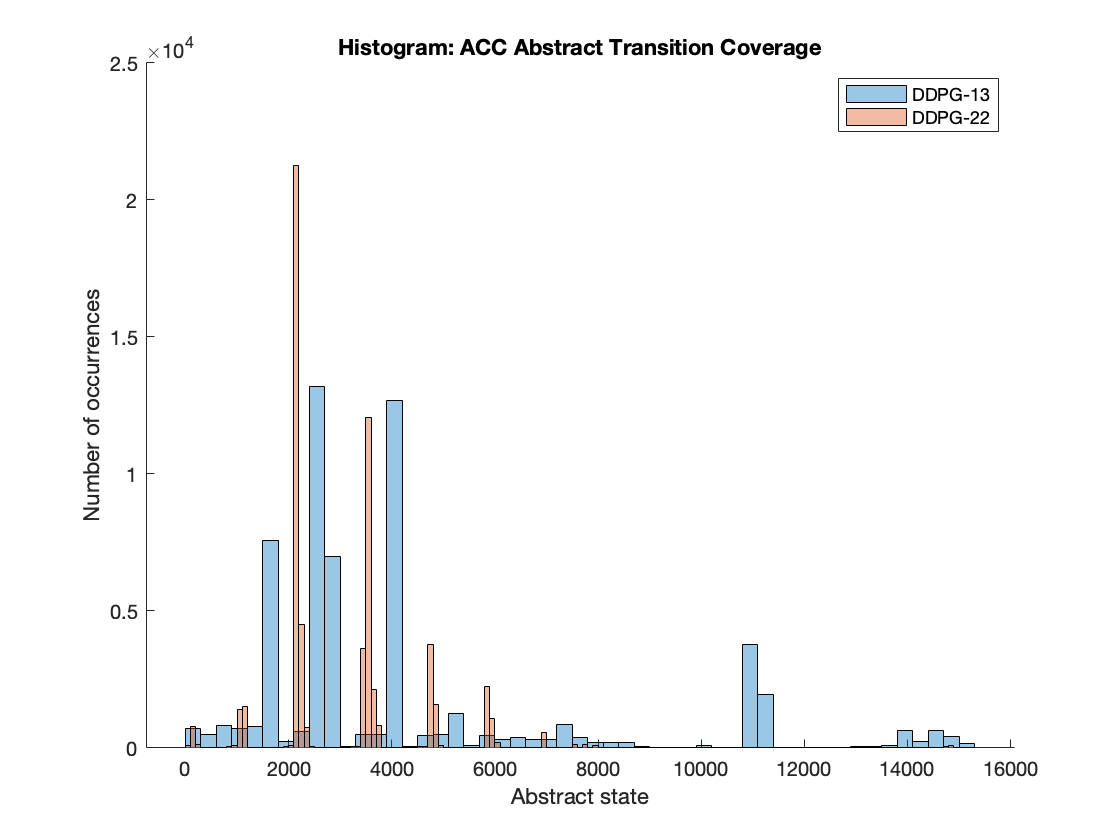

KS test: DDPG-13 and DDPG-22: H1 


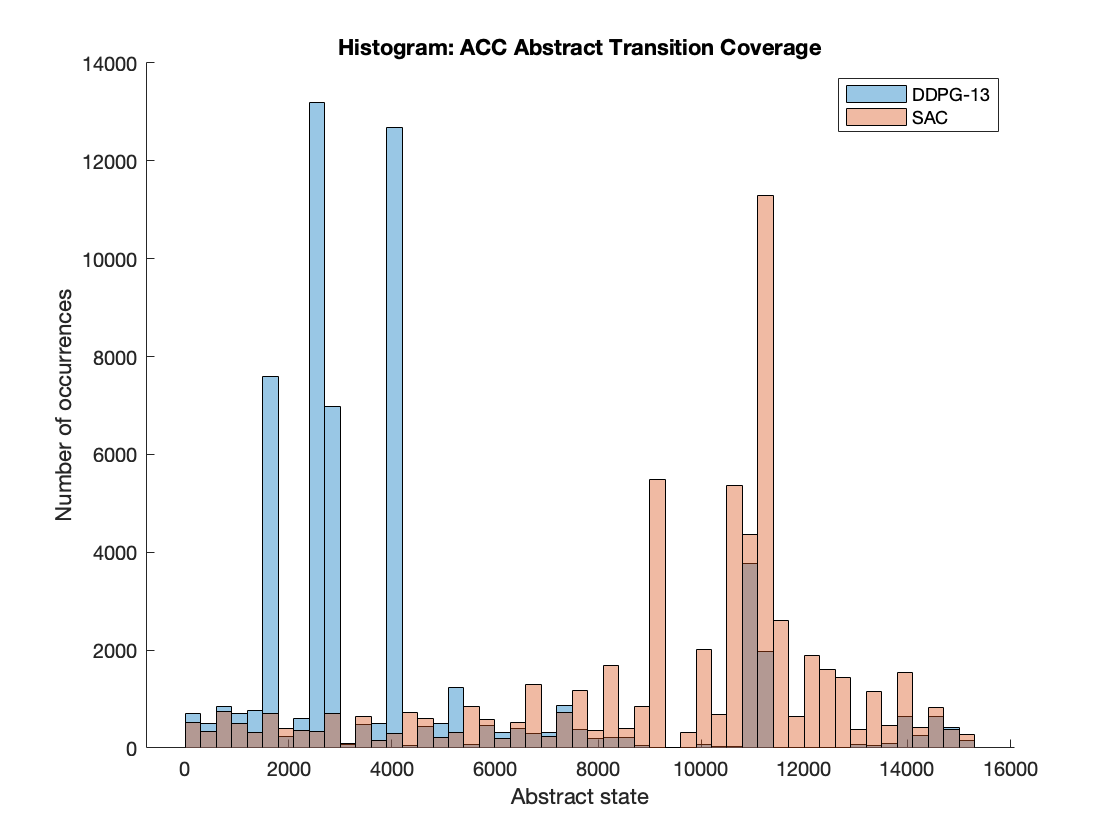

KS test: DDPG-13 and SAC: H1 


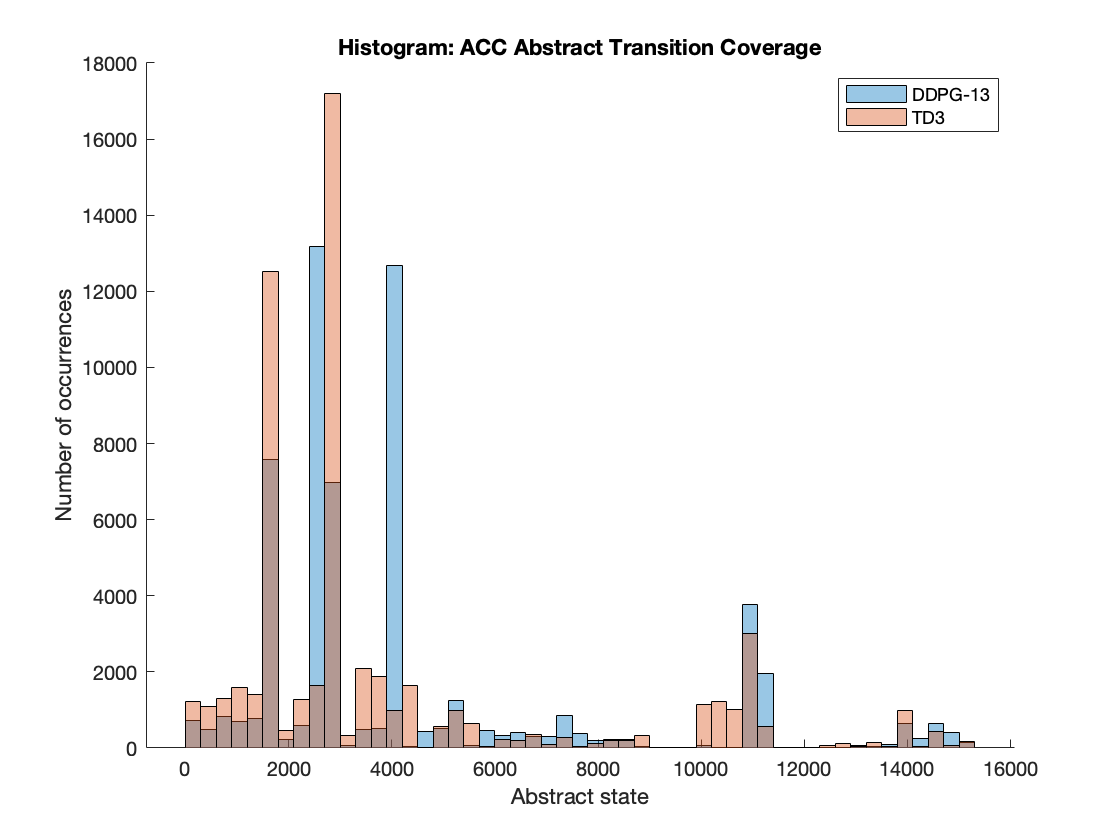

KS test: DDPG-13 and TD3: H1 


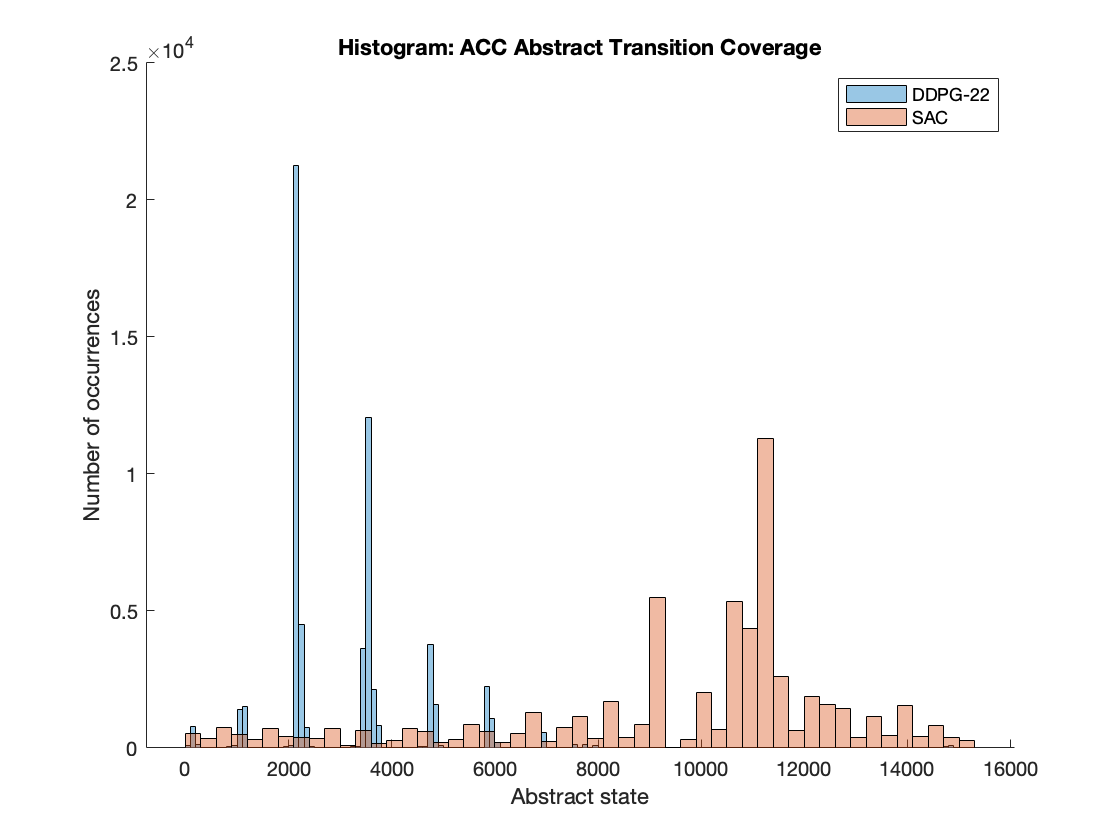

KS test: DDPG-22 and SAC: H1 


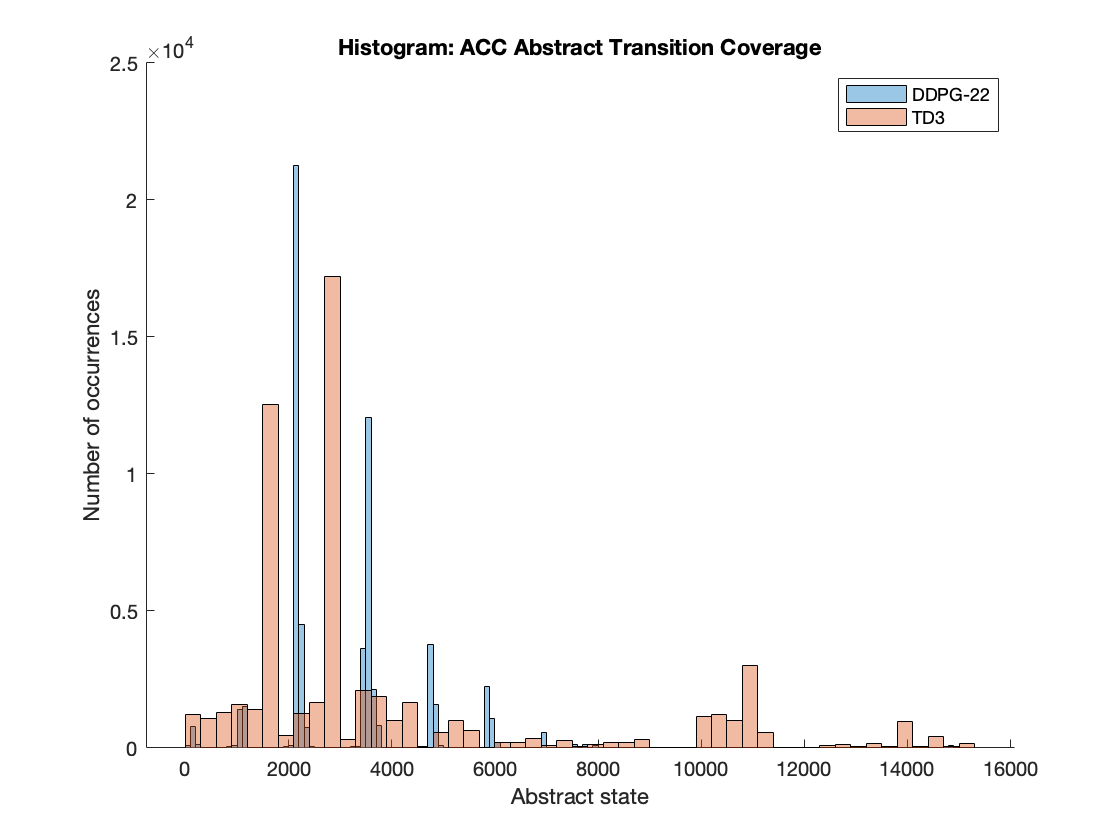

KS test: DDPG-22 and TD3: H1 


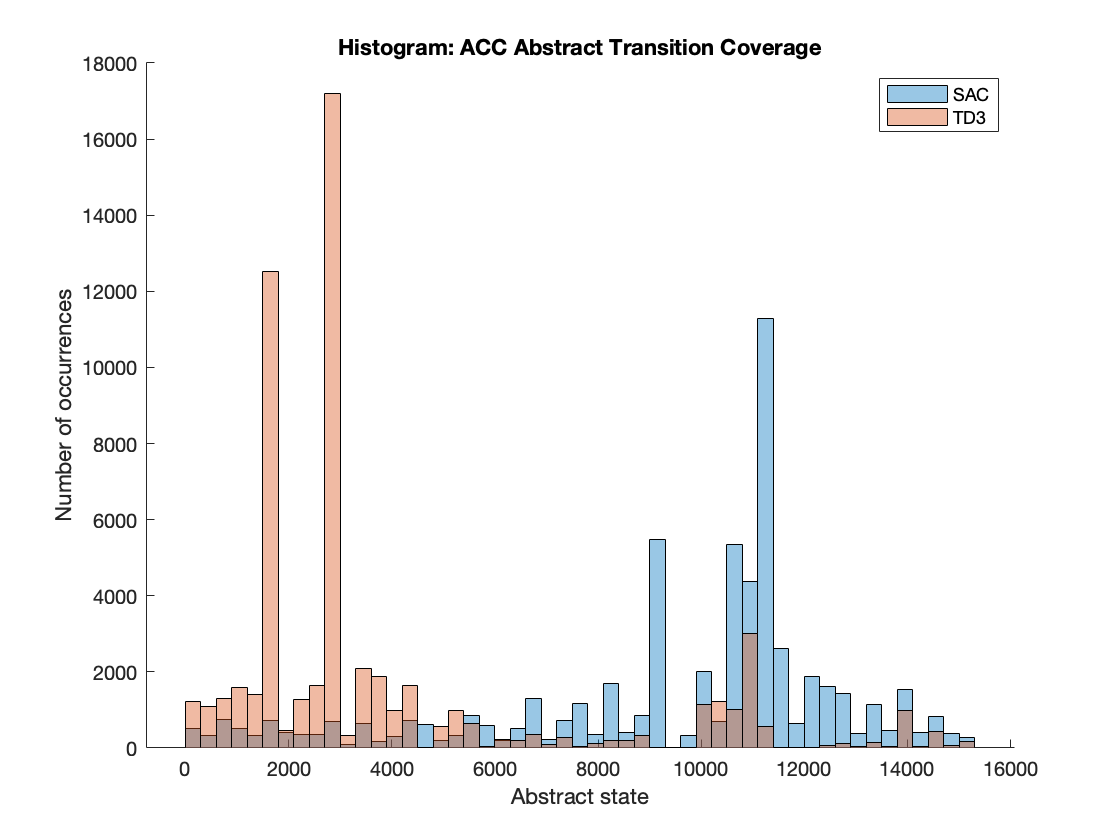

KS test: SAC and TD3: H1 


for i = 1:numController-1
    for j=i+1:numController
        h = kstest2(abTranOfEach{i},abTranOfEach{j});
        if h
            res = "H1";
        else
            res = "H0";
        end
        figure;
        hold on
        histogram(abTranOfEach{i}, 'FaceAlpha',0.4);
        histogram(abTranOfEach{j}, 'FaceAlpha',0.4);
        hold off
        legend(controllerName(i), controllerName(j));
        title("Histogram: ACC Abstract Transition Coverage");
        xlabel('Abstract state') 
        ylabel('Number of occurrences') 

        fprintf("KS test: %s and %s: %s \n",controllerName(i), controllerName(j), res);
    end
end